# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       ex1.mlx                 featureNormalize.m      plotData.m              
..                      ex1_companion.mlx       gradientDescent.m       submit.m                
computeCost.m           ex1data1.txt            gradientDescentMulti.m  warmUpExercise.m        
computeCostMulti.asv    ex1data2.txt            lib                     
computeCostMulti.m      featureNormalize.asv    normalEqn.m             



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

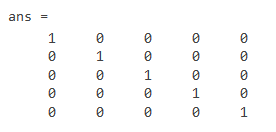

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); 
y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

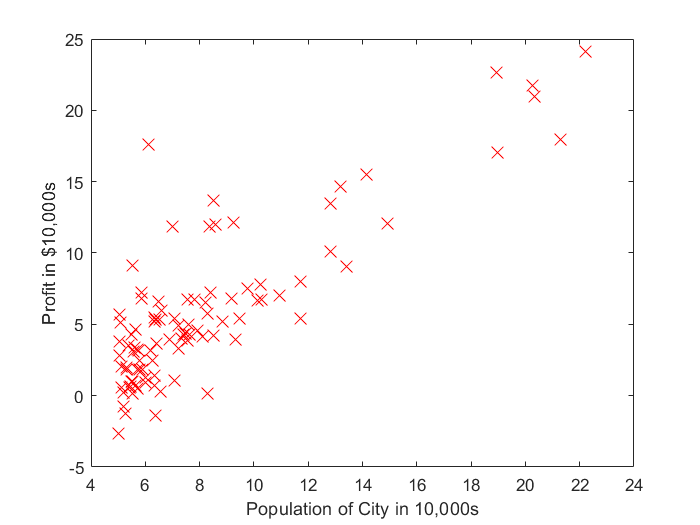

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

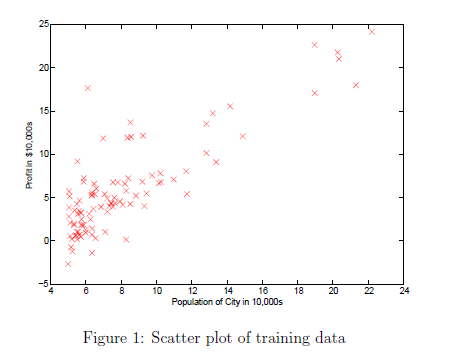

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

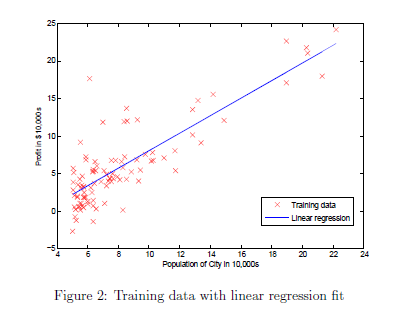    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

prediction =     3.4963
    2.8170
    6.3055
    4.5380
    3.2044
    6.1472
    5.0899
    6.3749
    3.9350
    2.2652


prediction =     3.4961
    2.8168
    6.3054
    4.5378
    3.2042
    6.1471
    5.0898
    6.3748
    3.9348
    2.2650


prediction =     3.4959
    2.8166
    6.3053
    4.5377
    3.2040
    6.1471
    5.0897
    6.3747
    3.9346
    2.2647


prediction =     3.4957
    2.8164
    6.3053
    4.5376
    3.2038
    6.1470
    5.0895
    6.3747
    3.9345
    2.2645


prediction =     3.4956
    2.8162
    6.3052
    4.5374
    3.2036
    6.1469
    5.0894
    6.3746
    3.9343
    2.2643


prediction =     3.4954
    2.8159
    6.3051
    4.5373
    3.2034
    6.1468
    5.0893
    6.3746
    3.9341
    2.2640


prediction =     3.4952
    2.8157
    6.3051
    4.5371
    3.2032
    6.1468
    5.0892
    6.3745
    3.9340
    2.2638


prediction =     3.4950
    2.8155
    6.3050
    4.5370
    3.2030
    6.1467
    5.0891
    6.3744
    3.9338
    2.2636


prediction =     3.4948
    2.8153
    6.3049
    4.5368
    3.2028
    6.1466
    5.0890
    6.3744
    3.9336
    2.2633


prediction =     3.4946
    2.8151
    6.3049
    4.5367
    3.2026
    6.1465
    5.0888
    6.3743
    3.9335
    2.2631


prediction =     3.4945
    2.8149
    6.3048
    4.5366
    3.2024
    6.1465
    5.0887
    6.3742
    3.9333
    2.2629


prediction =     3.4943
    2.8147
    6.3047
    4.5364
    3.2022
    6.1464
    5.0886
    6.3742
    3.9332
    2.2626


prediction =     3.4941
    2.8145
    6.3047
    4.5363
    3.2020
    6.1463
    5.0885
    6.3741
    3.9330
    2.2624


prediction =     3.4939
    2.8143
    6.3046
    4.5362
    3.2018
    6.1462
    5.0884
    6.3740
    3.9328
    2.2622


prediction =     3.4937
    2.8141
    6.3045
    4.5360
    3.2016
    6.1462
    5.0883
    6.3740
    3.9327
    2.2619


prediction =     3.4936
    2.8139
    6.3045
    4.5359
    3.2014
    6.1461
    5.0881
    6.3739
    3.9325
    2.2617


prediction =     3.4934
    2.8137
    6.3044
    4.5357
    3.2013
    6.1460
    5.0880
    6.3738
    3.9323
    2.2615


prediction =     3.4932
    2.8134
    6.3043
    4.5356
    3.2011
    6.1459
    5.0879
    6.3738
    3.9322
    2.2613


prediction =     3.4930
    2.8132
    6.3043
    4.5355
    3.2009
    6.1459
    5.0878
    6.3737
    3.9320
    2.2610


prediction =     3.4928
    2.8130
    6.3042
    4.5353
    3.2007
    6.1458
    5.0877
    6.3736
    3.9319
    2.2608


prediction =     3.4927
    2.8128
    6.3041
    4.5352
    3.2005
    6.1457
    5.0876
    6.3736
    3.9317
    2.2606


prediction =     3.4925
    2.8126
    6.3041
    4.5351
    3.2003
    6.1456
    5.0874
    6.3735
    3.9315
    2.2603


prediction =     3.4923
    2.8124
    6.3040
    4.5349
    3.2001
    6.1456
    5.0873
    6.3735
    3.9314
    2.2601


prediction =     3.4921
    2.8122
    6.3039
    4.5348
    3.1999
    6.1455
    5.0872
    6.3734
    3.9312
    2.2599


prediction =     3.4920
    2.8120
    6.3039
    4.5346
    3.1997
    6.1454
    5.0871
    6.3733
    3.9310
    2.2597


prediction =     3.4918
    2.8118
    6.3038
    4.5345
    3.1995
    6.1454
    5.0870
    6.3733
    3.9309
    2.2594


prediction =     3.4916
    2.8116
    6.3037
    4.5344
    3.1994
    6.1453
    5.0869
    6.3732
    3.9307
    2.2592


prediction =     3.4914
    2.8114
    6.3037
    4.5342
    3.1992
    6.1452
    5.0868
    6.3731
    3.9306
    2.2590


prediction =     3.4912
    2.8112
    6.3036
    4.5341
    3.1990
    6.1451
    5.0866
    6.3731
    3.9304
    2.2588


prediction =     3.4911
    2.8110
    6.3035
    4.5340
    3.1988
    6.1451
    5.0865
    6.3730
    3.9303
    2.2585


prediction =     3.4909
    2.8108
    6.3035
    4.5338
    3.1986
    6.1450
    5.0864
    6.3729
    3.9301
    2.2583


prediction =     3.4907
    2.8106
    6.3034
    4.5337
    3.1984
    6.1449
    5.0863
    6.3729
    3.9299
    2.2581


prediction =     3.4905
    2.8104
    6.3033
    4.5336
    3.1982
    6.1449
    5.0862
    6.3728
    3.9298
    2.2579


prediction =     3.4904
    2.8102
    6.3033
    4.5334
    3.1980
    6.1448
    5.0861
    6.3728
    3.9296
    2.2577


prediction =     3.4902
    2.8100
    6.3032
    4.5333
    3.1979
    6.1447
    5.0860
    6.3727
    3.9295
    2.2574


prediction =     3.4900
    2.8098
    6.3031
    4.5332
    3.1977
    6.1446
    5.0859
    6.3726
    3.9293
    2.2572


prediction =     3.4899
    2.8096
    6.3031
    4.5330
    3.1975
    6.1446
    5.0857
    6.3726
    3.9292
    2.2570


prediction =     3.4897
    2.8094
    6.3030
    4.5329
    3.1973
    6.1445
    5.0856
    6.3725
    3.9290
    2.2568


prediction =     3.4895
    2.8092
    6.3029
    4.5328
    3.1971
    6.1444
    5.0855
    6.3724
    3.9288
    2.2565


prediction =     3.4893
    2.8090
    6.3029
    4.5326
    3.1969
    6.1444
    5.0854
    6.3724
    3.9287
    2.2563


prediction =     3.4892
    2.8088
    6.3028
    4.5325
    3.1968
    6.1443
    5.0853
    6.3723
    3.9285
    2.2561


prediction =     3.4890
    2.8086
    6.3028
    4.5324
    3.1966
    6.1442
    5.0852
    6.3723
    3.9284
    2.2559


prediction =     3.4888
    2.8084
    6.3027
    4.5322
    3.1964
    6.1441
    5.0851
    6.3722
    3.9282
    2.2557


prediction =     3.4886
    2.8082
    6.3026
    4.5321
    3.1962
    6.1441
    5.0850
    6.3721
    3.9281
    2.2554


prediction =     3.4885
    2.8080
    6.3026
    4.5320
    3.1960
    6.1440
    5.0849
    6.3721
    3.9279
    2.2552


prediction =     3.4883
    2.8078
    6.3025
    4.5318
    3.1958
    6.1439
    5.0847
    6.3720
    3.9278
    2.2550


prediction =     3.4881
    2.8076
    6.3024
    4.5317
    3.1957
    6.1439
    5.0846
    6.3720
    3.9276
    2.2548


prediction =     3.4880
    2.8074
    6.3024
    4.5316
    3.1955
    6.1438
    5.0845
    6.3719
    3.9274
    2.2546


prediction =     3.4878
    2.8072
    6.3023
    4.5314
    3.1953
    6.1437
    5.0844
    6.3718
    3.9273
    2.2544


prediction =     3.4876
    2.8070
    6.3022
    4.5313
    3.1951
    6.1437
    5.0843
    6.3718
    3.9271
    2.2541


prediction = 97×1
    3.4875
    2.8068
    6.3022
    4.5312
    3.1949
    6.1436
    5.0842
    6.3717
    3.9270
    2.2539


prediction = 97×1
    3.4873
    2.8066
    6.3021
    4.5311
    3.1948
    6.1435
    5.0841
    6.3717
    3.9268
    2.2537


prediction = 97×1
    3.4871
    2.8064
    6.3021
    4.5309
    3.1946
    6.1435
    5.0840
    6.3716
    3.9267
    2.2535


prediction = 97×1
    3.4869
    2.8062
    6.3020
    4.5308
    3.1944
    6.1434
    5.0839
    6.3715
    3.9265
    2.2533


prediction = 97×1
    3.4868
    2.8061
    6.3019
    4.5307
    3.1942
    6.1433
    5.0838
    6.3715
    3.9264
    2.2531


prediction = 97×1
    3.4866
    2.8059
    6.3019
    4.5305
    3.1940
    6.1432
    5.0837
    6.3714
    3.9262
    2.2529


prediction = 97×1
    3.4864
    2.8057
    6.3018
    4.5304
    3.1939
    6.1432
    5.0835
    6.3714
    3.9261
    2.2526


prediction = 97×1
    3.4863
    2.8055
    6.3017
    4.5303
    3.1937
    6.1431
    5.0834
    6.3713
    3.9259
    2.2524


prediction = 97×1
    3.4861
    2.8053
    6.3017
    4.5302
    3.1935
    6.1430
    5.0833
    6.3712
    3.9258
    2.2522


prediction = 97×1
    3.4859
    2.8051
    6.3016
    4.5300
    3.1933
    6.1430
    5.0832
    6.3712
    3.9256
    2.2520


prediction = 97×1
    3.4858
    2.8049
    6.3016
    4.5299
    3.1932
    6.1429
    5.0831
    6.3711
    3.9255
    2.2518


prediction = 97×1
    3.4856
    2.8047
    6.3015
    4.5298
    3.1930
    6.1428
    5.0830
    6.3711
    3.9253
    2.2516


prediction = 97×1
    3.4854
    2.8045
    6.3014
    4.5296
    3.1928
    6.1428
    5.0829
    6.3710
    3.9252
    2.2514


prediction = 97×1
    3.4853
    2.8043
    6.3014
    4.5295
    3.1926
    6.1427
    5.0828
    6.3709
    3.9250
    2.2512


prediction = 97×1
    3.4851
    2.8041
    6.3013
    4.5294
    3.1924
    6.1426
    5.0827
    6.3709
    3.9249
    2.2510


prediction = 97×1
    3.4850
    2.8039
    6.3012
    4.5293
    3.1923
    6.1426
    5.0826
    6.3708
    3.9247
    2.2507


prediction = 97×1
    3.4848
    2.8038
    6.3012
    4.5291
    3.1921
    6.1425
    5.0825
    6.3708
    3.9246
    2.2505


prediction = 97×1
    3.4846
    2.8036
    6.3011
    4.5290
    3.1919
    6.1424
    5.0824
    6.3707
    3.9244
    2.2503


prediction = 97×1
    3.4845
    2.8034
    6.3011
    4.5289
    3.1918
    6.1424
    5.0823
    6.3706
    3.9243
    2.2501


prediction = 97×1
    3.4843
    2.8032
    6.3010
    4.5288
    3.1916
    6.1423
    5.0822
    6.3706
    3.9241
    2.2499


prediction = 97×1
    3.4841
    2.8030
    6.3009
    4.5286
    3.1914
    6.1422
    5.0821
    6.3705
    3.9240
    2.2497


prediction = 97×1
    3.4840
    2.8028
    6.3009
    4.5285
    3.1912
    6.1422
    5.0820
    6.3705
    3.9238
    2.2495


prediction = 97×1
    3.4838
    2.8026
    6.3008
    4.5284
    3.1911
    6.1421
    5.0818
    6.3704
    3.9237
    2.2493


prediction = 97×1
    3.4836
    2.8024
    6.3008
    4.5283
    3.1909
    6.1420
    5.0817
    6.3704
    3.9236
    2.2491


prediction = 97×1
    3.4835
    2.8023
    6.3007
    4.5281
    3.1907
    6.1420
    5.0816
    6.3703
    3.9234
    2.2489


prediction = 97×1
    3.4833
    2.8021
    6.3006
    4.5280
    3.1905
    6.1419
    5.0815
    6.3702
    3.9233
    2.2487


prediction = 97×1
    3.4832
    2.8019
    6.3006
    4.5279
    3.1904
    6.1418
    5.0814
    6.3702
    3.9231
    2.2485


prediction = 97×1
    3.4830
    2.8017
    6.3005
    4.5278
    3.1902
    6.1418
    5.0813
    6.3701
    3.9230
    2.2483


prediction = 97×1
    3.4828
    2.8015
    6.3005
    4.5276
    3.1900
    6.1417
    5.0812
    6.3701
    3.9228
    2.2480


prediction = 97×1
    3.4827
    2.8013
    6.3004
    4.5275
    3.1899
    6.1416
    5.0811
    6.3700
    3.9227
    2.2478


prediction = 97×1
    3.4825
    2.8011
    6.3003
    4.5274
    3.1897
    6.1416
    5.0810
    6.3699
    3.9225
    2.2476


prediction = 97×1
    3.4824
    2.8010
    6.3003
    4.5273
    3.1895
    6.1415
    5.0809
    6.3699
    3.9224
    2.2474


prediction = 97×1
    3.4822
    2.8008
    6.3002
    4.5272
    3.1893
    6.1414
    5.0808
    6.3698
    3.9222
    2.2472


prediction = 97×1
    3.4820
    2.8006
    6.3002
    4.5270
    3.1892
    6.1414
    5.0807
    6.3698
    3.9221
    2.2470


prediction = 97×1
    3.4819
    2.8004
    6.3001
    4.5269
    3.1890
    6.1413
    5.0806
    6.3697
    3.9220
    2.2468


prediction = 97×1
    3.4817
    2.8002
    6.3000
    4.5268
    3.1888
    6.1412
    5.0805
    6.3697
    3.9218
    2.2466


prediction = 97×1
    3.4816
    2.8000
    6.3000
    4.5267
    3.1887
    6.1412
    5.0804
    6.3696
    3.9217
    2.2464


prediction = 97×1
    3.4814
    2.7999
    6.2999
    4.5265
    3.1885
    6.1411
    5.0803
    6.3696
    3.9215
    2.2462


prediction = 97×1
    3.4812
    2.7997
    6.2999
    4.5264
    3.1883
    6.1411
    5.0802
    6.3695
    3.9214
    2.2460


prediction = 97×1
    3.4811
    2.7995
    6.2998
    4.5263
    3.1882
    6.1410
    5.0801
    6.3694
    3.9212
    2.2458


prediction = 97×1
    3.4809
    2.7993
    6.2997
    4.5262
    3.1880
    6.1409
    5.0800
    6.3694
    3.9211
    2.2456


prediction = 97×1
    3.4808
    2.7991
    6.2997
    4.5261
    3.1878
    6.1409
    5.0799
    6.3693
    3.9210
    2.2454


prediction = 97×1
    3.4806
    2.7990
    6.2996
    4.5259
    3.1877
    6.1408
    5.0798
    6.3693
    3.9208
    2.2452


prediction = 97×1
    3.4805
    2.7988
    6.2996
    4.5258
    3.1875
    6.1407
    5.0797
    6.3692
    3.9207
    2.2450


prediction = 97×1
    3.4803
    2.7986
    6.2995
    4.5257
    3.1873
    6.1407
    5.0796
    6.3692
    3.9205
    2.2448


prediction = 97×1
    3.4801
    2.7984
    6.2995
    4.5256
    3.1872
    6.1406
    5.0795
    6.3691
    3.9204
    2.2446


prediction = 97×1
    3.4800
    2.7982
    6.2994
    4.5255
    3.1870
    6.1405
    5.0794
    6.3690
    3.9203
    2.2444


prediction = 97×1
    3.4798
    2.7981
    6.2993
    4.5253
    3.1868
    6.1405
    5.0793
    6.3690
    3.9201
    2.2442


prediction = 97×1
    3.4797
    2.7979
    6.2993
    4.5252
    3.1867
    6.1404
    5.0792
    6.3689
    3.9200
    2.2440


prediction = 97×1
    3.4795
    2.7977
    6.2992
    4.5251
    3.1865
    6.1404
    5.0791
    6.3689
    3.9198
    2.2438


prediction = 97×1
    3.4794
    2.7975
    6.2992
    4.5250
    3.1863
    6.1403
    5.0790
    6.3688
    3.9197
    2.2436


prediction = 97×1
    3.4792
    2.7973
    6.2991
    4.5249
    3.1862
    6.1402
    5.0789
    6.3688
    3.9196
    2.2434


prediction = 97×1
    3.4791
    2.7972
    6.2990
    4.5247
    3.1860
    6.1402
    5.0788
    6.3687
    3.9194
    2.2432


prediction = 97×1
    3.4789
    2.7970
    6.2990
    4.5246
    3.1858
    6.1401
    5.0787
    6.3687
    3.9193
    2.2430


prediction = 97×1
    3.4788
    2.7968
    6.2989
    4.5245
    3.1857
    6.1400
    5.0786
    6.3686
    3.9191
    2.2428


prediction = 97×1
    3.4786
    2.7966
    6.2989
    4.5244
    3.1855
    6.1400
    5.0785
    6.3685
    3.9190
    2.2427


prediction = 97×1
    3.4785
    2.7965
    6.2988
    4.5243
    3.1853
    6.1399
    5.0784
    6.3685
    3.9189
    2.2425


prediction = 97×1
    3.4783
    2.7963
    6.2988
    4.5242
    3.1852
    6.1399
    5.0783
    6.3684
    3.9187
    2.2423


prediction = 97×1
    3.4781
    2.7961
    6.2987
    4.5240
    3.1850
    6.1398
    5.0782
    6.3684
    3.9186
    2.2421


prediction = 97×1
    3.4780
    2.7959
    6.2986
    4.5239
    3.1849
    6.1397
    5.0781
    6.3683
    3.9185
    2.2419


prediction = 97×1
    3.4778
    2.7958
    6.2986
    4.5238
    3.1847
    6.1397
    5.0780
    6.3683
    3.9183
    2.2417


prediction = 97×1
    3.4777
    2.7956
    6.2985
    4.5237
    3.1845
    6.1396
    5.0779
    6.3682
    3.9182
    2.2415


prediction = 97×1
    3.4775
    2.7954
    6.2985
    4.5236
    3.1844
    6.1395
    5.0778
    6.3682
    3.9180
    2.2413


prediction = 97×1
    3.4774
    2.7952
    6.2984
    4.5235
    3.1842
    6.1395
    5.0777
    6.3681
    3.9179
    2.2411


prediction = 97×1
    3.4772
    2.7951
    6.2984
    4.5233
    3.1841
    6.1394
    5.0776
    6.3681
    3.9178
    2.2409


prediction = 97×1
    3.4771
    2.7949
    6.2983
    4.5232
    3.1839
    6.1394
    5.0775
    6.3680
    3.9176
    2.2407


prediction = 97×1
    3.4769
    2.7947
    6.2983
    4.5231
    3.1837
    6.1393
    5.0774
    6.3680
    3.9175
    2.2405


prediction = 97×1
    3.4768
    2.7945
    6.2982
    4.5230
    3.1836
    6.1392
    5.0773
    6.3679
    3.9174
    2.2403


prediction = 97×1
    3.4766
    2.7944
    6.2981
    4.5229
    3.1834
    6.1392
    5.0772
    6.3678
    3.9172
    2.2401


prediction = 97×1
    3.4765
    2.7942
    6.2981
    4.5228
    3.1833
    6.1391
    5.0771
    6.3678
    3.9171
    2.2400


prediction = 97×1
    3.4763
    2.7940
    6.2980
    4.5227
    3.1831
    6.1390
    5.0770
    6.3677
    3.9170
    2.2398


prediction = 97×1
    3.4762
    2.7939
    6.2980
    4.5225
    3.1829
    6.1390
    5.0769
    6.3677
    3.9168
    2.2396


prediction = 97×1
    3.4760
    2.7937
    6.2979
    4.5224
    3.1828
    6.1389
    5.0768
    6.3676
    3.9167
    2.2394


prediction = 97×1
    3.4759
    2.7935
    6.2979
    4.5223
    3.1826
    6.1389
    5.0767
    6.3676
    3.9166
    2.2392


prediction = 97×1
    3.4757
    2.7933
    6.2978
    4.5222
    3.1825
    6.1388
    5.0767
    6.3675
    3.9164
    2.2390


prediction = 97×1
    3.4756
    2.7932
    6.2978
    4.5221
    3.1823
    6.1387
    5.0766
    6.3675
    3.9163
    2.2388


prediction = 97×1
    3.4755
    2.7930
    6.2977
    4.5220
    3.1822
    6.1387
    5.0765
    6.3674
    3.9162
    2.2386


prediction = 97×1
    3.4753
    2.7928
    6.2976
    4.5219
    3.1820
    6.1386
    5.0764
    6.3674
    3.9160
    2.2384


prediction = 97×1
    3.4752
    2.7927
    6.2976
    4.5217
    3.1818
    6.1386
    5.0763
    6.3673
    3.9159
    2.2383


prediction = 97×1
    3.4750
    2.7925
    6.2975
    4.5216
    3.1817
    6.1385
    5.0762
    6.3673
    3.9158
    2.2381


prediction = 97×1
    3.4749
    2.7923
    6.2975
    4.5215
    3.1815
    6.1384
    5.0761
    6.3672
    3.9156
    2.2379


prediction = 97×1
    3.4747
    2.7922
    6.2974
    4.5214
    3.1814
    6.1384
    5.0760
    6.3672
    3.9155
    2.2377


prediction = 97×1
    3.4746
    2.7920
    6.2974
    4.5213
    3.1812
    6.1383
    5.0759
    6.3671
    3.9154
    2.2375


prediction = 97×1
    3.4744
    2.7918
    6.2973
    4.5212
    3.1811
    6.1383
    5.0758
    6.3671
    3.9152
    2.2373


prediction = 97×1
    3.4743
    2.7917
    6.2973
    4.5211
    3.1809
    6.1382
    5.0757
    6.3670
    3.9151
    2.2371


prediction = 97×1
    3.4741
    2.7915
    6.2972
    4.5210
    3.1808
    6.1381
    5.0756
    6.3669
    3.9150
    2.2370


prediction = 97×1
    3.4740
    2.7913
    6.2972
    4.5209
    3.1806
    6.1381
    5.0755
    6.3669
    3.9148
    2.2368


prediction = 97×1
    3.4738
    2.7912
    6.2971
    4.5207
    3.1804
    6.1380
    5.0754
    6.3668
    3.9147
    2.2366


prediction = 97×1
    3.4737
    2.7910
    6.2970
    4.5206
    3.1803
    6.1380
    5.0753
    6.3668
    3.9146
    2.2364


prediction = 97×1
    3.4736
    2.7908
    6.2970
    4.5205
    3.1801
    6.1379
    5.0752
    6.3667
    3.9145
    2.2362


prediction = 97×1
    3.4734
    2.7907
    6.2969
    4.5204
    3.1800
    6.1379
    5.0751
    6.3667
    3.9143
    2.2360


prediction = 97×1
    3.4733
    2.7905
    6.2969
    4.5203
    3.1798
    6.1378
    5.0751
    6.3666
    3.9142
    2.2359


prediction = 97×1
    3.4731
    2.7903
    6.2968
    4.5202
    3.1797
    6.1377
    5.0750
    6.3666
    3.9141
    2.2357


prediction = 97×1
    3.4730
    2.7902
    6.2968
    4.5201
    3.1795
    6.1377
    5.0749
    6.3665
    3.9139
    2.2355


prediction = 97×1
    3.4728
    2.7900
    6.2967
    4.5200
    3.1794
    6.1376
    5.0748
    6.3665
    3.9138
    2.2353


prediction = 97×1
    3.4727
    2.7898
    6.2967
    4.5199
    3.1792
    6.1376
    5.0747
    6.3664
    3.9137
    2.2351


prediction = 97×1
    3.4726
    2.7897
    6.2966
    4.5198
    3.1791
    6.1375
    5.0746
    6.3664
    3.9135
    2.2349


prediction = 97×1
    3.4724
    2.7895
    6.2966
    4.5196
    3.1789
    6.1374
    5.0745
    6.3663
    3.9134
    2.2348


prediction = 97×1
    3.4723
    2.7893
    6.2965
    4.5195
    3.1788
    6.1374
    5.0744
    6.3663
    3.9133
    2.2346


prediction = 97×1
    3.4721
    2.7892
    6.2965
    4.5194
    3.1786
    6.1373
    5.0743
    6.3662
    3.9132
    2.2344


prediction = 97×1
    3.4720
    2.7890
    6.2964
    4.5193
    3.1785
    6.1373
    5.0742
    6.3662
    3.9130
    2.2342


prediction = 97×1
    3.4718
    2.7889
    6.2964
    4.5192
    3.1783
    6.1372
    5.0741
    6.3661
    3.9129
    2.2340


prediction = 97×1
    3.4717
    2.7887
    6.2963
    4.5191
    3.1782
    6.1372
    5.0740
    6.3661
    3.9128
    2.2339


prediction = 97×1
    3.4716
    2.7885
    6.2962
    4.5190
    3.1780
    6.1371
    5.0740
    6.3660
    3.9127
    2.2337


prediction = 97×1
    3.4714
    2.7884
    6.2962
    4.5189
    3.1779
    6.1370
    5.0739
    6.3660
    3.9125
    2.2335


prediction = 97×1
    3.4713
    2.7882
    6.2961
    4.5188
    3.1777
    6.1370
    5.0738
    6.3659
    3.9124
    2.2333


prediction = 97×1
    3.4711
    2.7880
    6.2961
    4.5187
    3.1776
    6.1369
    5.0737
    6.3659
    3.9123
    2.2331


prediction = 97×1
    3.4710
    2.7879
    6.2960
    4.5186
    3.1774
    6.1369
    5.0736
    6.3658
    3.9122
    2.2330


prediction = 97×1
    3.4709
    2.7877
    6.2960
    4.5185
    3.1773
    6.1368
    5.0735
    6.3658
    3.9120
    2.2328


prediction = 97×1
    3.4707
    2.7876
    6.2959
    4.5183
    3.1771
    6.1368
    5.0734
    6.3657
    3.9119
    2.2326


prediction = 97×1
    3.4706
    2.7874
    6.2959
    4.5182
    3.1770
    6.1367
    5.0733
    6.3657
    3.9118
    2.2324


prediction = 97×1
    3.4705
    2.7872
    6.2958
    4.5181
    3.1768
    6.1366
    5.0732
    6.3656
    3.9117
    2.2323


prediction = 97×1
    3.4703
    2.7871
    6.2958
    4.5180
    3.1767
    6.1366
    5.0732
    6.3656
    3.9115
    2.2321


prediction = 97×1
    3.4702
    2.7869
    6.2957
    4.5179
    3.1765
    6.1365
    5.0731
    6.3655
    3.9114
    2.2319


prediction = 97×1
    3.4700
    2.7868
    6.2957
    4.5178
    3.1764
    6.1365
    5.0730
    6.3655
    3.9113
    2.2317


prediction = 97×1
    3.4699
    2.7866
    6.2956
    4.5177
    3.1762
    6.1364
    5.0729
    6.3654
    3.9112
    2.2316


prediction = 97×1
    3.4698
    2.7865
    6.2956
    4.5176
    3.1761
    6.1364
    5.0728
    6.3654
    3.9110
    2.2314


prediction = 97×1
    3.4696
    2.7863
    6.2955
    4.5175
    3.1760
    6.1363
    5.0727
    6.3653
    3.9109
    2.2312


prediction = 97×1
    3.4695
    2.7861
    6.2955
    4.5174
    3.1758
    6.1362
    5.0726
    6.3653
    3.9108
    2.2310


prediction = 97×1
    3.4694
    2.7860
    6.2954
    4.5173
    3.1757
    6.1362
    5.0725
    6.3652
    3.9107
    2.2309


prediction = 97×1
    3.4692
    2.7858
    6.2954
    4.5172
    3.1755
    6.1361
    5.0724
    6.3652
    3.9105
    2.2307


prediction = 97×1
    3.4691
    2.7857
    6.2953
    4.5171
    3.1754
    6.1361
    5.0724
    6.3651
    3.9104
    2.2305


prediction = 97×1
    3.4689
    2.7855
    6.2953
    4.5170
    3.1752
    6.1360
    5.0723
    6.3651
    3.9103
    2.2303


prediction = 97×1
    3.4688
    2.7854
    6.2952
    4.5169
    3.1751
    6.1360
    5.0722
    6.3650
    3.9102
    2.2302


prediction = 97×1
    3.4687
    2.7852
    6.2952
    4.5168
    3.1749
    6.1359
    5.0721
    6.3650
    3.9100
    2.2300


prediction = 97×1
    3.4685
    2.7850
    6.2951
    4.5167
    3.1748
    6.1359
    5.0720
    6.3649
    3.9099
    2.2298


prediction = 97×1
    3.4684
    2.7849
    6.2951
    4.5166
    3.1746
    6.1358
    5.0719
    6.3649
    3.9098
    2.2297


prediction = 97×1
    3.4683
    2.7847
    6.2950
    4.5165
    3.1745
    6.1358
    5.0718
    6.3648
    3.9097
    2.2295


prediction = 97×1
    3.4681
    2.7846
    6.2950
    4.5164
    3.1744
    6.1357
    5.0717
    6.3648
    3.9096
    2.2293


prediction = 97×1
    3.4680
    2.7844
    6.2949
    4.5163
    3.1742
    6.1356
    5.0717
    6.3648
    3.9094
    2.2291


prediction = 97×1
    3.4679
    2.7843
    6.2949
    4.5162
    3.1741
    6.1356
    5.0716
    6.3647
    3.9093
    2.2290


prediction = 97×1
    3.4677
    2.7841
    6.2948
    4.5160
    3.1739
    6.1355
    5.0715
    6.3647
    3.9092
    2.2288


prediction = 97×1
    3.4676
    2.7840
    6.2948
    4.5159
    3.1738
    6.1355
    5.0714
    6.3646
    3.9091
    2.2286


prediction = 97×1
    3.4675
    2.7838
    6.2947
    4.5158
    3.1737
    6.1354
    5.0713
    6.3646
    3.9090
    2.2285


prediction = 97×1
    3.4673
    2.7837
    6.2947
    4.5157
    3.1735
    6.1354
    5.0712
    6.3645
    3.9088
    2.2283


prediction = 97×1
    3.4672
    2.7835
    6.2946
    4.5156
    3.1734
    6.1353
    5.0711
    6.3645
    3.9087
    2.2281


prediction = 97×1
    3.4671
    2.7834
    6.2946
    4.5155
    3.1732
    6.1353
    5.0711
    6.3644
    3.9086
    2.2280


prediction = 97×1
    3.4669
    2.7832
    6.2945
    4.5154
    3.1731
    6.1352
    5.0710
    6.3644
    3.9085
    2.2278


prediction = 97×1
    3.4668
    2.7830
    6.2945
    4.5153
    3.1729
    6.1352
    5.0709
    6.3643
    3.9084
    2.2276


prediction = 97×1
    3.4667
    2.7829
    6.2944
    4.5152
    3.1728
    6.1351
    5.0708
    6.3643
    3.9082
    2.2274


prediction = 97×1
    3.4665
    2.7827
    6.2944
    4.5151
    3.1727
    6.1350
    5.0707
    6.3642
    3.9081
    2.2273


prediction = 97×1
    3.4664
    2.7826
    6.2943
    4.5150
    3.1725
    6.1350
    5.0706
    6.3642
    3.9080
    2.2271


prediction = 97×1
    3.4663
    2.7824
    6.2943
    4.5149
    3.1724
    6.1349
    5.0706
    6.3641
    3.9079
    2.2269


prediction = 97×1
    3.4662
    2.7823
    6.2942
    4.5148
    3.1722
    6.1349
    5.0705
    6.3641
    3.9078
    2.2268


prediction = 97×1
    3.4660
    2.7821
    6.2942
    4.5147
    3.1721
    6.1348
    5.0704
    6.3640
    3.9077
    2.2266


prediction = 97×1
    3.4659
    2.7820
    6.2941
    4.5146
    3.1720
    6.1348
    5.0703
    6.3640
    3.9075
    2.2264


prediction = 97×1
    3.4658
    2.7818
    6.2941
    4.5145
    3.1718
    6.1347
    5.0702
    6.3639
    3.9074
    2.2263


prediction = 97×1
    3.4656
    2.7817
    6.2940
    4.5144
    3.1717
    6.1347
    5.0701
    6.3639
    3.9073
    2.2261


prediction = 97×1
    3.4655
    2.7815
    6.2940
    4.5143
    3.1716
    6.1346
    5.0700
    6.3639
    3.9072
    2.2259


prediction = 97×1
    3.4654
    2.7814
    6.2939
    4.5142
    3.1714
    6.1346
    5.0700
    6.3638
    3.9071
    2.2258


prediction = 97×1
    3.4652
    2.7812
    6.2939
    4.5141
    3.1713
    6.1345
    5.0699
    6.3638
    3.9070
    2.2256


prediction = 97×1
    3.4651
    2.7811
    6.2938
    4.5140
    3.1711
    6.1345
    5.0698
    6.3637
    3.9068
    2.2255


prediction = 97×1
    3.4650
    2.7810
    6.2938
    4.5139
    3.1710
    6.1344
    5.0697
    6.3637
    3.9067
    2.2253


prediction = 97×1
    3.4649
    2.7808
    6.2937
    4.5138
    3.1709
    6.1344
    5.0696
    6.3636
    3.9066
    2.2251


prediction = 97×1
    3.4647
    2.7807
    6.2937
    4.5137
    3.1707
    6.1343
    5.0696
    6.3636
    3.9065
    2.2250


prediction = 97×1
    3.4646
    2.7805
    6.2936
    4.5136
    3.1706
    6.1343
    5.0695
    6.3635
    3.9064
    2.2248


prediction = 97×1
    3.4645
    2.7804
    6.2936
    4.5135
    3.1705
    6.1342
    5.0694
    6.3635
    3.9063
    2.2246


prediction = 97×1
    3.4643
    2.7802
    6.2936
    4.5134
    3.1703
    6.1341
    5.0693
    6.3634
    3.9061
    2.2245


prediction = 97×1
    3.4642
    2.7801
    6.2935
    4.5134
    3.1702
    6.1341
    5.0692
    6.3634
    3.9060
    2.2243


prediction = 97×1
    3.4641
    2.7799
    6.2935
    4.5133
    3.1701
    6.1340
    5.0691
    6.3634
    3.9059
    2.2242


prediction = 97×1
    3.4640
    2.7798
    6.2934
    4.5132
    3.1699
    6.1340
    5.0691
    6.3633
    3.9058
    2.2240


prediction = 97×1
    3.4638
    2.7796
    6.2934
    4.5131
    3.1698
    6.1339
    5.0690
    6.3633
    3.9057
    2.2238


prediction = 97×1
    3.4637
    2.7795
    6.2933
    4.5130
    3.1696
    6.1339
    5.0689
    6.3632
    3.9056
    2.2237


prediction = 97×1
    3.4636
    2.7793
    6.2933
    4.5129
    3.1695
    6.1338
    5.0688
    6.3632
    3.9055
    2.2235


prediction = 97×1
    3.4635
    2.7792
    6.2932
    4.5128
    3.1694
    6.1338
    5.0687
    6.3631
    3.9053
    2.2233


prediction = 97×1
    3.4633
    2.7791
    6.2932
    4.5127
    3.1692
    6.1337
    5.0687
    6.3631
    3.9052
    2.2232


prediction = 97×1
    3.4632
    2.7789
    6.2931
    4.5126
    3.1691
    6.1337
    5.0686
    6.3630
    3.9051
    2.2230


prediction = 97×1
    3.4631
    2.7788
    6.2931
    4.5125
    3.1690
    6.1336
    5.0685
    6.3630
    3.9050
    2.2229


prediction = 97×1
    3.4630
    2.7786
    6.2930
    4.5124
    3.1688
    6.1336
    5.0684
    6.3629
    3.9049
    2.2227


prediction = 97×1
    3.4628
    2.7785
    6.2930
    4.5123
    3.1687
    6.1335
    5.0683
    6.3629
    3.9048
    2.2226


prediction = 97×1
    3.4627
    2.7783
    6.2929
    4.5122
    3.1686
    6.1335
    5.0682
    6.3629
    3.9047
    2.2224


prediction = 97×1
    3.4626
    2.7782
    6.2929
    4.5121
    3.1685
    6.1334
    5.0682
    6.3628
    3.9046
    2.2222


prediction = 97×1
    3.4625
    2.7780
    6.2928
    4.5120
    3.1683
    6.1334
    5.0681
    6.3628
    3.9044
    2.2221


prediction = 97×1
    3.4623
    2.7779
    6.2928
    4.5119
    3.1682
    6.1333
    5.0680
    6.3627
    3.9043
    2.2219


prediction = 97×1
    3.4622
    2.7778
    6.2928
    4.5118
    3.1681
    6.1333
    5.0679
    6.3627
    3.9042
    2.2218


prediction = 97×1
    3.4621
    2.7776
    6.2927
    4.5117
    3.1679
    6.1332
    5.0679
    6.3626
    3.9041
    2.2216


prediction = 97×1
    3.4620
    2.7775
    6.2927
    4.5116
    3.1678
    6.1332
    5.0678
    6.3626
    3.9040
    2.2214


prediction = 97×1
    3.4618
    2.7773
    6.2926
    4.5115
    3.1677
    6.1331
    5.0677
    6.3625
    3.9039
    2.2213


prediction = 97×1
    3.4617
    2.7772
    6.2926
    4.5114
    3.1675
    6.1331
    5.0676
    6.3625
    3.9038
    2.2211


prediction = 97×1
    3.4616
    2.7771
    6.2925
    4.5113
    3.1674
    6.1330
    5.0675
    6.3625
    3.9037
    2.2210


prediction = 97×1
    3.4615
    2.7769
    6.2925
    4.5112
    3.1673
    6.1330
    5.0675
    6.3624
    3.9036
    2.2208


prediction = 97×1
    3.4614
    2.7768
    6.2924
    4.5112
    3.1671
    6.1329
    5.0674
    6.3624
    3.9034
    2.2207


prediction = 97×1
    3.4612
    2.7766
    6.2924
    4.5111
    3.1670
    6.1329
    5.0673
    6.3623
    3.9033
    2.2205


prediction = 97×1
    3.4611
    2.7765
    6.2923
    4.5110
    3.1669
    6.1328
    5.0672
    6.3623
    3.9032
    2.2204


prediction = 97×1
    3.4610
    2.7764
    6.2923
    4.5109
    3.1668
    6.1328
    5.0671
    6.3622
    3.9031
    2.2202


prediction = 97×1
    3.4609
    2.7762
    6.2923
    4.5108
    3.1666
    6.1327
    5.0671
    6.3622
    3.9030
    2.2200


prediction = 97×1
    3.4607
    2.7761
    6.2922
    4.5107
    3.1665
    6.1327
    5.0670
    6.3622
    3.9029
    2.2199


prediction = 97×1
    3.4606
    2.7759
    6.2922
    4.5106
    3.1664
    6.1326
    5.0669
    6.3621
    3.9028
    2.2197


prediction = 97×1
    3.4605
    2.7758
    6.2921
    4.5105
    3.1662
    6.1326
    5.0668
    6.3621
    3.9027
    2.2196


prediction = 97×1
    3.4604
    2.7757
    6.2921
    4.5104
    3.1661
    6.1325
    5.0668
    6.3620
    3.9026
    2.2194


prediction = 97×1
    3.4603
    2.7755
    6.2920
    4.5103
    3.1660
    6.1325
    5.0667
    6.3620
    3.9025
    2.2193


prediction = 97×1
    3.4601
    2.7754
    6.2920
    4.5102
    3.1659
    6.1324
    5.0666
    6.3619
    3.9024
    2.2191


prediction = 97×1
    3.4600
    2.7752
    6.2919
    4.5101
    3.1657
    6.1324
    5.0665
    6.3619
    3.9022
    2.2190


prediction = 97×1
    3.4599
    2.7751
    6.2919
    4.5100
    3.1656
    6.1323
    5.0664
    6.3619
    3.9021
    2.2188


prediction = 97×1
    3.4598
    2.7750
    6.2918
    4.5099
    3.1655
    6.1323
    5.0664
    6.3618
    3.9020
    2.2187


prediction = 97×1
    3.4597
    2.7748
    6.2918
    4.5099
    3.1653
    6.1322
    5.0663
    6.3618
    3.9019
    2.2185


prediction = 97×1
    3.4596
    2.7747
    6.2918
    4.5098
    3.1652
    6.1322
    5.0662
    6.3617
    3.9018
    2.2184


prediction = 97×1
    3.4594
    2.7746
    6.2917
    4.5097
    3.1651
    6.1321
    5.0661
    6.3617
    3.9017
    2.2182


prediction = 97×1
    3.4593
    2.7744
    6.2917
    4.5096
    3.1650
    6.1321
    5.0661
    6.3616
    3.9016
    2.2181


prediction = 97×1
    3.4592
    2.7743
    6.2916
    4.5095
    3.1648
    6.1320
    5.0660
    6.3616
    3.9015
    2.2179


prediction = 97×1
    3.4591
    2.7741
    6.2916
    4.5094
    3.1647
    6.1320
    5.0659
    6.3616
    3.9014
    2.2178


prediction = 97×1
    3.4590
    2.7740
    6.2915
    4.5093
    3.1646
    6.1319
    5.0658
    6.3615
    3.9013
    2.2176


prediction = 97×1
    3.4588
    2.7739
    6.2915
    4.5092
    3.1645
    6.1319
    5.0658
    6.3615
    3.9012
    2.2175


prediction = 97×1
    3.4587
    2.7737
    6.2915
    4.5091
    3.1643
    6.1318
    5.0657
    6.3614
    3.9011
    2.2173


prediction = 97×1
    3.4586
    2.7736
    6.2914
    4.5090
    3.1642
    6.1318
    5.0656
    6.3614
    3.9010
    2.2172


prediction = 97×1
    3.4585
    2.7735
    6.2914
    4.5090
    3.1641
    6.1318
    5.0655
    6.3613
    3.9009
    2.2170


prediction = 97×1
    3.4584
    2.7733
    6.2913
    4.5089
    3.1640
    6.1317
    5.0655
    6.3613
    3.9008
    2.2169


prediction = 97×1
    3.4583
    2.7732
    6.2913
    4.5088
    3.1638
    6.1317
    5.0654
    6.3613
    3.9006
    2.2167


prediction = 97×1
    3.4581
    2.7731
    6.2912
    4.5087
    3.1637
    6.1316
    5.0653
    6.3612
    3.9005
    2.2166


prediction = 97×1
    3.4580
    2.7729
    6.2912
    4.5086
    3.1636
    6.1316
    5.0652
    6.3612
    3.9004
    2.2164


prediction = 97×1
    3.4579
    2.7728
    6.2911
    4.5085
    3.1635
    6.1315
    5.0652
    6.3611
    3.9003
    2.2163


prediction = 97×1
    3.4578
    2.7727
    6.2911
    4.5084
    3.1633
    6.1315
    5.0651
    6.3611
    3.9002
    2.2161


prediction = 97×1
    3.4577
    2.7725
    6.2911
    4.5083
    3.1632
    6.1314
    5.0650
    6.3611
    3.9001
    2.2160


prediction = 97×1
    3.4576
    2.7724
    6.2910
    4.5082
    3.1631
    6.1314
    5.0649
    6.3610
    3.9000
    2.2158


prediction = 97×1
    3.4574
    2.7723
    6.2910
    4.5082
    3.1630
    6.1313
    5.0649
    6.3610
    3.8999
    2.2157


prediction = 97×1
    3.4573
    2.7721
    6.2909
    4.5081
    3.1629
    6.1313
    5.0648
    6.3609
    3.8998
    2.2155


prediction = 97×1
    3.4572
    2.7720
    6.2909
    4.5080
    3.1627
    6.1312
    5.0647
    6.3609
    3.8997
    2.2154


prediction = 97×1
    3.4571
    2.7719
    6.2908
    4.5079
    3.1626
    6.1312
    5.0646
    6.3609
    3.8996
    2.2152


prediction = 97×1
    3.4570
    2.7717
    6.2908
    4.5078
    3.1625
    6.1311
    5.0646
    6.3608
    3.8995
    2.2151


prediction = 97×1
    3.4569
    2.7716
    6.2908
    4.5077
    3.1624
    6.1311
    5.0645
    6.3608
    3.8994
    2.2150


prediction = 97×1
    3.4568
    2.7715
    6.2907
    4.5076
    3.1622
    6.1310
    5.0644
    6.3607
    3.8993
    2.2148


prediction = 97×1
    3.4566
    2.7714
    6.2907
    4.5075
    3.1621
    6.1310
    5.0643
    6.3607
    3.8992
    2.2147


prediction = 97×1
    3.4565
    2.7712
    6.2906
    4.5075
    3.1620
    6.1310
    5.0643
    6.3606
    3.8991
    2.2145


prediction = 97×1
    3.4564
    2.7711
    6.2906
    4.5074
    3.1619
    6.1309
    5.0642
    6.3606
    3.8990
    2.2144


prediction = 97×1
    3.4563
    2.7710
    6.2905
    4.5073
    3.1618
    6.1309
    5.0641
    6.3606
    3.8989
    2.2142


prediction = 97×1
    3.4562
    2.7708
    6.2905
    4.5072
    3.1616
    6.1308
    5.0641
    6.3605
    3.8988
    2.2141


prediction = 97×1
    3.4561
    2.7707
    6.2905
    4.5071
    3.1615
    6.1308
    5.0640
    6.3605
    3.8987
    2.2139


prediction = 97×1
    3.4560
    2.7706
    6.2904
    4.5070
    3.1614
    6.1307
    5.0639
    6.3604
    3.8986
    2.2138


prediction = 97×1
    3.4559
    2.7704
    6.2904
    4.5069
    3.1613
    6.1307
    5.0638
    6.3604
    3.8985
    2.2137


prediction = 97×1
    3.4557
    2.7703
    6.2903
    4.5068
    3.1612
    6.1306
    5.0638
    6.3604
    3.8984
    2.2135


prediction = 97×1
    3.4556
    2.7702
    6.2903
    4.5068
    3.1610
    6.1306
    5.0637
    6.3603
    3.8983
    2.2134


prediction = 97×1
    3.4555
    2.7701
    6.2903
    4.5067
    3.1609
    6.1305
    5.0636
    6.3603
    3.8982
    2.2132


prediction = 97×1
    3.4554
    2.7699
    6.2902
    4.5066
    3.1608
    6.1305
    5.0635
    6.3602
    3.8981
    2.2131


prediction = 97×1
    3.4553
    2.7698
    6.2902
    4.5065
    3.1607
    6.1305
    5.0635
    6.3602
    3.8980
    2.2130


prediction = 97×1
    3.4552
    2.7697
    6.2901
    4.5064
    3.1606
    6.1304
    5.0634
    6.3602
    3.8979
    2.2128


prediction = 97×1
    3.4551
    2.7695
    6.2901
    4.5063
    3.1605
    6.1304
    5.0633
    6.3601
    3.8978
    2.2127


prediction = 97×1
    3.4550
    2.7694
    6.2900
    4.5063
    3.1603
    6.1303
    5.0633
    6.3601
    3.8977
    2.2125


prediction = 97×1
    3.4549
    2.7693
    6.2900
    4.5062
    3.1602
    6.1303
    5.0632
    6.3600
    3.8976
    2.2124


prediction = 97×1
    3.4548
    2.7692
    6.2900
    4.5061
    3.1601
    6.1302
    5.0631
    6.3600
    3.8975
    2.2122


prediction = 97×1
    3.4546
    2.7690
    6.2899
    4.5060
    3.1600
    6.1302
    5.0630
    6.3600
    3.8974
    2.2121


prediction = 97×1
    3.4545
    2.7689
    6.2899
    4.5059
    3.1599
    6.1301
    5.0630
    6.3599
    3.8973
    2.2120


prediction = 97×1
    3.4544
    2.7688
    6.2898
    4.5058
    3.1598
    6.1301
    5.0629
    6.3599
    3.8972
    2.2118


prediction = 97×1
    3.4543
    2.7687
    6.2898
    4.5057
    3.1596
    6.1300
    5.0628
    6.3599
    3.8971
    2.2117


prediction = 97×1
    3.4542
    2.7685
    6.2898
    4.5057
    3.1595
    6.1300
    5.0628
    6.3598
    3.8970
    2.2115


prediction = 97×1
    3.4541
    2.7684
    6.2897
    4.5056
    3.1594
    6.1300
    5.0627
    6.3598
    3.8969
    2.2114


prediction = 97×1
    3.4540
    2.7683
    6.2897
    4.5055
    3.1593
    6.1299
    5.0626
    6.3597
    3.8968
    2.2113


prediction = 97×1
    3.4539
    2.7682
    6.2896
    4.5054
    3.1592
    6.1299
    5.0626
    6.3597
    3.8967
    2.2111


prediction = 97×1
    3.4538
    2.7680
    6.2896
    4.5053
    3.1591
    6.1298
    5.0625
    6.3597
    3.8966
    2.2110


prediction = 97×1
    3.4537
    2.7679
    6.2896
    4.5052
    3.1589
    6.1298
    5.0624
    6.3596
    3.8965
    2.2109


prediction = 97×1
    3.4536
    2.7678
    6.2895
    4.5052
    3.1588
    6.1297
    5.0623
    6.3596
    3.8964
    2.2107


prediction = 97×1
    3.4534
    2.7677
    6.2895
    4.5051
    3.1587
    6.1297
    5.0623
    6.3595
    3.8963
    2.2106


prediction = 97×1
    3.4533
    2.7675
    6.2894
    4.5050
    3.1586
    6.1296
    5.0622
    6.3595
    3.8962
    2.2104


prediction = 97×1
    3.4532
    2.7674
    6.2894
    4.5049
    3.1585
    6.1296
    5.0621
    6.3595
    3.8961
    2.2103


prediction = 97×1
    3.4531
    2.7673
    6.2894
    4.5048
    3.1584
    6.1296
    5.0621
    6.3594
    3.8960
    2.2102


prediction = 97×1
    3.4530
    2.7672
    6.2893
    4.5048
    3.1583
    6.1295
    5.0620
    6.3594
    3.8959
    2.2100


prediction = 97×1
    3.4529
    2.7670
    6.2893
    4.5047
    3.1581
    6.1295
    5.0619
    6.3593
    3.8958
    2.2099


prediction = 97×1
    3.4528
    2.7669
    6.2892
    4.5046
    3.1580
    6.1294
    5.0619
    6.3593
    3.8957
    2.2098


prediction = 97×1
    3.4527
    2.7668
    6.2892
    4.5045
    3.1579
    6.1294
    5.0618
    6.3593
    3.8956
    2.2096


prediction = 97×1
    3.4526
    2.7667
    6.2892
    4.5044
    3.1578
    6.1293
    5.0617
    6.3592
    3.8955
    2.2095


prediction = 97×1
    3.4525
    2.7666
    6.2891
    4.5043
    3.1577
    6.1293
    5.0617
    6.3592
    3.8954
    2.2094


prediction = 97×1
    3.4524
    2.7664
    6.2891
    4.5043
    3.1576
    6.1293
    5.0616
    6.3592
    3.8953
    2.2092


prediction = 97×1
    3.4523
    2.7663
    6.2890
    4.5042
    3.1575
    6.1292
    5.0615
    6.3591
    3.8952
    2.2091


prediction = 97×1
    3.4522
    2.7662
    6.2890
    4.5041
    3.1574
    6.1292
    5.0615
    6.3591
    3.8952
    2.2090


prediction = 97×1
    3.4521
    2.7661
    6.2890
    4.5040
    3.1572
    6.1291
    5.0614
    6.3590
    3.8951
    2.2088


prediction = 97×1
    3.4520
    2.7659
    6.2889
    4.5039
    3.1571
    6.1291
    5.0613
    6.3590
    3.8950
    2.2087


prediction = 97×1
    3.4519
    2.7658
    6.2889
    4.5039
    3.1570
    6.1290
    5.0613
    6.3590
    3.8949
    2.2086


prediction = 97×1
    3.4517
    2.7657
    6.2888
    4.5038
    3.1569
    6.1290
    5.0612
    6.3589
    3.8948
    2.2084


prediction = 97×1
    3.4516
    2.7656
    6.2888
    4.5037
    3.1568
    6.1290
    5.0611
    6.3589
    3.8947
    2.2083


prediction = 97×1
    3.4515
    2.7655
    6.2888
    4.5036
    3.1567
    6.1289
    5.0610
    6.3589
    3.8946
    2.2082


prediction = 97×1
    3.4514
    2.7653
    6.2887
    4.5035
    3.1566
    6.1289
    5.0610
    6.3588
    3.8945
    2.2080


prediction = 97×1
    3.4513
    2.7652
    6.2887
    4.5035
    3.1565
    6.1288
    5.0609
    6.3588
    3.8944
    2.2079


prediction = 97×1
    3.4512
    2.7651
    6.2887
    4.5034
    3.1564
    6.1288
    5.0608
    6.3587
    3.8943
    2.2078


prediction = 97×1
    3.4511
    2.7650
    6.2886
    4.5033
    3.1562
    6.1287
    5.0608
    6.3587
    3.8942
    2.2076


prediction = 97×1
    3.4510
    2.7649
    6.2886
    4.5032
    3.1561
    6.1287
    5.0607
    6.3587
    3.8941
    2.2075


prediction = 97×1
    3.4509
    2.7648
    6.2885
    4.5031
    3.1560
    6.1287
    5.0606
    6.3586
    3.8940
    2.2074


prediction = 97×1
    3.4508
    2.7646
    6.2885
    4.5031
    3.1559
    6.1286
    5.0606
    6.3586
    3.8939
    2.2072


prediction = 97×1
    3.4507
    2.7645
    6.2885
    4.5030
    3.1558
    6.1286
    5.0605
    6.3586
    3.8938
    2.2071


prediction = 97×1
    3.4506
    2.7644
    6.2884
    4.5029
    3.1557
    6.1285
    5.0604
    6.3585
    3.8937
    2.2070


prediction = 97×1
    3.4505
    2.7643
    6.2884
    4.5028
    3.1556
    6.1285
    5.0604
    6.3585
    3.8937
    2.2068


prediction = 97×1
    3.4504
    2.7642
    6.2883
    4.5027
    3.1555
    6.1284
    5.0603
    6.3585
    3.8936
    2.2067


prediction = 97×1
    3.4503
    2.7640
    6.2883
    4.5027
    3.1554
    6.1284
    5.0603
    6.3584
    3.8935
    2.2066


prediction = 97×1
    3.4502
    2.7639
    6.2883
    4.5026
    3.1553
    6.1284
    5.0602
    6.3584
    3.8934
    2.2064


prediction = 97×1
    3.4501
    2.7638
    6.2882
    4.5025
    3.1551
    6.1283
    5.0601
    6.3583
    3.8933
    2.2063


prediction = 97×1
    3.4500
    2.7637
    6.2882
    4.5024
    3.1550
    6.1283
    5.0601
    6.3583
    3.8932
    2.2062


prediction = 97×1
    3.4499
    2.7636
    6.2882
    4.5024
    3.1549
    6.1282
    5.0600
    6.3583
    3.8931
    2.2061


prediction = 97×1
    3.4498
    2.7635
    6.2881
    4.5023
    3.1548
    6.1282
    5.0599
    6.3582
    3.8930
    2.2059


prediction = 97×1
    3.4497
    2.7633
    6.2881
    4.5022
    3.1547
    6.1282
    5.0599
    6.3582
    3.8929
    2.2058


prediction = 97×1
    3.4496
    2.7632
    6.2880
    4.5021
    3.1546
    6.1281
    5.0598
    6.3582
    3.8928
    2.2057


prediction = 97×1
    3.4495
    2.7631
    6.2880
    4.5020
    3.1545
    6.1281
    5.0597
    6.3581
    3.8927
    2.2055


prediction = 97×1
    3.4494
    2.7630
    6.2880
    4.5020
    3.1544
    6.1280
    5.0597
    6.3581
    3.8926
    2.2054


prediction = 97×1
    3.4493
    2.7629
    6.2879
    4.5019
    3.1543
    6.1280
    5.0596
    6.3581
    3.8926
    2.2053


prediction = 97×1
    3.4492
    2.7628
    6.2879
    4.5018
    3.1542
    6.1280
    5.0595
    6.3580
    3.8925
    2.2052


prediction = 97×1
    3.4491
    2.7626
    6.2879
    4.5017
    3.1541
    6.1279
    5.0595
    6.3580
    3.8924
    2.2050


prediction = 97×1
    3.4490
    2.7625
    6.2878
    4.5017
    3.1540
    6.1279
    5.0594
    6.3579
    3.8923
    2.2049


prediction = 97×1
    3.4489
    2.7624
    6.2878
    4.5016
    3.1539
    6.1278
    5.0593
    6.3579
    3.8922
    2.2048


prediction = 97×1
    3.4488
    2.7623
    6.2877
    4.5015
    3.1538
    6.1278
    5.0593
    6.3579
    3.8921
    2.2047


prediction = 97×1
    3.4487
    2.7622
    6.2877
    4.5014
    3.1537
    6.1277
    5.0592
    6.3578
    3.8920
    2.2045


prediction = 97×1
    3.4486
    2.7621
    6.2877
    4.5014
    3.1535
    6.1277
    5.0592
    6.3578
    3.8919
    2.2044


prediction = 97×1
    3.4485
    2.7620
    6.2876
    4.5013
    3.1534
    6.1277
    5.0591
    6.3578
    3.8918
    2.2043


prediction = 97×1
    3.4484
    2.7618
    6.2876
    4.5012
    3.1533
    6.1276
    5.0590
    6.3577
    3.8918
    2.2041


prediction = 97×1
    3.4483
    2.7617
    6.2876
    4.5011
    3.1532
    6.1276
    5.0590
    6.3577
    3.8917
    2.2040


prediction = 97×1
    3.4482
    2.7616
    6.2875
    4.5011
    3.1531
    6.1275
    5.0589
    6.3577
    3.8916
    2.2039


prediction = 97×1
    3.4481
    2.7615
    6.2875
    4.5010
    3.1530
    6.1275
    5.0588
    6.3576
    3.8915
    2.2038


prediction = 97×1
    3.4480
    2.7614
    6.2874
    4.5009
    3.1529
    6.1275
    5.0588
    6.3576
    3.8914
    2.2036


prediction = 97×1
    3.4479
    2.7613
    6.2874
    4.5008
    3.1528
    6.1274
    5.0587
    6.3576
    3.8913
    2.2035


prediction = 97×1
    3.4478
    2.7612
    6.2874
    4.5008
    3.1527
    6.1274
    5.0586
    6.3575
    3.8912
    2.2034


prediction = 97×1
    3.4477
    2.7611
    6.2873
    4.5007
    3.1526
    6.1273
    5.0586
    6.3575
    3.8911
    2.2033


prediction = 97×1
    3.4476
    2.7609
    6.2873
    4.5006
    3.1525
    6.1273
    5.0585
    6.3575
    3.8910
    2.2031


prediction = 97×1
    3.4475
    2.7608
    6.2873
    4.5005
    3.1524
    6.1273
    5.0585
    6.3574
    3.8910
    2.2030


prediction = 97×1
    3.4474
    2.7607
    6.2872
    4.5005
    3.1523
    6.1272
    5.0584
    6.3574
    3.8909
    2.2029


prediction = 97×1
    3.4473
    2.7606
    6.2872
    4.5004
    3.1522
    6.1272
    5.0583
    6.3573
    3.8908
    2.2028


prediction = 97×1
    3.4472
    2.7605
    6.2872
    4.5003
    3.1521
    6.1271
    5.0583
    6.3573
    3.8907
    2.2027


prediction = 97×1
    3.4471
    2.7604
    6.2871
    4.5002
    3.1520
    6.1271
    5.0582
    6.3573
    3.8906
    2.2025


prediction = 97×1
    3.4470
    2.7603
    6.2871
    4.5002
    3.1519
    6.1271
    5.0581
    6.3572
    3.8905
    2.2024


prediction = 97×1
    3.4469
    2.7602
    6.2870
    4.5001
    3.1518
    6.1270
    5.0581
    6.3572
    3.8904
    2.2023


prediction = 97×1
    3.4468
    2.7601
    6.2870
    4.5000
    3.1517
    6.1270
    5.0580
    6.3572
    3.8903
    2.2022


prediction = 97×1
    3.4467
    2.7599
    6.2870
    4.4999
    3.1516
    6.1270
    5.0580
    6.3571
    3.8903
    2.2020


prediction = 97×1
    3.4467
    2.7598
    6.2869
    4.4999
    3.1515
    6.1269
    5.0579
    6.3571
    3.8902
    2.2019


prediction = 97×1
    3.4466
    2.7597
    6.2869
    4.4998
    3.1514
    6.1269
    5.0578
    6.3571
    3.8901
    2.2018


prediction = 97×1
    3.4465
    2.7596
    6.2869
    4.4997
    3.1513
    6.1268
    5.0578
    6.3570
    3.8900
    2.2017


prediction = 97×1
    3.4464
    2.7595
    6.2868
    4.4996
    3.1512
    6.1268
    5.0577
    6.3570
    3.8899
    2.2016


prediction = 97×1
    3.4463
    2.7594
    6.2868
    4.4996
    3.1511
    6.1268
    5.0577
    6.3570
    3.8898
    2.2014


prediction = 97×1
    3.4462
    2.7593
    6.2868
    4.4995
    3.1510
    6.1267
    5.0576
    6.3569
    3.8897
    2.2013


prediction = 97×1
    3.4461
    2.7592
    6.2867
    4.4994
    3.1509
    6.1267
    5.0575
    6.3569
    3.8897
    2.2012


prediction = 97×1
    3.4460
    2.7591
    6.2867
    4.4994
    3.1508
    6.1266
    5.0575
    6.3569
    3.8896
    2.2011


prediction = 97×1
    3.4459
    2.7590
    6.2867
    4.4993
    3.1507
    6.1266
    5.0574
    6.3568
    3.8895
    2.2010


prediction = 97×1
    3.4458
    2.7589
    6.2866
    4.4992
    3.1506
    6.1266
    5.0573
    6.3568
    3.8894
    2.2008


prediction = 97×1
    3.4457
    2.7588
    6.2866
    4.4991
    3.1505
    6.1265
    5.0573
    6.3568
    3.8893
    2.2007


prediction = 97×1
    3.4456
    2.7586
    6.2866
    4.4991
    3.1504
    6.1265
    5.0572
    6.3567
    3.8892
    2.2006


prediction = 97×1
    3.4455
    2.7585
    6.2865
    4.4990
    3.1503
    6.1265
    5.0572
    6.3567
    3.8892
    2.2005


prediction = 97×1
    3.4454
    2.7584
    6.2865
    4.4989
    3.1502
    6.1264
    5.0571
    6.3567
    3.8891
    2.2004


prediction = 97×1
    3.4453
    2.7583
    6.2864
    4.4989
    3.1501
    6.1264
    5.0570
    6.3566
    3.8890
    2.2002


prediction = 97×1
    3.4452
    2.7582
    6.2864
    4.4988
    3.1500
    6.1263
    5.0570
    6.3566
    3.8889
    2.2001


prediction = 97×1
    3.4451
    2.7581
    6.2864
    4.4987
    3.1499
    6.1263
    5.0569
    6.3566
    3.8888
    2.2000


prediction = 97×1
    3.4451
    2.7580
    6.2863
    4.4986
    3.1498
    6.1263
    5.0569
    6.3565
    3.8887
    2.1999


prediction = 97×1
    3.4450
    2.7579
    6.2863
    4.4986
    3.1497
    6.1262
    5.0568
    6.3565
    3.8887
    2.1998


prediction = 97×1
    3.4449
    2.7578
    6.2863
    4.4985
    3.1496
    6.1262
    5.0567
    6.3565
    3.8886
    2.1997


prediction = 97×1
    3.4448
    2.7577
    6.2862
    4.4984
    3.1495
    6.1261
    5.0567
    6.3564
    3.8885
    2.1995


prediction = 97×1
    3.4447
    2.7576
    6.2862
    4.4984
    3.1494
    6.1261
    5.0566
    6.3564
    3.8884
    2.1994


prediction = 97×1
    3.4446
    2.7575
    6.2862
    4.4983
    3.1493
    6.1261
    5.0566
    6.3564
    3.8883
    2.1993


prediction = 97×1
    3.4445
    2.7574
    6.2861
    4.4982
    3.1492
    6.1260
    5.0565
    6.3563
    3.8882
    2.1992


prediction = 97×1
    3.4444
    2.7573
    6.2861
    4.4981
    3.1491
    6.1260
    5.0565
    6.3563
    3.8882
    2.1991


prediction = 97×1
    3.4443
    2.7572
    6.2861
    4.4981
    3.1490
    6.1260
    5.0564
    6.3563
    3.8881
    2.1990


prediction = 97×1
    3.4442
    2.7570
    6.2860
    4.4980
    3.1489
    6.1259
    5.0563
    6.3562
    3.8880
    2.1988


prediction = 97×1
    3.4441
    2.7569
    6.2860
    4.4979
    3.1488
    6.1259
    5.0563
    6.3562
    3.8879
    2.1987


prediction = 97×1
    3.4440
    2.7568
    6.2860
    4.4979
    3.1487
    6.1258
    5.0562
    6.3562
    3.8878
    2.1986


prediction = 97×1
    3.4440
    2.7567
    6.2859
    4.4978
    3.1486
    6.1258
    5.0562
    6.3561
    3.8877
    2.1985


prediction = 97×1
    3.4439
    2.7566
    6.2859
    4.4977
    3.1485
    6.1258
    5.0561
    6.3561
    3.8877
    2.1984


prediction = 97×1
    3.4438
    2.7565
    6.2859
    4.4977
    3.1484
    6.1257
    5.0560
    6.3561
    3.8876
    2.1983


prediction = 97×1
    3.4437
    2.7564
    6.2858
    4.4976
    3.1483
    6.1257
    5.0560
    6.3560
    3.8875
    2.1981


prediction = 97×1
    3.4436
    2.7563
    6.2858
    4.4975
    3.1482
    6.1257
    5.0559
    6.3560
    3.8874
    2.1980


prediction = 97×1
    3.4435
    2.7562
    6.2858
    4.4974
    3.1481
    6.1256
    5.0559
    6.3560
    3.8873
    2.1979


prediction = 97×1
    3.4434
    2.7561
    6.2857
    4.4974
    3.1480
    6.1256
    5.0558
    6.3560
    3.8873
    2.1978


prediction = 97×1
    3.4433
    2.7560
    6.2857
    4.4973
    3.1479
    6.1256
    5.0558
    6.3559
    3.8872
    2.1977


prediction = 97×1
    3.4432
    2.7559
    6.2857
    4.4972
    3.1478
    6.1255
    5.0557
    6.3559
    3.8871
    2.1976


prediction = 97×1
    3.4431
    2.7558
    6.2856
    4.4972
    3.1477
    6.1255
    5.0556
    6.3559
    3.8870
    2.1975


prediction = 97×1
    3.4431
    2.7557
    6.2856
    4.4971
    3.1477
    6.1254
    5.0556
    6.3558
    3.8869
    2.1973


prediction = 97×1
    3.4430
    2.7556
    6.2856
    4.4970
    3.1476
    6.1254
    5.0555
    6.3558
    3.8869
    2.1972


prediction = 97×1
    3.4429
    2.7555
    6.2855
    4.4970
    3.1475
    6.1254
    5.0555
    6.3558
    3.8868
    2.1971


prediction = 97×1
    3.4428
    2.7554
    6.2855
    4.4969
    3.1474
    6.1253
    5.0554
    6.3557
    3.8867
    2.1970


prediction = 97×1
    3.4427
    2.7553
    6.2855
    4.4968
    3.1473
    6.1253
    5.0554
    6.3557
    3.8866
    2.1969


prediction = 97×1
    3.4426
    2.7552
    6.2854
    4.4968
    3.1472
    6.1253
    5.0553
    6.3557
    3.8865
    2.1968


prediction = 97×1
    3.4425
    2.7551
    6.2854
    4.4967
    3.1471
    6.1252
    5.0552
    6.3556
    3.8865
    2.1967


prediction = 97×1
    3.4424
    2.7550
    6.2854
    4.4966
    3.1470
    6.1252
    5.0552
    6.3556
    3.8864
    2.1966


prediction = 97×1
    3.4424
    2.7549
    6.2853
    4.4966
    3.1469
    6.1252
    5.0551
    6.3556
    3.8863
    2.1964


prediction = 97×1
    3.4423
    2.7548
    6.2853
    4.4965
    3.1468
    6.1251
    5.0551
    6.3555
    3.8862
    2.1963


prediction = 97×1
    3.4422
    2.7547
    6.2853
    4.4964
    3.1467
    6.1251
    5.0550
    6.3555
    3.8861
    2.1962


prediction = 97×1
    3.4421
    2.7546
    6.2852
    4.4964
    3.1466
    6.1250
    5.0550
    6.3555
    3.8861
    2.1961


prediction = 97×1
    3.4420
    2.7545
    6.2852
    4.4963
    3.1465
    6.1250
    5.0549
    6.3554
    3.8860
    2.1960


prediction = 97×1
    3.4419
    2.7544
    6.2852
    4.4962
    3.1464
    6.1250
    5.0548
    6.3554
    3.8859
    2.1959


prediction = 97×1
    3.4418
    2.7543
    6.2851
    4.4962
    3.1463
    6.1249
    5.0548
    6.3554
    3.8858
    2.1958


prediction = 97×1
    3.4417
    2.7542
    6.2851
    4.4961
    3.1462
    6.1249
    5.0547
    6.3554
    3.8857
    2.1957


prediction = 97×1
    3.4417
    2.7541
    6.2851
    4.4960
    3.1462
    6.1249
    5.0547
    6.3553
    3.8857
    2.1956


prediction = 97×1
    3.4416
    2.7540
    6.2850
    4.4960
    3.1461
    6.1248
    5.0546
    6.3553
    3.8856
    2.1954


prediction = 97×1
    3.4415
    2.7539
    6.2850
    4.4959
    3.1460
    6.1248
    5.0546
    6.3553
    3.8855
    2.1953


prediction = 97×1
    3.4414
    2.7538
    6.2850
    4.4958
    3.1459
    6.1248
    5.0545
    6.3552
    3.8854
    2.1952


prediction = 97×1
    3.4413
    2.7537
    6.2849
    4.4958
    3.1458
    6.1247
    5.0545
    6.3552
    3.8854
    2.1951


prediction = 97×1
    3.4412
    2.7536
    6.2849
    4.4957
    3.1457
    6.1247
    5.0544
    6.3552
    3.8853
    2.1950


prediction = 97×1
    3.4411
    2.7535
    6.2849
    4.4956
    3.1456
    6.1247
    5.0543
    6.3551
    3.8852
    2.1949


prediction = 97×1
    3.4411
    2.7534
    6.2849
    4.4956
    3.1455
    6.1246
    5.0543
    6.3551
    3.8851
    2.1948


prediction = 97×1
    3.4410
    2.7533
    6.2848
    4.4955
    3.1454
    6.1246
    5.0542
    6.3551
    3.8851
    2.1947


prediction = 97×1
    3.4409
    2.7532
    6.2848
    4.4954
    3.1453
    6.1246
    5.0542
    6.3550
    3.8850
    2.1946


prediction = 97×1
    3.4408
    2.7531
    6.2848
    4.4954
    3.1452
    6.1245
    5.0541
    6.3550
    3.8849
    2.1945


prediction = 97×1
    3.4407
    2.7530
    6.2847
    4.4953
    3.1452
    6.1245
    5.0541
    6.3550
    3.8848
    2.1944


prediction = 97×1
    3.4406
    2.7529
    6.2847
    4.4952
    3.1451
    6.1245
    5.0540
    6.3550
    3.8847
    2.1942


prediction = 97×1
    3.4405
    2.7528
    6.2847
    4.4952
    3.1450
    6.1244
    5.0540
    6.3549
    3.8847
    2.1941


prediction = 97×1
    3.4405
    2.7527
    6.2846
    4.4951
    3.1449
    6.1244
    5.0539
    6.3549
    3.8846
    2.1940


prediction = 97×1
    3.4404
    2.7526
    6.2846
    4.4950
    3.1448
    6.1243
    5.0539
    6.3549
    3.8845
    2.1939


prediction = 97×1
    3.4403
    2.7525
    6.2846
    4.4950
    3.1447
    6.1243
    5.0538
    6.3548
    3.8844
    2.1938


prediction = 97×1
    3.4402
    2.7524
    6.2845
    4.4949
    3.1446
    6.1243
    5.0537
    6.3548
    3.8844
    2.1937


prediction = 97×1
    3.4401
    2.7523
    6.2845
    4.4949
    3.1445
    6.1242
    5.0537
    6.3548
    3.8843
    2.1936


prediction = 97×1
    3.4400
    2.7522
    6.2845
    4.4948
    3.1444
    6.1242
    5.0536
    6.3547
    3.8842
    2.1935


prediction = 97×1
    3.4400
    2.7521
    6.2844
    4.4947
    3.1443
    6.1242
    5.0536
    6.3547
    3.8841
    2.1934


prediction = 97×1
    3.4399
    2.7520
    6.2844
    4.4947
    3.1443
    6.1241
    5.0535
    6.3547
    3.8841
    2.1933


prediction = 97×1
    3.4398
    2.7519
    6.2844
    4.4946
    3.1442
    6.1241
    5.0535
    6.3547
    3.8840
    2.1932


prediction = 97×1
    3.4397
    2.7518
    6.2843
    4.4945
    3.1441
    6.1241
    5.0534
    6.3546
    3.8839
    2.1931


prediction = 97×1
    3.4396
    2.7518
    6.2843
    4.4945
    3.1440
    6.1240
    5.0534
    6.3546
    3.8838
    2.1930


prediction = 97×1
    3.4395
    2.7517
    6.2843
    4.4944
    3.1439
    6.1240
    5.0533
    6.3546
    3.8838
    2.1929


prediction = 97×1
    3.4395
    2.7516
    6.2843
    4.4943
    3.1438
    6.1240
    5.0533
    6.3545
    3.8837
    2.1928


prediction = 97×1
    3.4394
    2.7515
    6.2842
    4.4943
    3.1437
    6.1239
    5.0532
    6.3545
    3.8836
    2.1927


prediction = 97×1
    3.4393
    2.7514
    6.2842
    4.4942
    3.1436
    6.1239
    5.0532
    6.3545
    3.8835
    2.1925


prediction = 97×1
    3.4392
    2.7513
    6.2842
    4.4942
    3.1436
    6.1239
    5.0531
    6.3544
    3.8835
    2.1924


prediction = 97×1
    3.4391
    2.7512
    6.2841
    4.4941
    3.1435
    6.1238
    5.0531
    6.3544
    3.8834
    2.1923


prediction = 97×1
    3.4391
    2.7511
    6.2841
    4.4940
    3.1434
    6.1238
    5.0530
    6.3544
    3.8833
    2.1922


prediction = 97×1
    3.4390
    2.7510
    6.2841
    4.4940
    3.1433
    6.1238
    5.0529
    6.3544
    3.8832
    2.1921


prediction = 97×1
    3.4389
    2.7509
    6.2840
    4.4939
    3.1432
    6.1237
    5.0529
    6.3543
    3.8832
    2.1920


prediction = 97×1
    3.4388
    2.7508
    6.2840
    4.4938
    3.1431
    6.1237
    5.0528
    6.3543
    3.8831
    2.1919


prediction = 97×1
    3.4387
    2.7507
    6.2840
    4.4938
    3.1430
    6.1237
    5.0528
    6.3543
    3.8830
    2.1918


prediction = 97×1
    3.4386
    2.7506
    6.2840
    4.4937
    3.1429
    6.1236
    5.0527
    6.3542
    3.8830
    2.1917


prediction = 97×1
    3.4386
    2.7505
    6.2839
    4.4937
    3.1429
    6.1236
    5.0527
    6.3542
    3.8829
    2.1916


prediction = 97×1
    3.4385
    2.7504
    6.2839
    4.4936
    3.1428
    6.1236
    5.0526
    6.3542
    3.8828
    2.1915


prediction = 97×1
    3.4384
    2.7503
    6.2839
    4.4935
    3.1427
    6.1235
    5.0526
    6.3542
    3.8827
    2.1914


prediction = 97×1
    3.4383
    2.7502
    6.2838
    4.4935
    3.1426
    6.1235
    5.0525
    6.3541
    3.8827
    2.1913


prediction = 97×1
    3.4382
    2.7502
    6.2838
    4.4934
    3.1425
    6.1235
    5.0525
    6.3541
    3.8826
    2.1912


prediction = 97×1
    3.4382
    2.7501
    6.2838
    4.4933
    3.1424
    6.1234
    5.0524
    6.3541
    3.8825
    2.1911


prediction = 97×1
    3.4381
    2.7500
    6.2837
    4.4933
    3.1423
    6.1234
    5.0524
    6.3540
    3.8824
    2.1910


prediction = 97×1
    3.4380
    2.7499
    6.2837
    4.4932
    3.1423
    6.1234
    5.0523
    6.3540
    3.8824
    2.1909


prediction = 97×1
    3.4379
    2.7498
    6.2837
    4.4932
    3.1422
    6.1233
    5.0523
    6.3540
    3.8823
    2.1908


prediction = 97×1
    3.4378
    2.7497
    6.2837
    4.4931
    3.1421
    6.1233
    5.0522
    6.3540
    3.8822
    2.1907


prediction = 97×1
    3.4378
    2.7496
    6.2836
    4.4930
    3.1420
    6.1233
    5.0522
    6.3539
    3.8822
    2.1906


prediction = 97×1
    3.4377
    2.7495
    6.2836
    4.4930
    3.1419
    6.1232
    5.0521
    6.3539
    3.8821
    2.1905


prediction = 97×1
    3.4376
    2.7494
    6.2836
    4.4929
    3.1418
    6.1232
    5.0521
    6.3539
    3.8820
    2.1904


prediction = 97×1
    3.4375
    2.7493
    6.2835
    4.4929
    3.1418
    6.1232
    5.0520
    6.3538
    3.8819
    2.1903


prediction = 97×1
    3.4374
    2.7492
    6.2835
    4.4928
    3.1417
    6.1232
    5.0520
    6.3538
    3.8819
    2.1902


prediction = 97×1
    3.4374
    2.7491
    6.2835
    4.4927
    3.1416
    6.1231
    5.0519
    6.3538
    3.8818
    2.1901


prediction = 97×1
    3.4373
    2.7491
    6.2834
    4.4927
    3.1415
    6.1231
    5.0519
    6.3538
    3.8817
    2.1900


prediction = 97×1
    3.4372
    2.7490
    6.2834
    4.4926
    3.1414
    6.1231
    5.0518
    6.3537
    3.8817
    2.1899


prediction = 97×1
    3.4371
    2.7489
    6.2834
    4.4926
    3.1413
    6.1230
    5.0518
    6.3537
    3.8816
    2.1898


prediction = 97×1
    3.4371
    2.7488
    6.2834
    4.4925
    3.1413
    6.1230
    5.0517
    6.3537
    3.8815
    2.1897


prediction = 97×1
    3.4370
    2.7487
    6.2833
    4.4924
    3.1412
    6.1230
    5.0517
    6.3536
    3.8814
    2.1896


prediction = 97×1
    3.4369
    2.7486
    6.2833
    4.4924
    3.1411
    6.1229
    5.0516
    6.3536
    3.8814
    2.1895


prediction = 97×1
    3.4368
    2.7485
    6.2833
    4.4923
    3.1410
    6.1229
    5.0516
    6.3536
    3.8813
    2.1894


prediction = 97×1
    3.4367
    2.7484
    6.2832
    4.4923
    3.1409
    6.1229
    5.0515
    6.3536
    3.8812
    2.1893


prediction = 97×1
    3.4367
    2.7483
    6.2832
    4.4922
    3.1408
    6.1228
    5.0515
    6.3535
    3.8812
    2.1892


prediction = 97×1
    3.4366
    2.7483
    6.2832
    4.4921
    3.1408
    6.1228
    5.0514
    6.3535
    3.8811
    2.1891


prediction = 97×1
    3.4365
    2.7482
    6.2832
    4.4921
    3.1407
    6.1228
    5.0514
    6.3535
    3.8810
    2.1890


prediction = 97×1
    3.4364
    2.7481
    6.2831
    4.4920
    3.1406
    6.1227
    5.0513
    6.3535
    3.8810
    2.1889


prediction = 97×1
    3.4364
    2.7480
    6.2831
    4.4920
    3.1405
    6.1227
    5.0513
    6.3534
    3.8809
    2.1888


prediction = 97×1
    3.4363
    2.7479
    6.2831
    4.4919
    3.1404
    6.1227
    5.0512
    6.3534
    3.8808
    2.1887


prediction = 97×1
    3.4362
    2.7478
    6.2830
    4.4918
    3.1403
    6.1226
    5.0512
    6.3534
    3.8808
    2.1886


prediction = 97×1
    3.4361
    2.7477
    6.2830
    4.4918
    3.1403
    6.1226
    5.0511
    6.3533
    3.8807
    2.1885


prediction = 97×1
    3.4361
    2.7476
    6.2830
    4.4917
    3.1402
    6.1226
    5.0511
    6.3533
    3.8806
    2.1884


prediction = 97×1
    3.4360
    2.7475
    6.2830
    4.4917
    3.1401
    6.1226
    5.0510
    6.3533
    3.8805
    2.1883


prediction = 97×1
    3.4359
    2.7475
    6.2829
    4.4916
    3.1400
    6.1225
    5.0510
    6.3533
    3.8805
    2.1882


prediction = 97×1
    3.4358
    2.7474
    6.2829
    4.4916
    3.1399
    6.1225
    5.0509
    6.3532
    3.8804
    2.1881


prediction = 97×1
    3.4357
    2.7473
    6.2829
    4.4915
    3.1399
    6.1225
    5.0509
    6.3532
    3.8803
    2.1880


prediction = 97×1
    3.4357
    2.7472
    6.2828
    4.4914
    3.1398
    6.1224
    5.0508
    6.3532
    3.8803
    2.1879


prediction = 97×1
    3.4356
    2.7471
    6.2828
    4.4914
    3.1397
    6.1224
    5.0508
    6.3532
    3.8802
    2.1878


prediction = 97×1
    3.4355
    2.7470
    6.2828
    4.4913
    3.1396
    6.1224
    5.0507
    6.3531
    3.8801
    2.1877


prediction = 97×1
    3.4354
    2.7469
    6.2828
    4.4913
    3.1395
    6.1223
    5.0507
    6.3531
    3.8801
    2.1876


prediction = 97×1
    3.4354
    2.7468
    6.2827
    4.4912
    3.1395
    6.1223
    5.0506
    6.3531
    3.8800
    2.1875


prediction = 97×1
    3.4353
    2.7468
    6.2827
    4.4911
    3.1394
    6.1223
    5.0506
    6.3530
    3.8799
    2.1874


prediction = 97×1
    3.4352
    2.7467
    6.2827
    4.4911
    3.1393
    6.1222
    5.0505
    6.3530
    3.8799
    2.1874


prediction = 97×1
    3.4351
    2.7466
    6.2826
    4.4910
    3.1392
    6.1222
    5.0505
    6.3530
    3.8798
    2.1873


prediction = 97×1
    3.4351
    2.7465
    6.2826
    4.4910
    3.1391
    6.1222
    5.0504
    6.3530
    3.8797
    2.1872


prediction = 97×1
    3.4350
    2.7464
    6.2826
    4.4909
    3.1391
    6.1222
    5.0504
    6.3529
    3.8797
    2.1871


prediction = 97×1
    3.4349
    2.7463
    6.2826
    4.4909
    3.1390
    6.1221
    5.0503
    6.3529
    3.8796
    2.1870


prediction = 97×1
    3.4348
    2.7462
    6.2825
    4.4908
    3.1389
    6.1221
    5.0503
    6.3529
    3.8795
    2.1869


prediction = 97×1
    3.4348
    2.7462
    6.2825
    4.4907
    3.1388
    6.1221
    5.0502
    6.3529
    3.8795
    2.1868


prediction = 97×1
    3.4347
    2.7461
    6.2825
    4.4907
    3.1387
    6.1220
    5.0502
    6.3528
    3.8794
    2.1867


prediction = 97×1
    3.4346
    2.7460
    6.2825
    4.4906
    3.1387
    6.1220
    5.0501
    6.3528
    3.8793
    2.1866


prediction = 97×1
    3.4346
    2.7459
    6.2824
    4.4906
    3.1386
    6.1220
    5.0501
    6.3528
    3.8793
    2.1865


prediction = 97×1
    3.4345
    2.7458
    6.2824
    4.4905
    3.1385
    6.1219
    5.0501
    6.3528
    3.8792
    2.1864


prediction = 97×1
    3.4344
    2.7457
    6.2824
    4.4905
    3.1384
    6.1219
    5.0500
    6.3527
    3.8791
    2.1863


prediction = 97×1
    3.4343
    2.7457
    6.2823
    4.4904
    3.1384
    6.1219
    5.0500
    6.3527
    3.8791
    2.1862


prediction = 97×1
    3.4343
    2.7456
    6.2823
    4.4904
    3.1383
    6.1218
    5.0499
    6.3527
    3.8790
    2.1861


prediction = 97×1
    3.4342
    2.7455
    6.2823
    4.4903
    3.1382
    6.1218
    5.0499
    6.3526
    3.8789
    2.1860


prediction = 97×1
    3.4341
    2.7454
    6.2823
    4.4902
    3.1381
    6.1218
    5.0498
    6.3526
    3.8789
    2.1859


prediction = 97×1
    3.4340
    2.7453
    6.2822
    4.4902
    3.1380
    6.1218
    5.0498
    6.3526
    3.8788
    2.1858


prediction = 97×1
    3.4340
    2.7452
    6.2822
    4.4901
    3.1380
    6.1217
    5.0497
    6.3526
    3.8787
    2.1858


prediction = 97×1
    3.4339
    2.7452
    6.2822
    4.4901
    3.1379
    6.1217
    5.0497
    6.3525
    3.8787
    2.1857


prediction = 97×1
    3.4338
    2.7451
    6.2822
    4.4900
    3.1378
    6.1217
    5.0496
    6.3525
    3.8786
    2.1856


prediction = 97×1
    3.4338
    2.7450
    6.2821
    4.4900
    3.1377
    6.1216
    5.0496
    6.3525
    3.8785
    2.1855


prediction = 97×1
    3.4337
    2.7449
    6.2821
    4.4899
    3.1377
    6.1216
    5.0495
    6.3525
    3.8785
    2.1854


prediction = 97×1
    3.4336
    2.7448
    6.2821
    4.4899
    3.1376
    6.1216
    5.0495
    6.3524
    3.8784
    2.1853


prediction = 97×1
    3.4335
    2.7447
    6.2820
    4.4898
    3.1375
    6.1216
    5.0494
    6.3524
    3.8783
    2.1852


prediction = 97×1
    3.4335
    2.7447
    6.2820
    4.4897
    3.1374
    6.1215
    5.0494
    6.3524
    3.8783
    2.1851


prediction = 97×1
    3.4334
    2.7446
    6.2820
    4.4897
    3.1374
    6.1215
    5.0494
    6.3524
    3.8782
    2.1850


prediction = 97×1
    3.4333
    2.7445
    6.2820
    4.4896
    3.1373
    6.1215
    5.0493
    6.3523
    3.8782
    2.1849


prediction = 97×1
    3.4332
    2.7444
    6.2819
    4.4896
    3.1372
    6.1214
    5.0493
    6.3523
    3.8781
    2.1848


prediction = 97×1
    3.4332
    2.7443
    6.2819
    4.4895
    3.1371
    6.1214
    5.0492
    6.3523
    3.8780
    2.1848


prediction = 97×1
    3.4331
    2.7442
    6.2819
    4.4895
    3.1371
    6.1214
    5.0492
    6.3523
    3.8780
    2.1847


prediction = 97×1
    3.4330
    2.7442
    6.2819
    4.4894
    3.1370
    6.1213
    5.0491
    6.3522
    3.8779
    2.1846


prediction = 97×1
    3.4330
    2.7441
    6.2818
    4.4894
    3.1369
    6.1213
    5.0491
    6.3522
    3.8778
    2.1845


prediction = 97×1
    3.4329
    2.7440
    6.2818
    4.4893
    3.1368
    6.1213
    5.0490
    6.3522
    3.8778
    2.1844


prediction = 97×1
    3.4328
    2.7439
    6.2818
    4.4892
    3.1368
    6.1213
    5.0490
    6.3522
    3.8777
    2.1843


prediction = 97×1
    3.4328
    2.7438
    6.2818
    4.4892
    3.1367
    6.1212
    5.0489
    6.3521
    3.8776
    2.1842


prediction = 97×1
    3.4327
    2.7438
    6.2817
    4.4891
    3.1366
    6.1212
    5.0489
    6.3521
    3.8776
    2.1841


prediction = 97×1
    3.4326
    2.7437
    6.2817
    4.4891
    3.1365
    6.1212
    5.0489
    6.3521
    3.8775
    2.1840


prediction = 97×1
    3.4325
    2.7436
    6.2817
    4.4890
    3.1365
    6.1211
    5.0488
    6.3521
    3.8775
    2.1839


prediction = 97×1
    3.4325
    2.7435
    6.2816
    4.4890
    3.1364
    6.1211
    5.0488
    6.3520
    3.8774
    2.1839


prediction = 97×1
    3.4324
    2.7434
    6.2816
    4.4889
    3.1363
    6.1211
    5.0487
    6.3520
    3.8773
    2.1838


prediction = 97×1
    3.4323
    2.7434
    6.2816
    4.4889
    3.1362
    6.1211
    5.0487
    6.3520
    3.8773
    2.1837


prediction = 97×1
    3.4323
    2.7433
    6.2816
    4.4888
    3.1362
    6.1210
    5.0486
    6.3520
    3.8772
    2.1836


prediction = 97×1
    3.4322
    2.7432
    6.2815
    4.4888
    3.1361
    6.1210
    5.0486
    6.3519
    3.8771
    2.1835


prediction = 97×1
    3.4321
    2.7431
    6.2815
    4.4887
    3.1360
    6.1210
    5.0485
    6.3519
    3.8771
    2.1834


prediction = 97×1
    3.4321
    2.7430
    6.2815
    4.4887
    3.1359
    6.1209
    5.0485
    6.3519
    3.8770
    2.1833


prediction = 97×1
    3.4320
    2.7430
    6.2815
    4.4886
    3.1359
    6.1209
    5.0484
    6.3519
    3.8769
    2.1832


prediction = 97×1
    3.4319
    2.7429
    6.2814
    4.4886
    3.1358
    6.1209
    5.0484
    6.3518
    3.8769
    2.1831


prediction = 97×1
    3.4319
    2.7428
    6.2814
    4.4885
    3.1357
    6.1209
    5.0484
    6.3518
    3.8768
    2.1831


prediction = 97×1
    3.4318
    2.7427
    6.2814
    4.4884
    3.1356
    6.1208
    5.0483
    6.3518
    3.8768
    2.1830


prediction = 97×1
    3.4317
    2.7426
    6.2814
    4.4884
    3.1356
    6.1208
    5.0483
    6.3518
    3.8767
    2.1829


prediction = 97×1
    3.4316
    2.7426
    6.2813
    4.4883
    3.1355
    6.1208
    5.0482
    6.3517
    3.8766
    2.1828


prediction = 97×1
    3.4316
    2.7425
    6.2813
    4.4883
    3.1354
    6.1208
    5.0482
    6.3517
    3.8766
    2.1827


prediction = 97×1
    3.4315
    2.7424
    6.2813
    4.4882
    3.1353
    6.1207
    5.0481
    6.3517
    3.8765
    2.1826


prediction = 97×1
    3.4314
    2.7423
    6.2813
    4.4882
    3.1353
    6.1207
    5.0481
    6.3517
    3.8765
    2.1825


prediction = 97×1
    3.4314
    2.7422
    6.2812
    4.4881
    3.1352
    6.1207
    5.0481
    6.3516
    3.8764
    2.1824


prediction = 97×1
    3.4313
    2.7422
    6.2812
    4.4881
    3.1351
    6.1206
    5.0480
    6.3516
    3.8763
    2.1824


prediction = 97×1
    3.4312
    2.7421
    6.2812
    4.4880
    3.1351
    6.1206
    5.0480
    6.3516
    3.8763
    2.1823


prediction = 97×1
    3.4312
    2.7420
    6.2812
    4.4880
    3.1350
    6.1206
    5.0479
    6.3516
    3.8762
    2.1822


prediction = 97×1
    3.4311
    2.7419
    6.2811
    4.4879
    3.1349
    6.1206
    5.0479
    6.3515
    3.8761
    2.1821


prediction = 97×1
    3.4310
    2.7419
    6.2811
    4.4879
    3.1348
    6.1205
    5.0478
    6.3515
    3.8761
    2.1820


prediction = 97×1
    3.4310
    2.7418
    6.2811
    4.4878
    3.1348
    6.1205
    5.0478
    6.3515
    3.8760
    2.1819


prediction = 97×1
    3.4309
    2.7417
    6.2811
    4.4878
    3.1347
    6.1205
    5.0477
    6.3515
    3.8760
    2.1818


prediction = 97×1
    3.4308
    2.7416
    6.2810
    4.4877
    3.1346
    6.1204
    5.0477
    6.3514
    3.8759
    2.1818


prediction = 97×1
    3.4308
    2.7415
    6.2810
    4.4877
    3.1346
    6.1204
    5.0477
    6.3514
    3.8758
    2.1817


prediction = 97×1
    3.4307
    2.7415
    6.2810
    4.4876
    3.1345
    6.1204
    5.0476
    6.3514
    3.8758
    2.1816


prediction = 97×1
    3.4306
    2.7414
    6.2810
    4.4876
    3.1344
    6.1204
    5.0476
    6.3514
    3.8757
    2.1815


prediction = 97×1
    3.4306
    2.7413
    6.2809
    4.4875
    3.1343
    6.1203
    5.0475
    6.3514
    3.8757
    2.1814


prediction = 97×1
    3.4305
    2.7412
    6.2809
    4.4875
    3.1343
    6.1203
    5.0475
    6.3513
    3.8756
    2.1813


prediction = 97×1
    3.4304
    2.7412
    6.2809
    4.4874
    3.1342
    6.1203
    5.0474
    6.3513
    3.8755
    2.1813


prediction = 97×1
    3.4304
    2.7411
    6.2809
    4.4874
    3.1341
    6.1203
    5.0474
    6.3513
    3.8755
    2.1812


prediction = 97×1
    3.4303
    2.7410
    6.2808
    4.4873
    3.1341
    6.1202
    5.0474
    6.3513
    3.8754
    2.1811


prediction = 97×1
    3.4302
    2.7409
    6.2808
    4.4873
    3.1340
    6.1202
    5.0473
    6.3512
    3.8754
    2.1810


prediction = 97×1
    3.4302
    2.7409
    6.2808
    4.4872
    3.1339
    6.1202
    5.0473
    6.3512
    3.8753
    2.1809


prediction = 97×1
    3.4301
    2.7408
    6.2808
    4.4872
    3.1339
    6.1202
    5.0472
    6.3512
    3.8753
    2.1808


prediction = 97×1
    3.4300
    2.7407
    6.2807
    4.4871
    3.1338
    6.1201
    5.0472
    6.3512
    3.8752
    2.1808


prediction = 97×1
    3.4300
    2.7406
    6.2807
    4.4871
    3.1337
    6.1201
    5.0471
    6.3511
    3.8751
    2.1807


prediction = 97×1
    3.4299
    2.7406
    6.2807
    4.4870
    3.1336
    6.1201
    5.0471
    6.3511
    3.8751
    2.1806


prediction = 97×1
    3.4298
    2.7405
    6.2807
    4.4870
    3.1336
    6.1200
    5.0471
    6.3511
    3.8750
    2.1805


prediction = 97×1
    3.4298
    2.7404
    6.2806
    4.4869
    3.1335
    6.1200
    5.0470
    6.3511
    3.8750
    2.1804


prediction = 97×1
    3.4297
    2.7403
    6.2806
    4.4869
    3.1334
    6.1200
    5.0470
    6.3510
    3.8749
    2.1803


prediction = 97×1
    3.4296
    2.7403
    6.2806
    4.4868
    3.1334
    6.1200
    5.0469
    6.3510
    3.8748
    2.1803


prediction = 97×1
    3.4296
    2.7402
    6.2806
    4.4868
    3.1333
    6.1199
    5.0469
    6.3510
    3.8748
    2.1802


prediction = 97×1
    3.4295
    2.7401
    6.2805
    4.4867
    3.1332
    6.1199
    5.0469
    6.3510
    3.8747
    2.1801


prediction = 97×1
    3.4295
    2.7400
    6.2805
    4.4867
    3.1332
    6.1199
    5.0468
    6.3510
    3.8747
    2.1800


prediction = 97×1
    3.4294
    2.7400
    6.2805
    4.4866
    3.1331
    6.1199
    5.0468
    6.3509
    3.8746
    2.1799


prediction = 97×1
    3.4293
    2.7399
    6.2805
    4.4866
    3.1330
    6.1198
    5.0467
    6.3509
    3.8745
    2.1798


prediction = 97×1
    3.4293
    2.7398
    6.2804
    4.4865
    3.1330
    6.1198
    5.0467
    6.3509
    3.8745
    2.1798


prediction = 97×1
    3.4292
    2.7397
    6.2804
    4.4865
    3.1329
    6.1198
    5.0466
    6.3509
    3.8744
    2.1797


prediction = 97×1
    3.4291
    2.7397
    6.2804
    4.4864
    3.1328
    6.1198
    5.0466
    6.3508
    3.8744
    2.1796


prediction = 97×1
    3.4291
    2.7396
    6.2804
    4.4864
    3.1328
    6.1197
    5.0466
    6.3508
    3.8743
    2.1795


prediction = 97×1
    3.4290
    2.7395
    6.2804
    4.4863
    3.1327
    6.1197
    5.0465
    6.3508
    3.8743
    2.1794


prediction = 97×1
    3.4289
    2.7395
    6.2803
    4.4863
    3.1326
    6.1197
    5.0465
    6.3508
    3.8742
    2.1794


prediction = 97×1
    3.4289
    2.7394
    6.2803
    4.4862
    3.1326
    6.1197
    5.0464
    6.3507
    3.8741
    2.1793


prediction = 97×1
    3.4288
    2.7393
    6.2803
    4.4862
    3.1325
    6.1196
    5.0464
    6.3507
    3.8741
    2.1792


prediction = 97×1
    3.4288
    2.7392
    6.2803
    4.4861
    3.1324
    6.1196
    5.0464
    6.3507
    3.8740
    2.1791


prediction = 97×1
    3.4287
    2.7392
    6.2802
    4.4861
    3.1323
    6.1196
    5.0463
    6.3507
    3.8740
    2.1790


prediction = 97×1
    3.4286
    2.7391
    6.2802
    4.4860
    3.1323
    6.1195
    5.0463
    6.3507
    3.8739
    2.1790


prediction = 97×1
    3.4286
    2.7390
    6.2802
    4.4860
    3.1322
    6.1195
    5.0462
    6.3506
    3.8739
    2.1789


prediction = 97×1
    3.4285
    2.7389
    6.2802
    4.4859
    3.1321
    6.1195
    5.0462
    6.3506
    3.8738
    2.1788


prediction = 97×1
    3.4284
    2.7389
    6.2801
    4.4859
    3.1321
    6.1195
    5.0462
    6.3506
    3.8737
    2.1787


prediction = 97×1
    3.4284
    2.7388
    6.2801
    4.4858
    3.1320
    6.1194
    5.0461
    6.3506
    3.8737
    2.1786


prediction = 97×1
    3.4283
    2.7387
    6.2801
    4.4858
    3.1319
    6.1194
    5.0461
    6.3505
    3.8736
    2.1786


prediction = 97×1
    3.4283
    2.7387
    6.2801
    4.4857
    3.1319
    6.1194
    5.0460
    6.3505
    3.8736
    2.1785


prediction = 97×1
    3.4282
    2.7386
    6.2800
    4.4857
    3.1318
    6.1194
    5.0460
    6.3505
    3.8735
    2.1784


prediction = 97×1
    3.4281
    2.7385
    6.2800
    4.4856
    3.1317
    6.1193
    5.0460
    6.3505
    3.8735
    2.1783


prediction = 97×1
    3.4281
    2.7384
    6.2800
    4.4856
    3.1317
    6.1193
    5.0459
    6.3505
    3.8734
    2.1782


prediction = 97×1
    3.4280
    2.7384
    6.2800
    4.4856
    3.1316
    6.1193
    5.0459
    6.3504
    3.8734
    2.1782


prediction = 97×1
    3.4279
    2.7383
    6.2800
    4.4855
    3.1316
    6.1193
    5.0458
    6.3504
    3.8733
    2.1781


prediction = 97×1
    3.4279
    2.7382
    6.2799
    4.4855
    3.1315
    6.1192
    5.0458
    6.3504
    3.8732
    2.1780


prediction = 97×1
    3.4278
    2.7382
    6.2799
    4.4854
    3.1314
    6.1192
    5.0458
    6.3504
    3.8732
    2.1779


prediction = 97×1
    3.4278
    2.7381
    6.2799
    4.4854
    3.1314
    6.1192
    5.0457
    6.3503
    3.8731
    2.1778


prediction = 97×1
    3.4277
    2.7380
    6.2799
    4.4853
    3.1313
    6.1192
    5.0457
    6.3503
    3.8731
    2.1778


prediction = 97×1
    3.4276
    2.7379
    6.2798
    4.4853
    3.1312
    6.1191
    5.0456
    6.3503
    3.8730
    2.1777


prediction = 97×1
    3.4276
    2.7379
    6.2798
    4.4852
    3.1312
    6.1191
    5.0456
    6.3503
    3.8730
    2.1776


prediction = 97×1
    3.4275
    2.7378
    6.2798
    4.4852
    3.1311
    6.1191
    5.0456
    6.3503
    3.8729
    2.1775


prediction = 97×1
    3.4275
    2.7377
    6.2798
    4.4851
    3.1310
    6.1191
    5.0455
    6.3502
    3.8729
    2.1775


prediction = 97×1
    3.4274
    2.7377
    6.2798
    4.4851
    3.1310
    6.1190
    5.0455
    6.3502
    3.8728
    2.1774


prediction = 97×1
    3.4273
    2.7376
    6.2797
    4.4850
    3.1309
    6.1190
    5.0454
    6.3502
    3.8727
    2.1773


prediction = 97×1
    3.4273
    2.7375
    6.2797
    4.4850
    3.1308
    6.1190
    5.0454
    6.3502
    3.8727
    2.1772


prediction = 97×1
    3.4272
    2.7375
    6.2797
    4.4849
    3.1308
    6.1190
    5.0454
    6.3502
    3.8726
    2.1771


prediction = 97×1
    3.4272
    2.7374
    6.2797
    4.4849
    3.1307
    6.1189
    5.0453
    6.3501
    3.8726
    2.1771


prediction = 97×1
    3.4271
    2.7373
    6.2796
    4.4848
    3.1306
    6.1189
    5.0453
    6.3501
    3.8725
    2.1770


prediction = 97×1
    3.4270
    2.7372
    6.2796
    4.4848
    3.1306
    6.1189
    5.0453
    6.3501
    3.8725
    2.1769


prediction = 97×1
    3.4270
    2.7372
    6.2796
    4.4848
    3.1305
    6.1189
    5.0452
    6.3501
    3.8724
    2.1768


prediction = 97×1
    3.4269
    2.7371
    6.2796
    4.4847
    3.1305
    6.1188
    5.0452
    6.3500
    3.8724
    2.1768


prediction = 97×1
    3.4269
    2.7370
    6.2795
    4.4847
    3.1304
    6.1188
    5.0451
    6.3500
    3.8723
    2.1767


prediction = 97×1
    3.4268
    2.7370
    6.2795
    4.4846
    3.1303
    6.1188
    5.0451
    6.3500
    3.8723
    2.1766


prediction = 97×1
    3.4267
    2.7369
    6.2795
    4.4846
    3.1303
    6.1188
    5.0451
    6.3500
    3.8722
    2.1765


prediction = 97×1
    3.4267
    2.7368
    6.2795
    4.4845
    3.1302
    6.1187
    5.0450
    6.3500
    3.8722
    2.1765


prediction = 97×1
    3.4266
    2.7368
    6.2795
    4.4845
    3.1301
    6.1187
    5.0450
    6.3499
    3.8721
    2.1764


prediction = 97×1
    3.4266
    2.7367
    6.2794
    4.4844
    3.1301
    6.1187
    5.0449
    6.3499
    3.8720
    2.1763


prediction = 97×1
    3.4265
    2.7366
    6.2794
    4.4844
    3.1300
    6.1187
    5.0449
    6.3499
    3.8720
    2.1762


prediction = 97×1
    3.4264
    2.7366
    6.2794
    4.4843
    3.1299
    6.1187
    5.0449
    6.3499
    3.8719
    2.1762


prediction = 97×1
    3.4264
    2.7365
    6.2794
    4.4843
    3.1299
    6.1186
    5.0448
    6.3499
    3.8719
    2.1761


prediction = 97×1
    3.4263
    2.7364
    6.2793
    4.4843
    3.1298
    6.1186
    5.0448
    6.3498
    3.8718
    2.1760


prediction = 97×1
    3.4263
    2.7364
    6.2793
    4.4842
    3.1298
    6.1186
    5.0448
    6.3498
    3.8718
    2.1759


prediction = 97×1
    3.4262
    2.7363
    6.2793
    4.4842
    3.1297
    6.1186
    5.0447
    6.3498
    3.8717
    2.1759


prediction = 97×1
    3.4261
    2.7362
    6.2793
    4.4841
    3.1296
    6.1185
    5.0447
    6.3498
    3.8717
    2.1758


prediction = 97×1
    3.4261
    2.7362
    6.2793
    4.4841
    3.1296
    6.1185
    5.0446
    6.3497
    3.8716
    2.1757


prediction = 97×1
    3.4260
    2.7361
    6.2792
    4.4840
    3.1295
    6.1185
    5.0446
    6.3497
    3.8716
    2.1756


prediction = 97×1
    3.4260
    2.7360
    6.2792
    4.4840
    3.1294
    6.1185
    5.0446
    6.3497
    3.8715
    2.1756


prediction = 97×1
    3.4259
    2.7360
    6.2792
    4.4839
    3.1294
    6.1184
    5.0445
    6.3497
    3.8715
    2.1755


prediction = 97×1
    3.4259
    2.7359
    6.2792
    4.4839
    3.1293
    6.1184
    5.0445
    6.3497
    3.8714
    2.1754


prediction = 97×1
    3.4258
    2.7358
    6.2792
    4.4839
    3.1293
    6.1184
    5.0445
    6.3496
    3.8714
    2.1753


prediction = 97×1
    3.4257
    2.7358
    6.2791
    4.4838
    3.1292
    6.1184
    5.0444
    6.3496
    3.8713
    2.1753


prediction = 97×1
    3.4257
    2.7357
    6.2791
    4.4838
    3.1291
    6.1183
    5.0444
    6.3496
    3.8713
    2.1752


prediction = 97×1
    3.4256
    2.7356
    6.2791
    4.4837
    3.1291
    6.1183
    5.0443
    6.3496
    3.8712
    2.1751


prediction = 97×1
    3.4256
    2.7356
    6.2791
    4.4837
    3.1290
    6.1183
    5.0443
    6.3496
    3.8712
    2.1750


prediction = 97×1
    3.4255
    2.7355
    6.2790
    4.4836
    3.1290
    6.1183
    5.0443
    6.3495
    3.8711
    2.1750


prediction = 97×1
    3.4254
    2.7354
    6.2790
    4.4836
    3.1289
    6.1182
    5.0442
    6.3495
    3.8711
    2.1749


prediction = 97×1
    3.4254
    2.7354
    6.2790
    4.4835
    3.1288
    6.1182
    5.0442
    6.3495
    3.8710
    2.1748


prediction = 97×1
    3.4253
    2.7353
    6.2790
    4.4835
    3.1288
    6.1182
    5.0442
    6.3495
    3.8709
    2.1748


prediction = 97×1
    3.4253
    2.7352
    6.2790
    4.4835
    3.1287
    6.1182
    5.0441
    6.3495
    3.8709
    2.1747


prediction = 97×1
    3.4252
    2.7352
    6.2789
    4.4834
    3.1287
    6.1182
    5.0441
    6.3494
    3.8708
    2.1746


prediction = 97×1
    3.4252
    2.7351
    6.2789
    4.4834
    3.1286
    6.1181
    5.0440
    6.3494
    3.8708
    2.1745


prediction = 97×1
    3.4251
    2.7350
    6.2789
    4.4833
    3.1285
    6.1181
    5.0440
    6.3494
    3.8707
    2.1745


prediction = 97×1
    3.4251
    2.7350
    6.2789
    4.4833
    3.1285
    6.1181
    5.0440
    6.3494
    3.8707
    2.1744


prediction = 97×1
    3.4250
    2.7349
    6.2789
    4.4832
    3.1284
    6.1181
    5.0439
    6.3494
    3.8706
    2.1743


prediction = 97×1
    3.4249
    2.7348
    6.2788
    4.4832
    3.1284
    6.1180
    5.0439
    6.3493
    3.8706
    2.1743


prediction = 97×1
    3.4249
    2.7348
    6.2788
    4.4832
    3.1283
    6.1180
    5.0439
    6.3493
    3.8705
    2.1742


prediction = 97×1
    3.4248
    2.7347
    6.2788
    4.4831
    3.1282
    6.1180
    5.0438
    6.3493
    3.8705
    2.1741


prediction = 97×1
    3.4248
    2.7346
    6.2788
    4.4831
    3.1282
    6.1180
    5.0438
    6.3493
    3.8704
    2.1740


prediction = 97×1
    3.4247
    2.7346
    6.2788
    4.4830
    3.1281
    6.1179
    5.0438
    6.3493
    3.8704
    2.1740


prediction = 97×1
    3.4247
    2.7345
    6.2787
    4.4830
    3.1281
    6.1179
    5.0437
    6.3492
    3.8703
    2.1739


prediction = 97×1
    3.4246
    2.7345
    6.2787
    4.4829
    3.1280
    6.1179
    5.0437
    6.3492
    3.8703
    2.1738


prediction = 97×1
    3.4245
    2.7344
    6.2787
    4.4829
    3.1279
    6.1179
    5.0437
    6.3492
    3.8702
    2.1738


prediction = 97×1
    3.4245
    2.7343
    6.2787
    4.4829
    3.1279
    6.1179
    5.0436
    6.3492
    3.8702
    2.1737


prediction = 97×1
    3.4244
    2.7343
    6.2786
    4.4828
    3.1278
    6.1178
    5.0436
    6.3492
    3.8701
    2.1736


prediction = 97×1
    3.4244
    2.7342
    6.2786
    4.4828
    3.1278
    6.1178
    5.0435
    6.3491
    3.8701
    2.1735


prediction = 97×1
    3.4243
    2.7341
    6.2786
    4.4827
    3.1277
    6.1178
    5.0435
    6.3491
    3.8700
    2.1735


prediction = 97×1
    3.4243
    2.7341
    6.2786
    4.4827
    3.1276
    6.1178
    5.0435
    6.3491
    3.8700
    2.1734


prediction = 97×1
    3.4242
    2.7340
    6.2786
    4.4826
    3.1276
    6.1177
    5.0434
    6.3491
    3.8699
    2.1733


prediction = 97×1
    3.4242
    2.7339
    6.2785
    4.4826
    3.1275
    6.1177
    5.0434
    6.3491
    3.8699
    2.1733


prediction = 97×1
    3.4241
    2.7339
    6.2785
    4.4826
    3.1275
    6.1177
    5.0434
    6.3490
    3.8698
    2.1732


prediction = 97×1
    3.4241
    2.7338
    6.2785
    4.4825
    3.1274
    6.1177
    5.0433
    6.3490
    3.8698
    2.1731


prediction = 97×1
    3.4240
    2.7338
    6.2785
    4.4825
    3.1274
    6.1177
    5.0433
    6.3490
    3.8697
    2.1731


prediction = 97×1
    3.4239
    2.7337
    6.2785
    4.4824
    3.1273
    6.1176
    5.0433
    6.3490
    3.8697
    2.1730


prediction = 97×1
    3.4239
    2.7336
    6.2784
    4.4824
    3.1272
    6.1176
    5.0432
    6.3490
    3.8696
    2.1729


prediction = 97×1
    3.4238
    2.7336
    6.2784
    4.4823
    3.1272
    6.1176
    5.0432
    6.3489
    3.8696
    2.1728


prediction = 97×1
    3.4238
    2.7335
    6.2784
    4.4823
    3.1271
    6.1176
    5.0432
    6.3489
    3.8695
    2.1728


prediction = 97×1
    3.4237
    2.7334
    6.2784
    4.4823
    3.1271
    6.1175
    5.0431
    6.3489
    3.8695
    2.1727


prediction = 97×1
    3.4237
    2.7334
    6.2784
    4.4822
    3.1270
    6.1175
    5.0431
    6.3489
    3.8694
    2.1726


prediction = 97×1
    3.4236
    2.7333
    6.2783
    4.4822
    3.1269
    6.1175
    5.0431
    6.3489
    3.8694
    2.1726


prediction = 97×1
    3.4236
    2.7333
    6.2783
    4.4821
    3.1269
    6.1175
    5.0430
    6.3488
    3.8694
    2.1725


prediction = 97×1
    3.4235
    2.7332
    6.2783
    4.4821
    3.1268
    6.1175
    5.0430
    6.3488
    3.8693
    2.1724


prediction = 97×1
    3.4235
    2.7331
    6.2783
    4.4821
    3.1268
    6.1174
    5.0429
    6.3488
    3.8693
    2.1724


prediction = 97×1
    3.4234
    2.7331
    6.2783
    4.4820
    3.1267
    6.1174
    5.0429
    6.3488
    3.8692
    2.1723


prediction = 97×1
    3.4234
    2.7330
    6.2782
    4.4820
    3.1267
    6.1174
    5.0429
    6.3488
    3.8692
    2.1722


prediction = 97×1
    3.4233
    2.7329
    6.2782
    4.4819
    3.1266
    6.1174
    5.0428
    6.3487
    3.8691
    2.1722


prediction = 97×1
    3.4232
    2.7329
    6.2782
    4.4819
    3.1265
    6.1173
    5.0428
    6.3487
    3.8691
    2.1721


prediction = 97×1
    3.4232
    2.7328
    6.2782
    4.4819
    3.1265
    6.1173
    5.0428
    6.3487
    3.8690
    2.1720


prediction = 97×1
    3.4231
    2.7328
    6.2782
    4.4818
    3.1264
    6.1173
    5.0427
    6.3487
    3.8690
    2.1720


prediction = 97×1
    3.4231
    2.7327
    6.2781
    4.4818
    3.1264
    6.1173
    5.0427
    6.3487
    3.8689
    2.1719


prediction = 97×1
    3.4230
    2.7326
    6.2781
    4.4817
    3.1263
    6.1173
    5.0427
    6.3487
    3.8689
    2.1718


prediction = 97×1
    3.4230
    2.7326
    6.2781
    4.4817
    3.1263
    6.1172
    5.0426
    6.3486
    3.8688
    2.1718


prediction = 97×1
    3.4229
    2.7325
    6.2781
    4.4817
    3.1262
    6.1172
    5.0426
    6.3486
    3.8688
    2.1717


prediction = 97×1
    3.4229
    2.7325
    6.2781
    4.4816
    3.1262
    6.1172
    5.0426
    6.3486
    3.8687
    2.1716


prediction = 97×1
    3.4228
    2.7324
    6.2780
    4.4816
    3.1261
    6.1172
    5.0425
    6.3486
    3.8687
    2.1716


prediction = 97×1
    3.4228
    2.7323
    6.2780
    4.4815
    3.1260
    6.1172
    5.0425
    6.3486
    3.8686
    2.1715


prediction = 97×1
    3.4227
    2.7323
    6.2780
    4.4815
    3.1260
    6.1171
    5.0425
    6.3485
    3.8686
    2.1714


prediction = 97×1
    3.4227
    2.7322
    6.2780
    4.4815
    3.1259
    6.1171
    5.0424
    6.3485
    3.8685
    2.1714


prediction = 97×1
    3.4226
    2.7322
    6.2780
    4.4814
    3.1259
    6.1171
    5.0424
    6.3485
    3.8685
    2.1713


prediction = 97×1
    3.4226
    2.7321
    6.2779
    4.4814
    3.1258
    6.1171
    5.0424
    6.3485
    3.8684
    2.1712


prediction = 97×1
    3.4225
    2.7320
    6.2779
    4.4813
    3.1258
    6.1170
    5.0423
    6.3485
    3.8684
    2.1712


prediction = 97×1
    3.4225
    2.7320
    6.2779
    4.4813
    3.1257
    6.1170
    5.0423
    6.3484
    3.8684
    2.1711


prediction = 97×1
    3.4224
    2.7319
    6.2779
    4.4813
    3.1257
    6.1170
    5.0423
    6.3484
    3.8683
    2.1710


prediction = 97×1
    3.4224
    2.7319
    6.2779
    4.4812
    3.1256
    6.1170
    5.0422
    6.3484
    3.8683
    2.1710


prediction = 97×1
    3.4223
    2.7318
    6.2778
    4.4812
    3.1255
    6.1170
    5.0422
    6.3484
    3.8682
    2.1709


prediction = 97×1
    3.4223
    2.7317
    6.2778
    4.4811
    3.1255
    6.1169
    5.0422
    6.3484
    3.8682
    2.1708


prediction = 97×1
    3.4222
    2.7317
    6.2778
    4.4811
    3.1254
    6.1169
    5.0421
    6.3484
    3.8681
    2.1708


prediction = 97×1
    3.4221
    2.7316
    6.2778
    4.4811
    3.1254
    6.1169
    5.0421
    6.3483
    3.8681
    2.1707


prediction = 97×1
    3.4221
    2.7316
    6.2778
    4.4810
    3.1253
    6.1169
    5.0421
    6.3483
    3.8680
    2.1706


prediction = 97×1
    3.4220
    2.7315
    6.2778
    4.4810
    3.1253
    6.1169
    5.0420
    6.3483
    3.8680
    2.1706


prediction = 97×1
    3.4220
    2.7314
    6.2777
    4.4809
    3.1252
    6.1168
    5.0420
    6.3483
    3.8679
    2.1705


prediction = 97×1
    3.4219
    2.7314
    6.2777
    4.4809
    3.1252
    6.1168
    5.0420
    6.3483
    3.8679
    2.1704


prediction = 97×1
    3.4219
    2.7313
    6.2777
    4.4809
    3.1251
    6.1168
    5.0419
    6.3482
    3.8678
    2.1704


prediction = 97×1
    3.4218
    2.7313
    6.2777
    4.4808
    3.1251
    6.1168
    5.0419
    6.3482
    3.8678
    2.1703


prediction = 97×1
    3.4218
    2.7312
    6.2777
    4.4808
    3.1250
    6.1168
    5.0419
    6.3482
    3.8678
    2.1702


prediction = 97×1
    3.4217
    2.7312
    6.2776
    4.4807
    3.1249
    6.1167
    5.0418
    6.3482
    3.8677
    2.1702


prediction = 97×1
    3.4217
    2.7311
    6.2776
    4.4807
    3.1249
    6.1167
    5.0418
    6.3482
    3.8677
    2.1701


prediction = 97×1
    3.4216
    2.7310
    6.2776
    4.4807
    3.1248
    6.1167
    5.0418
    6.3482
    3.8676
    2.1700


prediction = 97×1
    3.4216
    2.7310
    6.2776
    4.4806
    3.1248
    6.1167
    5.0417
    6.3481
    3.8676
    2.1700


prediction = 97×1
    3.4215
    2.7309
    6.2776
    4.4806
    3.1247
    6.1167
    5.0417
    6.3481
    3.8675
    2.1699


prediction = 97×1
    3.4215
    2.7309
    6.2775
    4.4805
    3.1247
    6.1166
    5.0417
    6.3481
    3.8675
    2.1699


prediction = 97×1
    3.4214
    2.7308
    6.2775
    4.4805
    3.1246
    6.1166
    5.0416
    6.3481
    3.8674
    2.1698


prediction = 97×1
    3.4214
    2.7308
    6.2775
    4.4805
    3.1246
    6.1166
    5.0416
    6.3481
    3.8674
    2.1697


prediction = 97×1
    3.4213
    2.7307
    6.2775
    4.4804
    3.1245
    6.1166
    5.0416
    6.3480
    3.8673
    2.1697


prediction = 97×1
    3.4213
    2.7306
    6.2775
    4.4804
    3.1245
    6.1165
    5.0416
    6.3480
    3.8673
    2.1696


prediction = 97×1
    3.4212
    2.7306
    6.2775
    4.4804
    3.1244
    6.1165
    5.0415
    6.3480
    3.8673
    2.1695


prediction = 97×1
    3.4212
    2.7305
    6.2774
    4.4803
    3.1244
    6.1165
    5.0415
    6.3480
    3.8672
    2.1695


prediction = 97×1
    3.4211
    2.7305
    6.2774
    4.4803
    3.1243
    6.1165
    5.0415
    6.3480
    3.8672
    2.1694


prediction = 97×1
    3.4211
    2.7304
    6.2774
    4.4802
    3.1243
    6.1165
    5.0414
    6.3480
    3.8671
    2.1693


prediction = 97×1
    3.4210
    2.7304
    6.2774
    4.4802
    3.1242
    6.1164
    5.0414
    6.3479
    3.8671
    2.1693


prediction = 97×1
    3.4210
    2.7303
    6.2774
    4.4802
    3.1242
    6.1164
    5.0414
    6.3479
    3.8670
    2.1692


prediction = 97×1
    3.4209
    2.7302
    6.2773
    4.4801
    3.1241
    6.1164
    5.0413
    6.3479
    3.8670
    2.1692


prediction = 97×1
    3.4209
    2.7302
    6.2773
    4.4801
    3.1240
    6.1164
    5.0413
    6.3479
    3.8669
    2.1691


prediction = 97×1
    3.4208
    2.7301
    6.2773
    4.4801
    3.1240
    6.1164
    5.0413
    6.3479
    3.8669
    2.1690


prediction = 97×1
    3.4208
    2.7301
    6.2773
    4.4800
    3.1239
    6.1163
    5.0412
    6.3479
    3.8669
    2.1690


prediction = 97×1
    3.4208
    2.7300
    6.2773
    4.4800
    3.1239
    6.1163
    5.0412
    6.3478
    3.8668
    2.1689


prediction = 97×1
    3.4207
    2.7300
    6.2773
    4.4799
    3.1238
    6.1163
    5.0412
    6.3478
    3.8668
    2.1688


prediction = 97×1
    3.4207
    2.7299
    6.2772
    4.4799
    3.1238
    6.1163
    5.0411
    6.3478
    3.8667
    2.1688


prediction = 97×1
    3.4206
    2.7298
    6.2772
    4.4799
    3.1237
    6.1163
    5.0411
    6.3478
    3.8667
    2.1687


prediction = 97×1
    3.4206
    2.7298
    6.2772
    4.4798
    3.1237
    6.1162
    5.0411
    6.3478
    3.8666
    2.1687


prediction = 97×1
    3.4205
    2.7297
    6.2772
    4.4798
    3.1236
    6.1162
    5.0410
    6.3478
    3.8666
    2.1686


prediction = 97×1
    3.4205
    2.7297
    6.2772
    4.4798
    3.1236
    6.1162
    5.0410
    6.3477
    3.8665
    2.1685


prediction = 97×1
    3.4204
    2.7296
    6.2771
    4.4797
    3.1235
    6.1162
    5.0410
    6.3477
    3.8665
    2.1685


prediction = 97×1
    3.4204
    2.7296
    6.2771
    4.4797
    3.1235
    6.1162
    5.0410
    6.3477
    3.8665
    2.1684


prediction = 97×1
    3.4203
    2.7295
    6.2771
    4.4796
    3.1234
    6.1161
    5.0409
    6.3477
    3.8664
    2.1684


prediction = 97×1
    3.4203
    2.7295
    6.2771
    4.4796
    3.1234
    6.1161
    5.0409
    6.3477
    3.8664
    2.1683


prediction = 97×1
    3.4202
    2.7294
    6.2771
    4.4796
    3.1233
    6.1161
    5.0409
    6.3476
    3.8663
    2.1682


prediction = 97×1
    3.4202
    2.7294
    6.2771
    4.4795
    3.1233
    6.1161
    5.0408
    6.3476
    3.8663
    2.1682


prediction = 97×1
    3.4201
    2.7293
    6.2770
    4.4795
    3.1232
    6.1161
    5.0408
    6.3476
    3.8662
    2.1681


prediction = 97×1
    3.4201
    2.7292
    6.2770
    4.4795
    3.1232
    6.1161
    5.0408
    6.3476
    3.8662
    2.1681


prediction = 97×1
    3.4200
    2.7292
    6.2770
    4.4794
    3.1231
    6.1160
    5.0407
    6.3476
    3.8662
    2.1680


prediction = 97×1
    3.4200
    2.7291
    6.2770
    4.4794
    3.1231
    6.1160
    5.0407
    6.3476
    3.8661
    2.1679


prediction = 97×1
    3.4199
    2.7291
    6.2770
    4.4794
    3.1230
    6.1160
    5.0407
    6.3475
    3.8661
    2.1679


prediction = 97×1
    3.4199
    2.7290
    6.2769
    4.4793
    3.1230
    6.1160
    5.0406
    6.3475
    3.8660
    2.1678


prediction = 97×1
    3.4198
    2.7290
    6.2769
    4.4793
    3.1229
    6.1160
    5.0406
    6.3475
    3.8660
    2.1678


prediction = 97×1
    3.4198
    2.7289
    6.2769
    4.4792
    3.1229
    6.1159
    5.0406
    6.3475
    3.8659
    2.1677


prediction = 97×1
    3.4197
    2.7289
    6.2769
    4.4792
    3.1228
    6.1159
    5.0406
    6.3475
    3.8659
    2.1676


prediction = 97×1
    3.4197
    2.7288
    6.2769
    4.4792
    3.1228
    6.1159
    5.0405
    6.3475
    3.8659
    2.1676


prediction = 97×1
    3.4197
    2.7288
    6.2769
    4.4791
    3.1227
    6.1159
    5.0405
    6.3474
    3.8658
    2.1675


prediction = 97×1
    3.4196
    2.7287
    6.2768
    4.4791
    3.1227
    6.1159
    5.0405
    6.3474
    3.8658
    2.1675


prediction = 97×1
    3.4196
    2.7286
    6.2768
    4.4791
    3.1226
    6.1158
    5.0404
    6.3474
    3.8657
    2.1674


prediction = 97×1
    3.4195
    2.7286
    6.2768
    4.4790
    3.1226
    6.1158
    5.0404
    6.3474
    3.8657
    2.1673


prediction = 97×1
    3.4195
    2.7285
    6.2768
    4.4790
    3.1225
    6.1158
    5.0404
    6.3474
    3.8657
    2.1673


prediction = 97×1
    3.4194
    2.7285
    6.2768
    4.4790
    3.1225
    6.1158
    5.0403
    6.3474
    3.8656
    2.1672


prediction = 97×1
    3.4194
    2.7284
    6.2768
    4.4789
    3.1224
    6.1158
    5.0403
    6.3473
    3.8656
    2.1672


prediction = 97×1
    3.4193
    2.7284
    6.2767
    4.4789
    3.1224
    6.1157
    5.0403
    6.3473
    3.8655
    2.1671


prediction = 97×1
    3.4193
    2.7283
    6.2767
    4.4789
    3.1223
    6.1157
    5.0403
    6.3473
    3.8655
    2.1670


prediction = 97×1
    3.4192
    2.7283
    6.2767
    4.4788
    3.1223
    6.1157
    5.0402
    6.3473
    3.8654
    2.1670


prediction = 97×1
    3.4192
    2.7282
    6.2767
    4.4788
    3.1222
    6.1157
    5.0402
    6.3473
    3.8654
    2.1669


prediction = 97×1
    3.4191
    2.7282
    6.2767
    4.4787
    3.1222
    6.1157
    5.0402
    6.3473
    3.8654
    2.1669


prediction = 97×1
    3.4191
    2.7281
    6.2767
    4.4787
    3.1221
    6.1157
    5.0401
    6.3472
    3.8653
    2.1668


prediction = 97×1
    3.4191
    2.7281
    6.2766
    4.4787
    3.1221
    6.1156
    5.0401
    6.3472
    3.8653
    2.1667


prediction = 97×1
    3.4190
    2.7280
    6.2766
    4.4786
    3.1220
    6.1156
    5.0401
    6.3472
    3.8652
    2.1667


prediction = 97×1
    3.4190
    2.7280
    6.2766
    4.4786
    3.1220
    6.1156
    5.0401
    6.3472
    3.8652
    2.1666


prediction = 97×1
    3.4189
    2.7279
    6.2766
    4.4786
    3.1219
    6.1156
    5.0400
    6.3472
    3.8652
    2.1666


prediction = 97×1
    3.4189
    2.7279
    6.2766
    4.4785
    3.1219
    6.1156
    5.0400
    6.3472
    3.8651
    2.1665


prediction = 97×1
    3.4188
    2.7278
    6.2766
    4.4785
    3.1218
    6.1155
    5.0400
    6.3471
    3.8651
    2.1665


prediction = 97×1
    3.4188
    2.7277
    6.2765
    4.4785
    3.1218
    6.1155
    5.0399
    6.3471
    3.8650
    2.1664


prediction = 97×1
    3.4187
    2.7277
    6.2765
    4.4784
    3.1217
    6.1155
    5.0399
    6.3471
    3.8650
    2.1663


prediction = 97×1
    3.4187
    2.7276
    6.2765
    4.4784
    3.1217
    6.1155
    5.0399
    6.3471
    3.8650
    2.1663


prediction = 97×1
    3.4186
    2.7276
    6.2765
    4.4784
    3.1217
    6.1155
    5.0398
    6.3471
    3.8649
    2.1662


prediction = 97×1
    3.4186
    2.7275
    6.2765
    4.4783
    3.1216
    6.1154
    5.0398
    6.3471
    3.8649
    2.1662


prediction = 97×1
    3.4186
    2.7275
    6.2765
    4.4783
    3.1216
    6.1154
    5.0398
    6.3471
    3.8648
    2.1661


prediction = 97×1
    3.4185
    2.7274
    6.2764
    4.4783
    3.1215
    6.1154
    5.0398
    6.3470
    3.8648
    2.1661


prediction = 97×1
    3.4185
    2.7274
    6.2764
    4.4782
    3.1215
    6.1154
    5.0397
    6.3470
    3.8648
    2.1660


prediction = 97×1
    3.4184
    2.7273
    6.2764
    4.4782
    3.1214
    6.1154
    5.0397
    6.3470
    3.8647
    2.1659


prediction = 97×1
    3.4184
    2.7273
    6.2764
    4.4782
    3.1214
    6.1154
    5.0397
    6.3470
    3.8647
    2.1659


prediction = 97×1
    3.4183
    2.7272
    6.2764
    4.4781
    3.1213
    6.1153
    5.0396
    6.3470
    3.8646
    2.1658


prediction = 97×1
    3.4183
    2.7272
    6.2764
    4.4781
    3.1213
    6.1153
    5.0396
    6.3470
    3.8646
    2.1658


prediction = 97×1
    3.4182
    2.7271
    6.2763
    4.4781
    3.1212
    6.1153
    5.0396
    6.3469
    3.8646
    2.1657


prediction = 97×1
    3.4182
    2.7271
    6.2763
    4.4780
    3.1212
    6.1153
    5.0396
    6.3469
    3.8645
    2.1657


prediction = 97×1
    3.4182
    2.7270
    6.2763
    4.4780
    3.1211
    6.1153
    5.0395
    6.3469
    3.8645
    2.1656


prediction = 97×1
    3.4181
    2.7270
    6.2763
    4.4780
    3.1211
    6.1152
    5.0395
    6.3469
    3.8644
    2.1656


prediction = 97×1
    3.4181
    2.7269
    6.2763
    4.4779
    3.1210
    6.1152
    5.0395
    6.3469
    3.8644
    2.1655


prediction = 97×1
    3.4180
    2.7269
    6.2763
    4.4779
    3.1210
    6.1152
    5.0394
    6.3469
    3.8644
    2.1654


prediction = 97×1
    3.4180
    2.7268
    6.2762
    4.4779
    3.1209
    6.1152
    5.0394
    6.3468
    3.8643
    2.1654


prediction = 97×1
    3.4179
    2.7268
    6.2762
    4.4778
    3.1209
    6.1152
    5.0394
    6.3468
    3.8643
    2.1653


prediction = 97×1
    3.4179
    2.7267
    6.2762
    4.4778
    3.1209
    6.1152
    5.0394
    6.3468
    3.8642
    2.1653


prediction = 97×1
    3.4179
    2.7267
    6.2762
    4.4778
    3.1208
    6.1151
    5.0393
    6.3468
    3.8642
    2.1652


prediction = 97×1
    3.4178
    2.7266
    6.2762
    4.4777
    3.1208
    6.1151
    5.0393
    6.3468
    3.8642
    2.1652


prediction = 97×1
    3.4178
    2.7266
    6.2762
    4.4777
    3.1207
    6.1151
    5.0393
    6.3468
    3.8641
    2.1651


prediction = 97×1
    3.4177
    2.7265
    6.2761
    4.4777
    3.1207
    6.1151
    5.0393
    6.3468
    3.8641
    2.1651


prediction = 97×1
    3.4177
    2.7265
    6.2761
    4.4776
    3.1206
    6.1151
    5.0392
    6.3467
    3.8640
    2.1650


prediction = 97×1
    3.4176
    2.7264
    6.2761
    4.4776
    3.1206
    6.1151
    5.0392
    6.3467
    3.8640
    2.1649


prediction = 97×1
    3.4176
    2.7264
    6.2761
    4.4776
    3.1205
    6.1150
    5.0392
    6.3467
    3.8640
    2.1649


prediction = 97×1
    3.4176
    2.7263
    6.2761
    4.4775
    3.1205
    6.1150
    5.0391
    6.3467
    3.8639
    2.1648


prediction = 97×1
    3.4175
    2.7263
    6.2761
    4.4775
    3.1204
    6.1150
    5.0391
    6.3467
    3.8639
    2.1648


prediction = 97×1
    3.4175
    2.7262
    6.2760
    4.4775
    3.1204
    6.1150
    5.0391
    6.3467
    3.8638
    2.1647


prediction = 97×1
    3.4174
    2.7262
    6.2760
    4.4774
    3.1203
    6.1150
    5.0391
    6.3466
    3.8638
    2.1647


prediction = 97×1
    3.4174
    2.7261
    6.2760
    4.4774
    3.1203
    6.1149
    5.0390
    6.3466
    3.8638
    2.1646


prediction = 97×1
    3.4173
    2.7261
    6.2760
    4.4774
    3.1203
    6.1149
    5.0390
    6.3466
    3.8637
    2.1646


prediction = 97×1
    3.4173
    2.7260
    6.2760
    4.4773
    3.1202
    6.1149
    5.0390
    6.3466
    3.8637
    2.1645


prediction = 97×1
    3.4173
    2.7260
    6.2760
    4.4773
    3.1202
    6.1149
    5.0389
    6.3466
    3.8637
    2.1645


prediction = 97×1
    3.4172
    2.7259
    6.2759
    4.4773
    3.1201
    6.1149
    5.0389
    6.3466
    3.8636
    2.1644


prediction = 97×1
    3.4172
    2.7259
    6.2759
    4.4772
    3.1201
    6.1149
    5.0389
    6.3466
    3.8636
    2.1643


prediction = 97×1
    3.4171
    2.7258
    6.2759
    4.4772
    3.1200
    6.1148
    5.0389
    6.3465
    3.8635
    2.1643


prediction = 97×1
    3.4171
    2.7258
    6.2759
    4.4772
    3.1200
    6.1148
    5.0388
    6.3465
    3.8635
    2.1642


prediction = 97×1
    3.4170
    2.7257
    6.2759
    4.4771
    3.1199
    6.1148
    5.0388
    6.3465
    3.8635
    2.1642


prediction = 97×1
    3.4170
    2.7257
    6.2759
    4.4771
    3.1199
    6.1148
    5.0388
    6.3465
    3.8634
    2.1641


prediction = 97×1
    3.4170
    2.7256
    6.2759
    4.4771
    3.1199
    6.1148
    5.0388
    6.3465
    3.8634
    2.1641


prediction = 97×1
    3.4169
    2.7256
    6.2758
    4.4770
    3.1198
    6.1148
    5.0387
    6.3465
    3.8634
    2.1640


prediction = 97×1
    3.4169
    2.7256
    6.2758
    4.4770
    3.1198
    6.1147
    5.0387
    6.3464
    3.8633
    2.1640


prediction = 97×1
    3.4168
    2.7255
    6.2758
    4.4770
    3.1197
    6.1147
    5.0387
    6.3464
    3.8633
    2.1639


prediction = 97×1
    3.4168
    2.7255
    6.2758
    4.4769
    3.1197
    6.1147
    5.0387
    6.3464
    3.8632
    2.1639


prediction = 97×1
    3.4167
    2.7254
    6.2758
    4.4769
    3.1196
    6.1147
    5.0386
    6.3464
    3.8632
    2.1638


prediction = 97×1
    3.4167
    2.7254
    6.2758
    4.4769
    3.1196
    6.1147
    5.0386
    6.3464
    3.8632
    2.1638


prediction = 97×1
    3.4167
    2.7253
    6.2757
    4.4768
    3.1195
    6.1147
    5.0386
    6.3464
    3.8631
    2.1637


prediction = 97×1
    3.4166
    2.7253
    6.2757
    4.4768
    3.1195
    6.1146
    5.0385
    6.3464
    3.8631
    2.1637


prediction = 97×1
    3.4166
    2.7252
    6.2757
    4.4768
    3.1195
    6.1146
    5.0385
    6.3463
    3.8631
    2.1636


prediction = 97×1
    3.4165
    2.7252
    6.2757
    4.4768
    3.1194
    6.1146
    5.0385
    6.3463
    3.8630
    2.1635


prediction = 97×1
    3.4165
    2.7251
    6.2757
    4.4767
    3.1194
    6.1146
    5.0385
    6.3463
    3.8630
    2.1635


prediction = 97×1
    3.4165
    2.7251
    6.2757
    4.4767
    3.1193
    6.1146
    5.0384
    6.3463
    3.8629
    2.1634


prediction = 97×1
    3.4164
    2.7250
    6.2757
    4.4767
    3.1193
    6.1146
    5.0384
    6.3463
    3.8629
    2.1634


prediction = 97×1
    3.4164
    2.7250
    6.2756
    4.4766
    3.1192
    6.1145
    5.0384
    6.3463
    3.8629
    2.1633


prediction = 97×1
    3.4163
    2.7249
    6.2756
    4.4766
    3.1192
    6.1145
    5.0384
    6.3463
    3.8628
    2.1633


prediction = 97×1
    3.4163
    2.7249
    6.2756
    4.4766
    3.1191
    6.1145
    5.0383
    6.3462
    3.8628
    2.1632


prediction = 97×1
    3.4163
    2.7248
    6.2756
    4.4765
    3.1191
    6.1145
    5.0383
    6.3462
    3.8628
    2.1632


prediction = 97×1
    3.4162
    2.7248
    6.2756
    4.4765
    3.1191
    6.1145
    5.0383
    6.3462
    3.8627
    2.1631


prediction = 97×1
    3.4162
    2.7247
    6.2756
    4.4765
    3.1190
    6.1145
    5.0383
    6.3462
    3.8627
    2.1631


prediction = 97×1
    3.4161
    2.7247
    6.2755
    4.4764
    3.1190
    6.1144
    5.0382
    6.3462
    3.8626
    2.1630


prediction = 97×1
    3.4161
    2.7247
    6.2755
    4.4764
    3.1189
    6.1144
    5.0382
    6.3462
    3.8626
    2.1630


prediction = 97×1
    3.4161
    2.7246
    6.2755
    4.4764
    3.1189
    6.1144
    5.0382
    6.3462
    3.8626
    2.1629


prediction = 97×1
    3.4160
    2.7246
    6.2755
    4.4763
    3.1188
    6.1144
    5.0382
    6.3461
    3.8625
    2.1629


prediction = 97×1
    3.4160
    2.7245
    6.2755
    4.4763
    3.1188
    6.1144
    5.0381
    6.3461
    3.8625
    2.1628


prediction = 97×1
    3.4159
    2.7245
    6.2755
    4.4763
    3.1188
    6.1144
    5.0381
    6.3461
    3.8625
    2.1628


prediction = 97×1
    3.4159
    2.7244
    6.2755
    4.4763
    3.1187
    6.1143
    5.0381
    6.3461
    3.8624
    2.1627


prediction = 97×1
    3.4159
    2.7244
    6.2754
    4.4762
    3.1187
    6.1143
    5.0380
    6.3461
    3.8624
    2.1627


prediction = 97×1
    3.4158
    2.7243
    6.2754
    4.4762
    3.1186
    6.1143
    5.0380
    6.3461
    3.8624
    2.1626


prediction = 97×1
    3.4158
    2.7243
    6.2754
    4.4762
    3.1186
    6.1143
    5.0380
    6.3461
    3.8623
    2.1626


prediction = 97×1
    3.4157
    2.7242
    6.2754
    4.4761
    3.1185
    6.1143
    5.0380
    6.3460
    3.8623
    2.1625


prediction = 97×1
    3.4157
    2.7242
    6.2754
    4.4761
    3.1185
    6.1143
    5.0379
    6.3460
    3.8623
    2.1625


prediction = 97×1
    3.4157
    2.7241
    6.2754
    4.4761
    3.1185
    6.1142
    5.0379
    6.3460
    3.8622
    2.1624


prediction = 97×1
    3.4156
    2.7241
    6.2754
    4.4760
    3.1184
    6.1142
    5.0379
    6.3460
    3.8622
    2.1624


prediction = 97×1
    3.4156
    2.7241
    6.2753
    4.4760
    3.1184
    6.1142
    5.0379
    6.3460
    3.8621
    2.1623


prediction = 97×1
    3.4155
    2.7240
    6.2753
    4.4760
    3.1183
    6.1142
    5.0378
    6.3460
    3.8621
    2.1623


prediction = 97×1
    3.4155
    2.7240
    6.2753
    4.4760
    3.1183
    6.1142
    5.0378
    6.3460
    3.8621
    2.1622


prediction = 97×1
    3.4155
    2.7239
    6.2753
    4.4759
    3.1183
    6.1142
    5.0378
    6.3459
    3.8620
    2.1622


prediction = 97×1
    3.4154
    2.7239
    6.2753
    4.4759
    3.1182
    6.1141
    5.0378
    6.3459
    3.8620
    2.1621


prediction = 97×1
    3.4154
    2.7238
    6.2753
    4.4759
    3.1182
    6.1141
    5.0377
    6.3459
    3.8620
    2.1621


prediction = 97×1
    3.4153
    2.7238
    6.2753
    4.4758
    3.1181
    6.1141
    5.0377
    6.3459
    3.8619
    2.1620


prediction = 97×1
    3.4153
    2.7237
    6.2752
    4.4758
    3.1181
    6.1141
    5.0377
    6.3459
    3.8619
    2.1620


prediction = 97×1
    3.4153
    2.7237
    6.2752
    4.4758
    3.1180
    6.1141
    5.0377
    6.3459
    3.8619
    2.1619


prediction = 97×1
    3.4152
    2.7237
    6.2752
    4.4757
    3.1180
    6.1141
    5.0376
    6.3459
    3.8618
    2.1619


prediction = 97×1
    3.4152
    2.7236
    6.2752
    4.4757
    3.1180
    6.1141
    5.0376
    6.3458
    3.8618
    2.1618


prediction = 97×1
    3.4151
    2.7236
    6.2752
    4.4757
    3.1179
    6.1140
    5.0376
    6.3458
    3.8618
    2.1618


prediction = 97×1
    3.4151
    2.7235
    6.2752
    4.4757
    3.1179
    6.1140
    5.0376
    6.3458
    3.8617
    2.1617


prediction = 97×1
    3.4151
    2.7235
    6.2751
    4.4756
    3.1178
    6.1140
    5.0375
    6.3458
    3.8617
    2.1617


prediction = 97×1
    3.4150
    2.7234
    6.2751
    4.4756
    3.1178
    6.1140
    5.0375
    6.3458
    3.8617
    2.1616


prediction = 97×1
    3.4150
    2.7234
    6.2751
    4.4756
    3.1178
    6.1140
    5.0375
    6.3458
    3.8616
    2.1616


prediction = 97×1
    3.4150
    2.7233
    6.2751
    4.4755
    3.1177
    6.1140
    5.0375
    6.3458
    3.8616
    2.1615


prediction = 97×1
    3.4149
    2.7233
    6.2751
    4.4755
    3.1177
    6.1139
    5.0374
    6.3458
    3.8616
    2.1615


prediction = 97×1
    3.4149
    2.7233
    6.2751
    4.4755
    3.1176
    6.1139
    5.0374
    6.3457
    3.8615
    2.1614


prediction = 97×1
    3.4148
    2.7232
    6.2751
    4.4754
    3.1176
    6.1139
    5.0374
    6.3457
    3.8615
    2.1614


prediction = 97×1
    3.4148
    2.7232
    6.2750
    4.4754
    3.1176
    6.1139
    5.0374
    6.3457
    3.8614
    2.1613


prediction = 97×1
    3.4148
    2.7231
    6.2750
    4.4754
    3.1175
    6.1139
    5.0373
    6.3457
    3.8614
    2.1613


prediction = 97×1
    3.4147
    2.7231
    6.2750
    4.4754
    3.1175
    6.1139
    5.0373
    6.3457
    3.8614
    2.1612


prediction = 97×1
    3.4147
    2.7230
    6.2750
    4.4753
    3.1174
    6.1139
    5.0373
    6.3457
    3.8613
    2.1612


prediction = 97×1
    3.4147
    2.7230
    6.2750
    4.4753
    3.1174
    6.1138
    5.0373
    6.3457
    3.8613
    2.1611


prediction = 97×1
    3.4146
    2.7230
    6.2750
    4.4753
    3.1174
    6.1138
    5.0373
    6.3456
    3.8613
    2.1611


prediction = 97×1
    3.4146
    2.7229
    6.2750
    4.4752
    3.1173
    6.1138
    5.0372
    6.3456
    3.8612
    2.1610


prediction = 97×1
    3.4145
    2.7229
    6.2750
    4.4752
    3.1173
    6.1138
    5.0372
    6.3456
    3.8612
    2.1610


prediction = 97×1
    3.4145
    2.7228
    6.2749
    4.4752
    3.1172
    6.1138
    5.0372
    6.3456
    3.8612
    2.1609


prediction = 97×1
    3.4145
    2.7228
    6.2749
    4.4752
    3.1172
    6.1138
    5.0372
    6.3456
    3.8611
    2.1609


prediction = 97×1
    3.4144
    2.7227
    6.2749
    4.4751
    3.1172
    6.1137
    5.0371
    6.3456
    3.8611
    2.1609


prediction = 97×1
    3.4144
    2.7227
    6.2749
    4.4751
    3.1171
    6.1137
    5.0371
    6.3456
    3.8611
    2.1608


prediction = 97×1
    3.4144
    2.7226
    6.2749
    4.4751
    3.1171
    6.1137
    5.0371
    6.3455
    3.8610
    2.1608


prediction = 97×1
    3.4143
    2.7226
    6.2749
    4.4750
    3.1170
    6.1137
    5.0371
    6.3455
    3.8610
    2.1607


prediction = 97×1
    3.4143
    2.7226
    6.2749
    4.4750
    3.1170
    6.1137
    5.0370
    6.3455
    3.8610
    2.1607


prediction = 97×1
    3.4142
    2.7225
    6.2748
    4.4750
    3.1170
    6.1137
    5.0370
    6.3455
    3.8609
    2.1606


prediction = 97×1
    3.4142
    2.7225
    6.2748
    4.4750
    3.1169
    6.1137
    5.0370
    6.3455
    3.8609
    2.1606


prediction = 97×1
    3.4142
    2.7224
    6.2748
    4.4749
    3.1169
    6.1136
    5.0370
    6.3455
    3.8609
    2.1605


prediction = 97×1
    3.4141
    2.7224
    6.2748
    4.4749
    3.1168
    6.1136
    5.0369
    6.3455
    3.8608
    2.1605


prediction = 97×1
    3.4141
    2.7224
    6.2748
    4.4749
    3.1168
    6.1136
    5.0369
    6.3455
    3.8608
    2.1604


prediction = 97×1
    3.4141
    2.7223
    6.2748
    4.4748
    3.1168
    6.1136
    5.0369
    6.3454
    3.8608
    2.1604


prediction = 97×1
    3.4140
    2.7223
    6.2748
    4.4748
    3.1167
    6.1136
    5.0369
    6.3454
    3.8607
    2.1603


prediction = 97×1
    3.4140
    2.7222
    6.2747
    4.4748
    3.1167
    6.1136
    5.0368
    6.3454
    3.8607
    2.1603


prediction = 97×1
    3.4140
    2.7222
    6.2747
    4.4748
    3.1166
    6.1135
    5.0368
    6.3454
    3.8607
    2.1602


prediction = 97×1
    3.4139
    2.7221
    6.2747
    4.4747
    3.1166
    6.1135
    5.0368
    6.3454
    3.8606
    2.1602


prediction = 97×1
    3.4139
    2.7221
    6.2747
    4.4747
    3.1166
    6.1135
    5.0368
    6.3454
    3.8606
    2.1602


prediction = 97×1
    3.4138
    2.7221
    6.2747
    4.4747
    3.1165
    6.1135
    5.0368
    6.3454
    3.8606
    2.1601


prediction = 97×1
    3.4138
    2.7220
    6.2747
    4.4746
    3.1165
    6.1135
    5.0367
    6.3454
    3.8605
    2.1601


prediction = 97×1
    3.4138
    2.7220
    6.2747
    4.4746
    3.1165
    6.1135
    5.0367
    6.3453
    3.8605
    2.1600


prediction = 97×1
    3.4137
    2.7219
    6.2746
    4.4746
    3.1164
    6.1135
    5.0367
    6.3453
    3.8605
    2.1600


prediction = 97×1
    3.4137
    2.7219
    6.2746
    4.4746
    3.1164
    6.1134
    5.0367
    6.3453
    3.8604
    2.1599


prediction = 97×1
    3.4137
    2.7219
    6.2746
    4.4745
    3.1163
    6.1134
    5.0366
    6.3453
    3.8604
    2.1599


prediction = 97×1
    3.4136
    2.7218
    6.2746
    4.4745
    3.1163
    6.1134
    5.0366
    6.3453
    3.8604
    2.1598


prediction = 97×1
    3.4136
    2.7218
    6.2746
    4.4745
    3.1163
    6.1134
    5.0366
    6.3453
    3.8604
    2.1598


prediction = 97×1
    3.4136
    2.7217
    6.2746
    4.4745
    3.1162
    6.1134
    5.0366
    6.3453
    3.8603
    2.1597


prediction = 97×1
    3.4135
    2.7217
    6.2746
    4.4744
    3.1162
    6.1134
    5.0365
    6.3452
    3.8603
    2.1597


prediction = 97×1
    3.4135
    2.7216
    6.2746
    4.4744
    3.1161
    6.1134
    5.0365
    6.3452
    3.8603
    2.1596


prediction = 97×1
    3.4134
    2.7216
    6.2745
    4.4744
    3.1161
    6.1133
    5.0365
    6.3452
    3.8602
    2.1596


prediction = 97×1
    3.4134
    2.7216
    6.2745
    4.4743
    3.1161
    6.1133
    5.0365
    6.3452
    3.8602
    2.1596


prediction = 97×1
    3.4134
    2.7215
    6.2745
    4.4743
    3.1160
    6.1133
    5.0365
    6.3452
    3.8602
    2.1595


prediction = 97×1
    3.4133
    2.7215
    6.2745
    4.4743
    3.1160
    6.1133
    5.0364
    6.3452
    3.8601
    2.1595


prediction = 97×1
    3.4133
    2.7214
    6.2745
    4.4743
    3.1160
    6.1133
    5.0364
    6.3452
    3.8601
    2.1594


prediction = 97×1
    3.4133
    2.7214
    6.2745
    4.4742
    3.1159
    6.1133
    5.0364
    6.3452
    3.8601
    2.1594


prediction = 97×1
    3.4132
    2.7214
    6.2745
    4.4742
    3.1159
    6.1133
    5.0364
    6.3451
    3.8600
    2.1593


prediction = 97×1
    3.4132
    2.7213
    6.2745
    4.4742
    3.1158
    6.1132
    5.0363
    6.3451
    3.8600
    2.1593


prediction = 97×1
    3.4132
    2.7213
    6.2744
    4.4742
    3.1158
    6.1132
    5.0363
    6.3451
    3.8600
    2.1592


prediction = 97×1
    3.4131
    2.7212
    6.2744
    4.4741
    3.1158
    6.1132
    5.0363
    6.3451
    3.8599
    2.1592


prediction = 97×1
    3.4131
    2.7212
    6.2744
    4.4741
    3.1157
    6.1132
    5.0363
    6.3451
    3.8599
    2.1592


prediction = 97×1
    3.4131
    2.7212
    6.2744
    4.4741
    3.1157
    6.1132
    5.0362
    6.3451
    3.8599
    2.1591


prediction = 97×1
    3.4130
    2.7211
    6.2744
    4.4741
    3.1157
    6.1132
    5.0362
    6.3451
    3.8598
    2.1591


prediction = 97×1
    3.4130
    2.7211
    6.2744
    4.4740
    3.1156
    6.1132
    5.0362
    6.3451
    3.8598
    2.1590


prediction = 97×1
    3.4130
    2.7210
    6.2744
    4.4740
    3.1156
    6.1131
    5.0362
    6.3450
    3.8598
    2.1590


prediction = 97×1
    3.4129
    2.7210
    6.2743
    4.4740
    3.1156
    6.1131
    5.0362
    6.3450
    3.8597
    2.1589


prediction = 97×1
    3.4129
    2.7210
    6.2743
    4.4739
    3.1155
    6.1131
    5.0361
    6.3450
    3.8597
    2.1589


prediction = 97×1
    3.4129
    2.7209
    6.2743
    4.4739
    3.1155
    6.1131
    5.0361
    6.3450
    3.8597
    2.1588


prediction = 97×1
    3.4128
    2.7209
    6.2743
    4.4739
    3.1154
    6.1131
    5.0361
    6.3450
    3.8597
    2.1588


prediction = 97×1
    3.4128
    2.7208
    6.2743
    4.4739
    3.1154
    6.1131
    5.0361
    6.3450
    3.8596
    2.1588


prediction = 97×1
    3.4127
    2.7208
    6.2743
    4.4738
    3.1154
    6.1131
    5.0360
    6.3450
    3.8596
    2.1587


prediction = 97×1
    3.4127
    2.7208
    6.2743
    4.4738
    3.1153
    6.1130
    5.0360
    6.3450
    3.8596
    2.1587


prediction = 97×1
    3.4127
    2.7207
    6.2743
    4.4738
    3.1153
    6.1130
    5.0360
    6.3449
    3.8595
    2.1586


prediction = 97×1
    3.4126
    2.7207
    6.2742
    4.4738
    3.1153
    6.1130
    5.0360
    6.3449
    3.8595
    2.1586


prediction = 97×1
    3.4126
    2.7206
    6.2742
    4.4737
    3.1152
    6.1130
    5.0360
    6.3449
    3.8595
    2.1585


prediction = 97×1
    3.4126
    2.7206
    6.2742
    4.4737
    3.1152
    6.1130
    5.0359
    6.3449
    3.8594
    2.1585


prediction = 97×1
    3.4125
    2.7206
    6.2742
    4.4737
    3.1152
    6.1130
    5.0359
    6.3449
    3.8594
    2.1585


prediction = 97×1
    3.4125
    2.7205
    6.2742
    4.4737
    3.1151
    6.1130
    5.0359
    6.3449
    3.8594
    2.1584


prediction = 97×1
    3.4125
    2.7205
    6.2742
    4.4736
    3.1151
    6.1129
    5.0359
    6.3449
    3.8593
    2.1584


prediction = 97×1
    3.4124
    2.7204
    6.2742
    4.4736
    3.1150
    6.1129
    5.0358
    6.3449
    3.8593
    2.1583


prediction = 97×1
    3.4124
    2.7204
    6.2742
    4.4736
    3.1150
    6.1129
    5.0358
    6.3449
    3.8593
    2.1583


prediction = 97×1
    3.4124
    2.7204
    6.2741
    4.4736
    3.1150
    6.1129
    5.0358
    6.3448
    3.8593
    2.1582


prediction = 97×1
    3.4123
    2.7203
    6.2741
    4.4735
    3.1149
    6.1129
    5.0358
    6.3448
    3.8592
    2.1582


prediction = 97×1
    3.4123
    2.7203
    6.2741
    4.4735
    3.1149
    6.1129
    5.0358
    6.3448
    3.8592
    2.1582


prediction = 97×1
    3.4123
    2.7203
    6.2741
    4.4735
    3.1149
    6.1129
    5.0357
    6.3448
    3.8592
    2.1581


prediction = 97×1
    3.4122
    2.7202
    6.2741
    4.4735
    3.1148
    6.1128
    5.0357
    6.3448
    3.8591
    2.1581


prediction = 97×1
    3.4122
    2.7202
    6.2741
    4.4734
    3.1148
    6.1128
    5.0357
    6.3448
    3.8591
    2.1580


prediction = 97×1
    3.4122
    2.7201
    6.2741
    4.4734
    3.1148
    6.1128
    5.0357
    6.3448
    3.8591
    2.1580


prediction = 97×1
    3.4121
    2.7201
    6.2741
    4.4734
    3.1147
    6.1128
    5.0357
    6.3448
    3.8590
    2.1579


prediction = 97×1
    3.4121
    2.7201
    6.2740
    4.4733
    3.1147
    6.1128
    5.0356
    6.3447
    3.8590
    2.1579


prediction = 97×1
    3.4121
    2.7200
    6.2740
    4.4733
    3.1147
    6.1128
    5.0356
    6.3447
    3.8590
    2.1579


prediction = 97×1
    3.4120
    2.7200
    6.2740
    4.4733
    3.1146
    6.1128
    5.0356
    6.3447
    3.8590
    2.1578


prediction = 97×1
    3.4120
    2.7200
    6.2740
    4.4733
    3.1146
    6.1128
    5.0356
    6.3447
    3.8589
    2.1578


prediction = 97×1
    3.4120
    2.7199
    6.2740
    4.4732
    3.1145
    6.1127
    5.0355
    6.3447
    3.8589
    2.1577


prediction = 97×1
    3.4119
    2.7199
    6.2740
    4.4732
    3.1145
    6.1127
    5.0355
    6.3447
    3.8589
    2.1577


prediction = 97×1
    3.4119
    2.7198
    6.2740
    4.4732
    3.1145
    6.1127
    5.0355
    6.3447
    3.8588
    2.1576


prediction = 97×1
    3.4119
    2.7198
    6.2740
    4.4732
    3.1144
    6.1127
    5.0355
    6.3447
    3.8588
    2.1576


prediction = 97×1
    3.4118
    2.7198
    6.2739
    4.4731
    3.1144
    6.1127
    5.0355
    6.3447
    3.8588
    2.1576


prediction = 97×1
    3.4118
    2.7197
    6.2739
    4.4731
    3.1144
    6.1127
    5.0354
    6.3446
    3.8587
    2.1575


prediction = 97×1
    3.4118
    2.7197
    6.2739
    4.4731
    3.1143
    6.1127
    5.0354
    6.3446
    3.8587
    2.1575


prediction = 97×1
    3.4117
    2.7197
    6.2739
    4.4731
    3.1143
    6.1126
    5.0354
    6.3446
    3.8587
    2.1574


prediction = 97×1
    3.4117
    2.7196
    6.2739
    4.4730
    3.1143
    6.1126
    5.0354
    6.3446
    3.8587
    2.1574


prediction = 97×1
    3.4117
    2.7196
    6.2739
    4.4730
    3.1142
    6.1126
    5.0354
    6.3446
    3.8586
    2.1574


prediction = 97×1
    3.4117
    2.7195
    6.2739
    4.4730
    3.1142
    6.1126
    5.0353
    6.3446
    3.8586
    2.1573


prediction = 97×1
    3.4116
    2.7195
    6.2739
    4.4730
    3.1142
    6.1126
    5.0353
    6.3446
    3.8586
    2.1573


prediction = 97×1
    3.4116
    2.7195
    6.2738
    4.4729
    3.1141
    6.1126
    5.0353
    6.3446
    3.8585
    2.1572


prediction = 97×1
    3.4116
    2.7194
    6.2738
    4.4729
    3.1141
    6.1126
    5.0353
    6.3445
    3.8585
    2.1572


prediction = 97×1
    3.4115
    2.7194
    6.2738
    4.4729
    3.1141
    6.1126
    5.0353
    6.3445
    3.8585
    2.1572


prediction = 97×1
    3.4115
    2.7194
    6.2738
    4.4729
    3.1140
    6.1125
    5.0352
    6.3445
    3.8585
    2.1571


prediction = 97×1
    3.4115
    2.7193
    6.2738
    4.4728
    3.1140
    6.1125
    5.0352
    6.3445
    3.8584
    2.1571


prediction = 97×1
    3.4114
    2.7193
    6.2738
    4.4728
    3.1140
    6.1125
    5.0352
    6.3445
    3.8584
    2.1570


prediction = 97×1
    3.4114
    2.7192
    6.2738
    4.4728
    3.1139
    6.1125
    5.0352
    6.3445
    3.8584
    2.1570


prediction = 97×1
    3.4114
    2.7192
    6.2738
    4.4728
    3.1139
    6.1125
    5.0352
    6.3445
    3.8583
    2.1569


prediction = 97×1
    3.4113
    2.7192
    6.2738
    4.4728
    3.1139
    6.1125
    5.0351
    6.3445
    3.8583
    2.1569


prediction = 97×1
    3.4113
    2.7191
    6.2737
    4.4727
    3.1138
    6.1125
    5.0351
    6.3445
    3.8583
    2.1569


prediction = 97×1
    3.4113
    2.7191
    6.2737
    4.4727
    3.1138
    6.1125
    5.0351
    6.3444
    3.8583
    2.1568


prediction = 97×1
    3.4112
    2.7191
    6.2737
    4.4727
    3.1138
    6.1124
    5.0351
    6.3444
    3.8582
    2.1568


prediction = 97×1
    3.4112
    2.7190
    6.2737
    4.4727
    3.1137
    6.1124
    5.0351
    6.3444
    3.8582
    2.1567


prediction = 97×1
    3.4112
    2.7190
    6.2737
    4.4726
    3.1137
    6.1124
    5.0350
    6.3444
    3.8582
    2.1567


prediction = 97×1
    3.4111
    2.7190
    6.2737
    4.4726
    3.1137
    6.1124
    5.0350
    6.3444
    3.8581
    2.1567


prediction = 97×1
    3.4111
    2.7189
    6.2737
    4.4726
    3.1136
    6.1124
    5.0350
    6.3444
    3.8581
    2.1566


prediction = 97×1
    3.4111
    2.7189
    6.2737
    4.4726
    3.1136
    6.1124
    5.0350
    6.3444
    3.8581
    2.1566


prediction = 97×1
    3.4111
    2.7188
    6.2736
    4.4725
    3.1136
    6.1124
    5.0350
    6.3444
    3.8581
    2.1565


prediction = 97×1
    3.4110
    2.7188
    6.2736
    4.4725
    3.1135
    6.1123
    5.0349
    6.3444
    3.8580
    2.1565


prediction = 97×1
    3.4110
    2.7188
    6.2736
    4.4725
    3.1135
    6.1123
    5.0349
    6.3443
    3.8580
    2.1565


prediction = 97×1
    3.4110
    2.7187
    6.2736
    4.4725
    3.1135
    6.1123
    5.0349
    6.3443
    3.8580
    2.1564


prediction = 97×1
    3.4109
    2.7187
    6.2736
    4.4724
    3.1134
    6.1123
    5.0349
    6.3443
    3.8579
    2.1564


prediction = 97×1
    3.4109
    2.7187
    6.2736
    4.4724
    3.1134
    6.1123
    5.0349
    6.3443
    3.8579
    2.1563


prediction = 97×1
    3.4109
    2.7186
    6.2736
    4.4724
    3.1134
    6.1123
    5.0348
    6.3443
    3.8579
    2.1563


prediction = 97×1
    3.4108
    2.7186
    6.2736
    4.4724
    3.1133
    6.1123
    5.0348
    6.3443
    3.8579
    2.1563


prediction = 97×1
    3.4108
    2.7186
    6.2736
    4.4723
    3.1133
    6.1123
    5.0348
    6.3443
    3.8578
    2.1562


prediction = 97×1
    3.4108
    2.7185
    6.2735
    4.4723
    3.1133
    6.1122
    5.0348
    6.3443
    3.8578
    2.1562


prediction = 97×1
    3.4107
    2.7185
    6.2735
    4.4723
    3.1132
    6.1122
    5.0348
    6.3443
    3.8578
    2.1562


prediction = 97×1
    3.4107
    2.7185
    6.2735
    4.4723
    3.1132
    6.1122
    5.0347
    6.3442
    3.8578
    2.1561


prediction = 97×1
    3.4107
    2.7184
    6.2735
    4.4723
    3.1132
    6.1122
    5.0347
    6.3442
    3.8577
    2.1561


prediction = 97×1
    3.4106
    2.7184
    6.2735
    4.4722
    3.1131
    6.1122
    5.0347
    6.3442
    3.8577
    2.1560


prediction = 97×1
    3.4106
    2.7183
    6.2735
    4.4722
    3.1131
    6.1122
    5.0347
    6.3442
    3.8577
    2.1560


prediction = 97×1
    3.4106
    2.7183
    6.2735
    4.4722
    3.1131
    6.1122
    5.0347
    6.3442
    3.8576
    2.1560


prediction = 97×1
    3.4106
    2.7183
    6.2735
    4.4722
    3.1130
    6.1122
    5.0346
    6.3442
    3.8576
    2.1559


prediction = 97×1
    3.4105
    2.7182
    6.2735
    4.4721
    3.1130
    6.1121
    5.0346
    6.3442
    3.8576
    2.1559


prediction = 97×1
    3.4105
    2.7182
    6.2734
    4.4721
    3.1130
    6.1121
    5.0346
    6.3442
    3.8576
    2.1558


prediction = 97×1
    3.4105
    2.7182
    6.2734
    4.4721
    3.1129
    6.1121
    5.0346
    6.3442
    3.8575
    2.1558


prediction = 97×1
    3.4104
    2.7181
    6.2734
    4.4721
    3.1129
    6.1121
    5.0346
    6.3441
    3.8575
    2.1558


prediction = 97×1
    3.4104
    2.7181
    6.2734
    4.4720
    3.1129
    6.1121
    5.0345
    6.3441
    3.8575
    2.1557


prediction = 97×1
    3.4104
    2.7181
    6.2734
    4.4720
    3.1128
    6.1121
    5.0345
    6.3441
    3.8575
    2.1557


prediction = 97×1
    3.4103
    2.7180
    6.2734
    4.4720
    3.1128
    6.1121
    5.0345
    6.3441
    3.8574
    2.1557


prediction = 97×1
    3.4103
    2.7180
    6.2734
    4.4720
    3.1128
    6.1121
    5.0345
    6.3441
    3.8574
    2.1556


prediction = 97×1
    3.4103
    2.7180
    6.2734
    4.4719
    3.1127
    6.1121
    5.0345
    6.3441
    3.8574
    2.1556


prediction = 97×1
    3.4103
    2.7179
    6.2734
    4.4719
    3.1127
    6.1120
    5.0344
    6.3441
    3.8573
    2.1555


prediction = 97×1
    3.4102
    2.7179
    6.2733
    4.4719
    3.1127
    6.1120
    5.0344
    6.3441
    3.8573
    2.1555


prediction = 97×1
    3.4102
    2.7179
    6.2733
    4.4719
    3.1127
    6.1120
    5.0344
    6.3441
    3.8573
    2.1555


prediction = 97×1
    3.4102
    2.7178
    6.2733
    4.4719
    3.1126
    6.1120
    5.0344
    6.3441
    3.8573
    2.1554


prediction = 97×1
    3.4101
    2.7178
    6.2733
    4.4718
    3.1126
    6.1120
    5.0344
    6.3440
    3.8572
    2.1554


prediction = 97×1
    3.4101
    2.7178
    6.2733
    4.4718
    3.1126
    6.1120
    5.0343
    6.3440
    3.8572
    2.1553


prediction = 97×1
    3.4101
    2.7177
    6.2733
    4.4718
    3.1125
    6.1120
    5.0343
    6.3440
    3.8572
    2.1553


prediction = 97×1
    3.4101
    2.7177
    6.2733
    4.4718
    3.1125
    6.1120
    5.0343
    6.3440
    3.8572
    2.1553


prediction = 97×1
    3.4100
    2.7177
    6.2733
    4.4717
    3.1125
    6.1119
    5.0343
    6.3440
    3.8571
    2.1552


prediction = 97×1
    3.4100
    2.7176
    6.2733
    4.4717
    3.1124
    6.1119
    5.0343
    6.3440
    3.8571
    2.1552


prediction = 97×1
    3.4100
    2.7176
    6.2732
    4.4717
    3.1124
    6.1119
    5.0343
    6.3440
    3.8571
    2.1552


prediction = 97×1
    3.4099
    2.7176
    6.2732
    4.4717
    3.1124
    6.1119
    5.0342
    6.3440
    3.8571
    2.1551


prediction = 97×1
    3.4099
    2.7175
    6.2732
    4.4717
    3.1123
    6.1119
    5.0342
    6.3440
    3.8570
    2.1551


prediction = 97×1
    3.4099
    2.7175
    6.2732
    4.4716
    3.1123
    6.1119
    5.0342
    6.3439
    3.8570
    2.1551


prediction = 97×1
    3.4098
    2.7175
    6.2732
    4.4716
    3.1123
    6.1119
    5.0342
    6.3439
    3.8570
    2.1550


prediction = 97×1
    3.4098
    2.7174
    6.2732
    4.4716
    3.1122
    6.1119
    5.0342
    6.3439
    3.8569
    2.1550


prediction = 97×1
    3.4098
    2.7174
    6.2732
    4.4716
    3.1122
    6.1118
    5.0341
    6.3439
    3.8569
    2.1549


prediction = 97×1
    3.4098
    2.7174
    6.2732
    4.4715
    3.1122
    6.1118
    5.0341
    6.3439
    3.8569
    2.1549


prediction = 97×1
    3.4097
    2.7173
    6.2732
    4.4715
    3.1122
    6.1118
    5.0341
    6.3439
    3.8569
    2.1549


prediction = 97×1
    3.4097
    2.7173
    6.2731
    4.4715
    3.1121
    6.1118
    5.0341
    6.3439
    3.8568
    2.1548


prediction = 97×1
    3.4097
    2.7173
    6.2731
    4.4715
    3.1121
    6.1118
    5.0341
    6.3439
    3.8568
    2.1548


prediction = 97×1
    3.4096
    2.7172
    6.2731
    4.4715
    3.1121
    6.1118
    5.0340
    6.3439
    3.8568
    2.1548


prediction = 97×1
    3.4096
    2.7172
    6.2731
    4.4714
    3.1120
    6.1118
    5.0340
    6.3439
    3.8568
    2.1547


prediction = 97×1
    3.4096
    2.7172
    6.2731
    4.4714
    3.1120
    6.1118
    5.0340
    6.3438
    3.8567
    2.1547


prediction = 97×1
    3.4096
    2.7171
    6.2731
    4.4714
    3.1120
    6.1118
    5.0340
    6.3438
    3.8567
    2.1546


prediction = 97×1
    3.4095
    2.7171
    6.2731
    4.4714
    3.1119
    6.1117
    5.0340
    6.3438
    3.8567
    2.1546


prediction = 97×1
    3.4095
    2.7171
    6.2731
    4.4713
    3.1119
    6.1117
    5.0340
    6.3438
    3.8567
    2.1546


prediction = 97×1
    3.4095
    2.7170
    6.2731
    4.4713
    3.1119
    6.1117
    5.0339
    6.3438
    3.8566
    2.1545


prediction = 97×1
    3.4094
    2.7170
    6.2730
    4.4713
    3.1119
    6.1117
    5.0339
    6.3438
    3.8566
    2.1545


prediction = 97×1
    3.4094
    2.7170
    6.2730
    4.4713
    3.1118
    6.1117
    5.0339
    6.3438
    3.8566
    2.1545


prediction = 97×1
    3.4094
    2.7169
    6.2730
    4.4713
    3.1118
    6.1117
    5.0339
    6.3438
    3.8566
    2.1544


prediction = 97×1
    3.4094
    2.7169
    6.2730
    4.4712
    3.1118
    6.1117
    5.0339
    6.3438
    3.8565
    2.1544


prediction = 97×1
    3.4093
    2.7169
    6.2730
    4.4712
    3.1117
    6.1117
    5.0338
    6.3438
    3.8565
    2.1544


prediction = 97×1
    3.4093
    2.7168
    6.2730
    4.4712
    3.1117
    6.1116
    5.0338
    6.3437
    3.8565
    2.1543


prediction = 97×1
    3.4093
    2.7168
    6.2730
    4.4712
    3.1117
    6.1116
    5.0338
    6.3437
    3.8565
    2.1543


prediction = 97×1
    3.4092
    2.7168
    6.2730
    4.4712
    3.1116
    6.1116
    5.0338
    6.3437
    3.8564
    2.1543


prediction = 97×1
    3.4092
    2.7167
    6.2730
    4.4711
    3.1116
    6.1116
    5.0338
    6.3437
    3.8564
    2.1542


prediction = 97×1
    3.4092
    2.7167
    6.2730
    4.4711
    3.1116
    6.1116
    5.0338
    6.3437
    3.8564
    2.1542


prediction = 97×1
    3.4092
    2.7167
    6.2729
    4.4711
    3.1116
    6.1116
    5.0337
    6.3437
    3.8564
    2.1541


prediction = 97×1
    3.4091
    2.7166
    6.2729
    4.4711
    3.1115
    6.1116
    5.0337
    6.3437
    3.8563
    2.1541


prediction = 97×1
    3.4091
    2.7166
    6.2729
    4.4710
    3.1115
    6.1116
    5.0337
    6.3437
    3.8563
    2.1541


prediction = 97×1
    3.4091
    2.7166
    6.2729
    4.4710
    3.1115
    6.1116
    5.0337
    6.3437
    3.8563
    2.1540


prediction = 97×1
    3.4091
    2.7165
    6.2729
    4.4710
    3.1114
    6.1115
    5.0337
    6.3437
    3.8563
    2.1540


prediction = 97×1
    3.4090
    2.7165
    6.2729
    4.4710
    3.1114
    6.1115
    5.0336
    6.3436
    3.8562
    2.1540


prediction = 97×1
    3.4090
    2.7165
    6.2729
    4.4710
    3.1114
    6.1115
    5.0336
    6.3436
    3.8562
    2.1539


prediction = 97×1
    3.4090
    2.7165
    6.2729
    4.4709
    3.1113
    6.1115
    5.0336
    6.3436
    3.8562
    2.1539


prediction = 97×1
    3.4089
    2.7164
    6.2729
    4.4709
    3.1113
    6.1115
    5.0336
    6.3436
    3.8562
    2.1539


prediction = 97×1
    3.4089
    2.7164
    6.2729
    4.4709
    3.1113
    6.1115
    5.0336
    6.3436
    3.8561
    2.1538


prediction = 97×1
    3.4089
    2.7164
    6.2728
    4.4709
    3.1113
    6.1115
    5.0336
    6.3436
    3.8561
    2.1538


prediction = 97×1
    3.4089
    2.7163
    6.2728
    4.4709
    3.1112
    6.1115
    5.0335
    6.3436
    3.8561
    2.1538


prediction = 97×1
    3.4088
    2.7163
    6.2728
    4.4708
    3.1112
    6.1115
    5.0335
    6.3436
    3.8561
    2.1537


prediction = 97×1
    3.4088
    2.7163
    6.2728
    4.4708
    3.1112
    6.1114
    5.0335
    6.3436
    3.8560
    2.1537


prediction = 97×1
    3.4088
    2.7162
    6.2728
    4.4708
    3.1111
    6.1114
    5.0335
    6.3436
    3.8560
    2.1537


prediction = 97×1
    3.4088
    2.7162
    6.2728
    4.4708
    3.1111
    6.1114
    5.0335
    6.3435
    3.8560
    2.1536


prediction = 97×1
    3.4087
    2.7162
    6.2728
    4.4708
    3.1111
    6.1114
    5.0335
    6.3435
    3.8560
    2.1536


prediction = 97×1
    3.4087
    2.7161
    6.2728
    4.4707
    3.1111
    6.1114
    5.0334
    6.3435
    3.8559
    2.1536


prediction = 97×1
    3.4087
    2.7161
    6.2728
    4.4707
    3.1110
    6.1114
    5.0334
    6.3435
    3.8559
    2.1535


prediction = 97×1
    3.4086
    2.7161
    6.2727
    4.4707
    3.1110
    6.1114
    5.0334
    6.3435
    3.8559
    2.1535


prediction = 97×1
    3.4086
    2.7160
    6.2727
    4.4707
    3.1110
    6.1114
    5.0334
    6.3435
    3.8559
    2.1535


prediction = 97×1
    3.4086
    2.7160
    6.2727
    4.4706
    3.1109
    6.1114
    5.0334
    6.3435
    3.8558
    2.1534


prediction = 97×1
    3.4086
    2.7160
    6.2727
    4.4706
    3.1109
    6.1113
    5.0334
    6.3435
    3.8558
    2.1534


prediction = 97×1
    3.4085
    2.7160
    6.2727
    4.4706
    3.1109
    6.1113
    5.0333
    6.3435
    3.8558
    2.1533


prediction = 97×1
    3.4085
    2.7159
    6.2727
    4.4706
    3.1109
    6.1113
    5.0333
    6.3435
    3.8558
    2.1533


prediction = 97×1
    3.4085
    2.7159
    6.2727
    4.4706
    3.1108
    6.1113
    5.0333
    6.3434
    3.8557
    2.1533


prediction = 97×1
    3.4085
    2.7159
    6.2727
    4.4705
    3.1108
    6.1113
    5.0333
    6.3434
    3.8557
    2.1532


prediction = 97×1
    3.4084
    2.7158
    6.2727
    4.4705
    3.1108
    6.1113
    5.0333
    6.3434
    3.8557
    2.1532


prediction = 97×1
    3.4084
    2.7158
    6.2727
    4.4705
    3.1107
    6.1113
    5.0332
    6.3434
    3.8557
    2.1532


prediction = 97×1
    3.4084
    2.7158
    6.2727
    4.4705
    3.1107
    6.1113
    5.0332
    6.3434
    3.8557
    2.1531


prediction = 97×1
    3.4084
    2.7157
    6.2726
    4.4705
    3.1107
    6.1113
    5.0332
    6.3434
    3.8556
    2.1531


prediction = 97×1
    3.4083
    2.7157
    6.2726
    4.4704
    3.1107
    6.1113
    5.0332
    6.3434
    3.8556
    2.1531


prediction = 97×1
    3.4083
    2.7157
    6.2726
    4.4704
    3.1106
    6.1112
    5.0332
    6.3434
    3.8556
    2.1530


prediction = 97×1
    3.4083
    2.7157
    6.2726
    4.4704
    3.1106
    6.1112
    5.0332
    6.3434
    3.8556
    2.1530


prediction = 97×1
    3.4083
    2.7156
    6.2726
    4.4704
    3.1106
    6.1112
    5.0331
    6.3434
    3.8555
    2.1530


prediction = 97×1
    3.4082
    2.7156
    6.2726
    4.4704
    3.1105
    6.1112
    5.0331
    6.3434
    3.8555
    2.1529


prediction = 97×1
    3.4082
    2.7156
    6.2726
    4.4703
    3.1105
    6.1112
    5.0331
    6.3433
    3.8555
    2.1529


prediction = 97×1
    3.4082
    2.7155
    6.2726
    4.4703
    3.1105
    6.1112
    5.0331
    6.3433
    3.8555
    2.1529


prediction = 97×1
    3.4081
    2.7155
    6.2726
    4.4703
    3.1105
    6.1112
    5.0331
    6.3433
    3.8554
    2.1528


prediction = 97×1
    3.4081
    2.7155
    6.2726
    4.4703
    3.1104
    6.1112
    5.0331
    6.3433
    3.8554
    2.1528


prediction = 97×1
    3.4081
    2.7154
    6.2725
    4.4703
    3.1104
    6.1112
    5.0330
    6.3433
    3.8554
    2.1528


prediction = 97×1
    3.4081
    2.7154
    6.2725
    4.4702
    3.1104
    6.1111
    5.0330
    6.3433
    3.8554
    2.1527


prediction = 97×1
    3.4080
    2.7154
    6.2725
    4.4702
    3.1104
    6.1111
    5.0330
    6.3433
    3.8553
    2.1527


prediction = 97×1
    3.4080
    2.7154
    6.2725
    4.4702
    3.1103
    6.1111
    5.0330
    6.3433
    3.8553
    2.1527


prediction = 97×1
    3.4080
    2.7153
    6.2725
    4.4702
    3.1103
    6.1111
    5.0330
    6.3433
    3.8553
    2.1526


prediction = 97×1
    3.4080
    2.7153
    6.2725
    4.4702
    3.1103
    6.1111
    5.0330
    6.3433
    3.8553
    2.1526


prediction = 97×1
    3.4079
    2.7153
    6.2725
    4.4701
    3.1102
    6.1111
    5.0329
    6.3433
    3.8553
    2.1526


prediction = 97×1
    3.4079
    2.7152
    6.2725
    4.4701
    3.1102
    6.1111
    5.0329
    6.3432
    3.8552
    2.1526


prediction = 97×1
    3.4079
    2.7152
    6.2725
    4.4701
    3.1102
    6.1111
    5.0329
    6.3432
    3.8552
    2.1525


prediction = 97×1
    3.4079
    2.7152
    6.2725
    4.4701
    3.1102
    6.1111
    5.0329
    6.3432
    3.8552
    2.1525


prediction = 97×1
    3.4078
    2.7151
    6.2724
    4.4701
    3.1101
    6.1110
    5.0329
    6.3432
    3.8552
    2.1525


prediction = 97×1
    3.4078
    2.7151
    6.2724
    4.4700
    3.1101
    6.1110
    5.0329
    6.3432
    3.8551
    2.1524


prediction = 97×1
    3.4078
    2.7151
    6.2724
    4.4700
    3.1101
    6.1110
    5.0328
    6.3432
    3.8551
    2.1524


prediction = 97×1
    3.4078
    2.7151
    6.2724
    4.4700
    3.1101
    6.1110
    5.0328
    6.3432
    3.8551
    2.1524


prediction = 97×1
    3.4077
    2.7150
    6.2724
    4.4700
    3.1100
    6.1110
    5.0328
    6.3432
    3.8551
    2.1523


prediction = 97×1
    3.4077
    2.7150
    6.2724
    4.4700
    3.1100
    6.1110
    5.0328
    6.3432
    3.8550
    2.1523


prediction = 97×1
    3.4077
    2.7150
    6.2724
    4.4700
    3.1100
    6.1110
    5.0328
    6.3432
    3.8550
    2.1523


prediction = 97×1
    3.4077
    2.7149
    6.2724
    4.4699
    3.1100
    6.1110
    5.0328
    6.3432
    3.8550
    2.1522


prediction = 97×1
    3.4076
    2.7149
    6.2724
    4.4699
    3.1099
    6.1110
    5.0328
    6.3431
    3.8550
    2.1522


prediction = 97×1
    3.4076
    2.7149
    6.2724
    4.4699
    3.1099
    6.1110
    5.0327
    6.3431
    3.8550
    2.1522


prediction = 97×1
    3.4076
    2.7149
    6.2724
    4.4699
    3.1099
    6.1109
    5.0327
    6.3431
    3.8549
    2.1521


prediction = 97×1
    3.4076
    2.7148
    6.2723
    4.4699
    3.1098
    6.1109
    5.0327
    6.3431
    3.8549
    2.1521


prediction = 97×1
    3.4075
    2.7148
    6.2723
    4.4698
    3.1098
    6.1109
    5.0327
    6.3431
    3.8549
    2.1521


prediction = 97×1
    3.4075
    2.7148
    6.2723
    4.4698
    3.1098
    6.1109
    5.0327
    6.3431
    3.8549
    2.1520


prediction = 97×1
    3.4075
    2.7147
    6.2723
    4.4698
    3.1098
    6.1109
    5.0327
    6.3431
    3.8548
    2.1520


prediction = 97×1
    3.4075
    2.7147
    6.2723
    4.4698
    3.1097
    6.1109
    5.0326
    6.3431
    3.8548
    2.1520


prediction = 97×1
    3.4074
    2.7147
    6.2723
    4.4698
    3.1097
    6.1109
    5.0326
    6.3431
    3.8548
    2.1519


prediction = 97×1
    3.4074
    2.7147
    6.2723
    4.4697
    3.1097
    6.1109
    5.0326
    6.3431
    3.8548
    2.1519


prediction = 97×1
    3.4074
    2.7146
    6.2723
    4.4697
    3.1097
    6.1109
    5.0326
    6.3431
    3.8548
    2.1519


prediction = 97×1
    3.4074
    2.7146
    6.2723
    4.4697
    3.1096
    6.1109
    5.0326
    6.3430
    3.8547
    2.1518


prediction = 97×1
    3.4073
    2.7146
    6.2723
    4.4697
    3.1096
    6.1108
    5.0326
    6.3430
    3.8547
    2.1518


prediction = 97×1
    3.4073
    2.7145
    6.2723
    4.4697
    3.1096
    6.1108
    5.0325
    6.3430
    3.8547
    2.1518


prediction = 97×1
    3.4073
    2.7145
    6.2722
    4.4696
    3.1096
    6.1108
    5.0325
    6.3430
    3.8547
    2.1518


prediction = 97×1
    3.4073
    2.7145
    6.2722
    4.4696
    3.1095
    6.1108
    5.0325
    6.3430
    3.8546
    2.1517


prediction = 97×1
    3.4072
    2.7145
    6.2722
    4.4696
    3.1095
    6.1108
    5.0325
    6.3430
    3.8546
    2.1517


prediction = 97×1
    3.4072
    2.7144
    6.2722
    4.4696
    3.1095
    6.1108
    5.0325
    6.3430
    3.8546
    2.1517


prediction = 97×1
    3.4072
    2.7144
    6.2722
    4.4696
    3.1095
    6.1108
    5.0325
    6.3430
    3.8546
    2.1516


prediction = 97×1
    3.4072
    2.7144
    6.2722
    4.4696
    3.1094
    6.1108
    5.0325
    6.3430
    3.8546
    2.1516


prediction = 97×1
    3.4071
    2.7143
    6.2722
    4.4695
    3.1094
    6.1108
    5.0324
    6.3430
    3.8545
    2.1516


prediction = 97×1
    3.4071
    2.7143
    6.2722
    4.4695
    3.1094
    6.1108
    5.0324
    6.3430
    3.8545
    2.1515


prediction = 97×1
    3.4071
    2.7143
    6.2722
    4.4695
    3.1093
    6.1107
    5.0324
    6.3430
    3.8545
    2.1515


prediction = 97×1
    3.4071
    2.7143
    6.2722
    4.4695
    3.1093
    6.1107
    5.0324
    6.3429
    3.8545
    2.1515


prediction = 97×1
    3.4070
    2.7142
    6.2722
    4.4695
    3.1093
    6.1107
    5.0324
    6.3429
    3.8545
    2.1514


prediction = 97×1
    3.4070
    2.7142
    6.2721
    4.4694
    3.1093
    6.1107
    5.0324
    6.3429
    3.8544
    2.1514


prediction = 97×1
    3.4070
    2.7142
    6.2721
    4.4694
    3.1092
    6.1107
    5.0323
    6.3429
    3.8544
    2.1514


prediction = 97×1
    3.4070
    2.7142
    6.2721
    4.4694
    3.1092
    6.1107
    5.0323
    6.3429
    3.8544
    2.1514


prediction = 97×1
    3.4070
    2.7141
    6.2721
    4.4694
    3.1092
    6.1107
    5.0323
    6.3429
    3.8544
    2.1513


prediction = 97×1
    3.4069
    2.7141
    6.2721
    4.4694
    3.1092
    6.1107
    5.0323
    6.3429
    3.8543
    2.1513


prediction = 97×1
    3.4069
    2.7141
    6.2721
    4.4694
    3.1091
    6.1107
    5.0323
    6.3429
    3.8543
    2.1513


prediction = 97×1
    3.4069
    2.7140
    6.2721
    4.4693
    3.1091
    6.1107
    5.0323
    6.3429
    3.8543
    2.1512


prediction = 97×1
    3.4069
    2.7140
    6.2721
    4.4693
    3.1091
    6.1106
    5.0323
    6.3429
    3.8543
    2.1512


prediction = 97×1
    3.4068
    2.7140
    6.2721
    4.4693
    3.1091
    6.1106
    5.0322
    6.3429
    3.8543
    2.1512


prediction = 97×1
    3.4068
    2.7140
    6.2721
    4.4693
    3.1090
    6.1106
    5.0322
    6.3428
    3.8542
    2.1511


prediction = 97×1
    3.4068
    2.7139
    6.2721
    4.4693
    3.1090
    6.1106
    5.0322
    6.3428
    3.8542
    2.1511


prediction = 97×1
    3.4068
    2.7139
    6.2720
    4.4692
    3.1090
    6.1106
    5.0322
    6.3428
    3.8542
    2.1511


prediction = 97×1
    3.4067
    2.7139
    6.2720
    4.4692
    3.1090
    6.1106
    5.0322
    6.3428
    3.8542
    2.1511


prediction = 97×1
    3.4067
    2.7139
    6.2720
    4.4692
    3.1089
    6.1106
    5.0322
    6.3428
    3.8542
    2.1510


prediction = 97×1
    3.4067
    2.7138
    6.2720
    4.4692
    3.1089
    6.1106
    5.0321
    6.3428
    3.8541
    2.1510


prediction = 97×1
    3.4067
    2.7138
    6.2720
    4.4692
    3.1089
    6.1106
    5.0321
    6.3428
    3.8541
    2.1510


prediction = 97×1
    3.4066
    2.7138
    6.2720
    4.4692
    3.1089
    6.1106
    5.0321
    6.3428
    3.8541
    2.1509


prediction = 97×1
    3.4066
    2.7137
    6.2720
    4.4691
    3.1088
    6.1106
    5.0321
    6.3428
    3.8541
    2.1509


prediction = 97×1
    3.4066
    2.7137
    6.2720
    4.4691
    3.1088
    6.1105
    5.0321
    6.3428
    3.8540
    2.1509


prediction = 97×1
    3.4066
    2.7137
    6.2720
    4.4691
    3.1088
    6.1105
    5.0321
    6.3428
    3.8540
    2.1508


prediction = 97×1
    3.4066
    2.7137
    6.2720
    4.4691
    3.1088
    6.1105
    5.0321
    6.3428
    3.8540
    2.1508


prediction = 97×1
    3.4065
    2.7136
    6.2720
    4.4691
    3.1087
    6.1105
    5.0320
    6.3427
    3.8540
    2.1508


prediction = 97×1
    3.4065
    2.7136
    6.2720
    4.4690
    3.1087
    6.1105
    5.0320
    6.3427
    3.8540
    2.1508


prediction = 97×1
    3.4065
    2.7136
    6.2719
    4.4690
    3.1087
    6.1105
    5.0320
    6.3427
    3.8539
    2.1507


prediction = 97×1
    3.4065
    2.7136
    6.2719
    4.4690
    3.1087
    6.1105
    5.0320
    6.3427
    3.8539
    2.1507


prediction = 97×1
    3.4064
    2.7135
    6.2719
    4.4690
    3.1086
    6.1105
    5.0320
    6.3427
    3.8539
    2.1507


prediction = 97×1
    3.4064
    2.7135
    6.2719
    4.4690
    3.1086
    6.1105
    5.0320
    6.3427
    3.8539
    2.1506


prediction = 97×1
    3.4064
    2.7135
    6.2719
    4.4690
    3.1086
    6.1105
    5.0320
    6.3427
    3.8539
    2.1506


prediction = 97×1
    3.4064
    2.7135
    6.2719
    4.4689
    3.1086
    6.1105
    5.0319
    6.3427
    3.8538
    2.1506


prediction = 97×1
    3.4064
    2.7134
    6.2719
    4.4689
    3.1086
    6.1104
    5.0319
    6.3427
    3.8538
    2.1506


prediction = 97×1
    3.4063
    2.7134
    6.2719
    4.4689
    3.1085
    6.1104
    5.0319
    6.3427
    3.8538
    2.1505


prediction = 97×1
    3.4063
    2.7134
    6.2719
    4.4689
    3.1085
    6.1104
    5.0319
    6.3427
    3.8538
    2.1505


prediction = 97×1
    3.4063
    2.7134
    6.2719
    4.4689
    3.1085
    6.1104
    5.0319
    6.3427
    3.8538
    2.1505


prediction = 97×1
    3.4063
    2.7133
    6.2719
    4.4689
    3.1085
    6.1104
    5.0319
    6.3427
    3.8537
    2.1504


prediction = 97×1
    3.4062
    2.7133
    6.2718
    4.4688
    3.1084
    6.1104
    5.0318
    6.3426
    3.8537
    2.1504


prediction = 97×1
    3.4062
    2.7133
    6.2718
    4.4688
    3.1084
    6.1104
    5.0318
    6.3426
    3.8537
    2.1504


prediction = 97×1
    3.4062
    2.7133
    6.2718
    4.4688
    3.1084
    6.1104
    5.0318
    6.3426
    3.8537
    2.1504


prediction = 97×1
    3.4062
    2.7132
    6.2718
    4.4688
    3.1084
    6.1104
    5.0318
    6.3426
    3.8537
    2.1503


prediction = 97×1
    3.4061
    2.7132
    6.2718
    4.4688
    3.1083
    6.1104
    5.0318
    6.3426
    3.8536
    2.1503


prediction = 97×1
    3.4061
    2.7132
    6.2718
    4.4688
    3.1083
    6.1103
    5.0318
    6.3426
    3.8536
    2.1503


prediction = 97×1
    3.4061
    2.7131
    6.2718
    4.4687
    3.1083
    6.1103
    5.0318
    6.3426
    3.8536
    2.1502


prediction = 97×1
    3.4061
    2.7131
    6.2718
    4.4687
    3.1083
    6.1103
    5.0317
    6.3426
    3.8536
    2.1502


prediction = 97×1
    3.4061
    2.7131
    6.2718
    4.4687
    3.1082
    6.1103
    5.0317
    6.3426
    3.8536
    2.1502


prediction = 97×1
    3.4060
    2.7131
    6.2718
    4.4687
    3.1082
    6.1103
    5.0317
    6.3426
    3.8535
    2.1502


prediction = 97×1
    3.4060
    2.7130
    6.2718
    4.4687
    3.1082
    6.1103
    5.0317
    6.3426
    3.8535
    2.1501


prediction = 97×1
    3.4060
    2.7130
    6.2718
    4.4687
    3.1082
    6.1103
    5.0317
    6.3426
    3.8535
    2.1501


prediction = 97×1
    3.4060
    2.7130
    6.2718
    4.4686
    3.1081
    6.1103
    5.0317
    6.3425
    3.8535
    2.1501


prediction = 97×1
    3.4059
    2.7130
    6.2717
    4.4686
    3.1081
    6.1103
    5.0317
    6.3425
    3.8535
    2.1500


prediction = 97×1
    3.4059
    2.7129
    6.2717
    4.4686
    3.1081
    6.1103
    5.0316
    6.3425
    3.8534
    2.1500


prediction = 97×1
    3.4059
    2.7129
    6.2717
    4.4686
    3.1081
    6.1103
    5.0316
    6.3425
    3.8534
    2.1500


prediction = 97×1
    3.4059
    2.7129
    6.2717
    4.4686
    3.1081
    6.1103
    5.0316
    6.3425
    3.8534
    2.1500


prediction = 97×1
    3.4059
    2.7129
    6.2717
    4.4686
    3.1080
    6.1102
    5.0316
    6.3425
    3.8534
    2.1499


prediction = 97×1
    3.4058
    2.7128
    6.2717
    4.4685
    3.1080
    6.1102
    5.0316
    6.3425
    3.8534
    2.1499


prediction = 97×1
    3.4058
    2.7128
    6.2717
    4.4685
    3.1080
    6.1102
    5.0316
    6.3425
    3.8533
    2.1499


prediction = 97×1
    3.4058
    2.7128
    6.2717
    4.4685
    3.1080
    6.1102
    5.0316
    6.3425
    3.8533
    2.1498


prediction = 97×1
    3.4058
    2.7128
    6.2717
    4.4685
    3.1079
    6.1102
    5.0316
    6.3425
    3.8533
    2.1498


prediction = 97×1
    3.4058
    2.7127
    6.2717
    4.4685
    3.1079
    6.1102
    5.0315
    6.3425
    3.8533
    2.1498


prediction = 97×1
    3.4057
    2.7127
    6.2717
    4.4685
    3.1079
    6.1102
    5.0315
    6.3425
    3.8533
    2.1498


prediction = 97×1
    3.4057
    2.7127
    6.2717
    4.4684
    3.1079
    6.1102
    5.0315
    6.3425
    3.8532
    2.1497


prediction = 97×1
    3.4057
    2.7127
    6.2716
    4.4684
    3.1078
    6.1102
    5.0315
    6.3424
    3.8532
    2.1497


prediction = 97×1
    3.4057
    2.7126
    6.2716
    4.4684
    3.1078
    6.1102
    5.0315
    6.3424
    3.8532
    2.1497


prediction = 97×1
    3.4056
    2.7126
    6.2716
    4.4684
    3.1078
    6.1102
    5.0315
    6.3424
    3.8532
    2.1497


prediction = 97×1
    3.4056
    2.7126
    6.2716
    4.4684
    3.1078
    6.1101
    5.0315
    6.3424
    3.8532
    2.1496


prediction = 97×1
    3.4056
    2.7126
    6.2716
    4.4684
    3.1078
    6.1101
    5.0314
    6.3424
    3.8531
    2.1496


prediction = 97×1
    3.4056
    2.7125
    6.2716
    4.4683
    3.1077
    6.1101
    5.0314
    6.3424
    3.8531
    2.1496


prediction = 97×1
    3.4056
    2.7125
    6.2716
    4.4683
    3.1077
    6.1101
    5.0314
    6.3424
    3.8531
    2.1495


prediction = 97×1
    3.4055
    2.7125
    6.2716
    4.4683
    3.1077
    6.1101
    5.0314
    6.3424
    3.8531
    2.1495


prediction = 97×1
    3.4055
    2.7125
    6.2716
    4.4683
    3.1077
    6.1101
    5.0314
    6.3424
    3.8531
    2.1495


prediction = 97×1
    3.4055
    2.7124
    6.2716
    4.4683
    3.1076
    6.1101
    5.0314
    6.3424
    3.8530
    2.1495


prediction = 97×1
    3.4055
    2.7124
    6.2716
    4.4683
    3.1076
    6.1101
    5.0314
    6.3424
    3.8530
    2.1494


prediction = 97×1
    3.4055
    2.7124
    6.2716
    4.4682
    3.1076
    6.1101
    5.0313
    6.3424
    3.8530
    2.1494


prediction = 97×1
    3.4054
    2.7124
    6.2715
    4.4682
    3.1076
    6.1101
    5.0313
    6.3424
    3.8530
    2.1494


prediction = 97×1
    3.4054
    2.7124
    6.2715
    4.4682
    3.1076
    6.1101
    5.0313
    6.3423
    3.8530
    2.1494


prediction = 97×1
    3.4054
    2.7123
    6.2715
    4.4682
    3.1075
    6.1100
    5.0313
    6.3423
    3.8530
    2.1493


prediction = 97×1
    3.4054
    2.7123
    6.2715
    4.4682
    3.1075
    6.1100
    5.0313
    6.3423
    3.8529
    2.1493


prediction = 97×1
    3.4053
    2.7123
    6.2715
    4.4682
    3.1075
    6.1100
    5.0313
    6.3423
    3.8529
    2.1493


prediction = 97×1
    3.4053
    2.7123
    6.2715
    4.4681
    3.1075
    6.1100
    5.0313
    6.3423
    3.8529
    2.1493


prediction = 97×1
    3.4053
    2.7122
    6.2715
    4.4681
    3.1074
    6.1100
    5.0312
    6.3423
    3.8529
    2.1492


prediction = 97×1
    3.4053
    2.7122
    6.2715
    4.4681
    3.1074
    6.1100
    5.0312
    6.3423
    3.8529
    2.1492


prediction = 97×1
    3.4053
    2.7122
    6.2715
    4.4681
    3.1074
    6.1100
    5.0312
    6.3423
    3.8528
    2.1492


prediction = 97×1
    3.4052
    2.7122
    6.2715
    4.4681
    3.1074
    6.1100
    5.0312
    6.3423
    3.8528
    2.1491


prediction = 97×1
    3.4052
    2.7121
    6.2715
    4.4681
    3.1074
    6.1100
    5.0312
    6.3423
    3.8528
    2.1491


prediction = 97×1
    3.4052
    2.7121
    6.2715
    4.4680
    3.1073
    6.1100
    5.0312
    6.3423
    3.8528
    2.1491


prediction = 97×1
    3.4052
    2.7121
    6.2715
    4.4680
    3.1073
    6.1100
    5.0312
    6.3423
    3.8528
    2.1491


prediction = 97×1
    3.4052
    2.7121
    6.2714
    4.4680
    3.1073
    6.1100
    5.0312
    6.3423
    3.8527
    2.1490


prediction = 97×1
    3.4051
    2.7120
    6.2714
    4.4680
    3.1073
    6.1099
    5.0311
    6.3423
    3.8527
    2.1490


prediction = 97×1
    3.4051
    2.7120
    6.2714
    4.4680
    3.1072
    6.1099
    5.0311
    6.3422
    3.8527
    2.1490


prediction = 97×1
    3.4051
    2.7120
    6.2714
    4.4680
    3.1072
    6.1099
    5.0311
    6.3422
    3.8527
    2.1490


prediction = 97×1
    3.4051
    2.7120
    6.2714
    4.4680
    3.1072
    6.1099
    5.0311
    6.3422
    3.8527
    2.1489


prediction = 97×1
    3.4051
    2.7119
    6.2714
    4.4679
    3.1072
    6.1099
    5.0311
    6.3422
    3.8527
    2.1489


prediction = 97×1
    3.4050
    2.7119
    6.2714
    4.4679
    3.1072
    6.1099
    5.0311
    6.3422
    3.8526
    2.1489


prediction = 97×1
    3.4050
    2.7119
    6.2714
    4.4679
    3.1071
    6.1099
    5.0311
    6.3422
    3.8526
    2.1489


prediction = 97×1
    3.4050
    2.7119
    6.2714
    4.4679
    3.1071
    6.1099
    5.0311
    6.3422
    3.8526
    2.1488


prediction = 97×1
    3.4050
    2.7119
    6.2714
    4.4679
    3.1071
    6.1099
    5.0310
    6.3422
    3.8526
    2.1488


prediction = 97×1
    3.4050
    2.7118
    6.2714
    4.4679
    3.1071
    6.1099
    5.0310
    6.3422
    3.8526
    2.1488


prediction = 97×1
    3.4049
    2.7118
    6.2714
    4.4678
    3.1070
    6.1099
    5.0310
    6.3422
    3.8525
    2.1488


prediction = 97×1
    3.4049
    2.7118
    6.2714
    4.4678
    3.1070
    6.1099
    5.0310
    6.3422
    3.8525
    2.1487


prediction = 97×1
    3.4049
    2.7118
    6.2713
    4.4678
    3.1070
    6.1098
    5.0310
    6.3422
    3.8525
    2.1487


prediction = 97×1
    3.4049
    2.7117
    6.2713
    4.4678
    3.1070
    6.1098
    5.0310
    6.3422
    3.8525
    2.1487


prediction = 97×1
    3.4049
    2.7117
    6.2713
    4.4678
    3.1070
    6.1098
    5.0310
    6.3421
    3.8525
    2.1487


prediction = 97×1
    3.4048
    2.7117
    6.2713
    4.4678
    3.1069
    6.1098
    5.0309
    6.3421
    3.8525
    2.1486


prediction = 97×1
    3.4048
    2.7117
    6.2713
    4.4678
    3.1069
    6.1098
    5.0309
    6.3421
    3.8524
    2.1486


prediction = 97×1
    3.4048
    2.7116
    6.2713
    4.4677
    3.1069
    6.1098
    5.0309
    6.3421
    3.8524
    2.1486


prediction = 97×1
    3.4048
    2.7116
    6.2713
    4.4677
    3.1069
    6.1098
    5.0309
    6.3421
    3.8524
    2.1486


prediction = 97×1
    3.4048
    2.7116
    6.2713
    4.4677
    3.1069
    6.1098
    5.0309
    6.3421
    3.8524
    2.1485


prediction = 97×1
    3.4047
    2.7116
    6.2713
    4.4677
    3.1068
    6.1098
    5.0309
    6.3421
    3.8524
    2.1485


prediction = 97×1
    3.4047
    2.7116
    6.2713
    4.4677
    3.1068
    6.1098
    5.0309
    6.3421
    3.8523
    2.1485


prediction = 97×1
    3.4047
    2.7115
    6.2713
    4.4677
    3.1068
    6.1098
    5.0309
    6.3421
    3.8523
    2.1485


prediction = 97×1
    3.4047
    2.7115
    6.2713
    4.4676
    3.1068
    6.1098
    5.0308
    6.3421
    3.8523
    2.1484


prediction = 97×1
    3.4047
    2.7115
    6.2713
    4.4676
    3.1068
    6.1098
    5.0308
    6.3421
    3.8523
    2.1484


prediction = 97×1
    3.4046
    2.7115
    6.2713
    4.4676
    3.1067
    6.1097
    5.0308
    6.3421
    3.8523
    2.1484


prediction = 97×1
    3.4046
    2.7114
    6.2712
    4.4676
    3.1067
    6.1097
    5.0308
    6.3421
    3.8523
    2.1484


prediction = 97×1
    3.4046
    2.7114
    6.2712
    4.4676
    3.1067
    6.1097
    5.0308
    6.3421
    3.8522
    2.1483


prediction = 97×1
    3.4046
    2.7114
    6.2712
    4.4676
    3.1067
    6.1097
    5.0308
    6.3420
    3.8522
    2.1483


prediction = 97×1
    3.4046
    2.7114
    6.2712
    4.4676
    3.1066
    6.1097
    5.0308
    6.3420
    3.8522
    2.1483


prediction = 97×1
    3.4045
    2.7114
    6.2712
    4.4675
    3.1066
    6.1097
    5.0308
    6.3420
    3.8522
    2.1483


prediction = 97×1
    3.4045
    2.7113
    6.2712
    4.4675
    3.1066
    6.1097
    5.0307
    6.3420
    3.8522
    2.1482


prediction = 97×1
    3.4045
    2.7113
    6.2712
    4.4675
    3.1066
    6.1097
    5.0307
    6.3420
    3.8522
    2.1482


prediction = 97×1
    3.4045
    2.7113
    6.2712
    4.4675
    3.1066
    6.1097
    5.0307
    6.3420
    3.8521
    2.1482


prediction = 97×1
    3.4045
    2.7113
    6.2712
    4.4675
    3.1065
    6.1097
    5.0307
    6.3420
    3.8521
    2.1482


prediction = 97×1
    3.4044
    2.7112
    6.2712
    4.4675
    3.1065
    6.1097
    5.0307
    6.3420
    3.8521
    2.1481


prediction = 97×1
    3.4044
    2.7112
    6.2712
    4.4675
    3.1065
    6.1097
    5.0307
    6.3420
    3.8521
    2.1481


prediction = 97×1
    3.4044
    2.7112
    6.2712
    4.4674
    3.1065
    6.1096
    5.0307
    6.3420
    3.8521
    2.1481


prediction = 97×1
    3.4044
    2.7112
    6.2712
    4.4674
    3.1065
    6.1096
    5.0307
    6.3420
    3.8520
    2.1481


prediction = 97×1
    3.4044
    2.7112
    6.2712
    4.4674
    3.1064
    6.1096
    5.0306
    6.3420
    3.8520
    2.1480


prediction = 97×1
    3.4044
    2.7111
    6.2711
    4.4674
    3.1064
    6.1096
    5.0306
    6.3420
    3.8520
    2.1480


prediction = 97×1
    3.4043
    2.7111
    6.2711
    4.4674
    3.1064
    6.1096
    5.0306
    6.3420
    3.8520
    2.1480


prediction = 97×1
    3.4043
    2.7111
    6.2711
    4.4674
    3.1064
    6.1096
    5.0306
    6.3420
    3.8520
    2.1480


prediction = 97×1
    3.4043
    2.7111
    6.2711
    4.4673
    3.1064
    6.1096
    5.0306
    6.3419
    3.8520
    2.1479


prediction = 97×1
    3.4043
    2.7110
    6.2711
    4.4673
    3.1063
    6.1096
    5.0306
    6.3419
    3.8519
    2.1479


prediction = 97×1
    3.4043
    2.7110
    6.2711
    4.4673
    3.1063
    6.1096
    5.0306
    6.3419
    3.8519
    2.1479


prediction = 97×1
    3.4042
    2.7110
    6.2711
    4.4673
    3.1063
    6.1096
    5.0306
    6.3419
    3.8519
    2.1479


prediction = 97×1
    3.4042
    2.7110
    6.2711
    4.4673
    3.1063
    6.1096
    5.0305
    6.3419
    3.8519
    2.1478


prediction = 97×1
    3.4042
    2.7110
    6.2711
    4.4673
    3.1063
    6.1096
    5.0305
    6.3419
    3.8519
    2.1478


prediction = 97×1
    3.4042
    2.7109
    6.2711
    4.4673
    3.1062
    6.1096
    5.0305
    6.3419
    3.8519
    2.1478


prediction = 97×1
    3.4042
    2.7109
    6.2711
    4.4672
    3.1062
    6.1095
    5.0305
    6.3419
    3.8518
    2.1478


prediction = 97×1
    3.4041
    2.7109
    6.2711
    4.4672
    3.1062
    6.1095
    5.0305
    6.3419
    3.8518
    2.1477


prediction = 97×1
    3.4041
    2.7109
    6.2711
    4.4672
    3.1062
    6.1095
    5.0305
    6.3419
    3.8518
    2.1477


prediction = 97×1
    3.4041
    2.7108
    6.2711
    4.4672
    3.1062
    6.1095
    5.0305
    6.3419
    3.8518
    2.1477


prediction = 97×1
    3.4041
    2.7108
    6.2710
    4.4672
    3.1061
    6.1095
    5.0305
    6.3419
    3.8518
    2.1477


prediction = 97×1
    3.4041
    2.7108
    6.2710
    4.4672
    3.1061
    6.1095
    5.0305
    6.3419
    3.8518
    2.1476


prediction = 97×1
    3.4040
    2.7108
    6.2710
    4.4672
    3.1061
    6.1095
    5.0304
    6.3419
    3.8517
    2.1476


prediction = 97×1
    3.4040
    2.7108
    6.2710
    4.4671
    3.1061
    6.1095
    5.0304
    6.3419
    3.8517
    2.1476


prediction = 97×1
    3.4040
    2.7107
    6.2710
    4.4671
    3.1061
    6.1095
    5.0304
    6.3418
    3.8517
    2.1476


prediction = 97×1
    3.4040
    2.7107
    6.2710
    4.4671
    3.1060
    6.1095
    5.0304
    6.3418
    3.8517
    2.1476


prediction = 97×1
    3.4040
    2.7107
    6.2710
    4.4671
    3.1060
    6.1095
    5.0304
    6.3418
    3.8517
    2.1475


prediction = 97×1
    3.4040
    2.7107
    6.2710
    4.4671
    3.1060
    6.1095
    5.0304
    6.3418
    3.8517
    2.1475


prediction = 97×1
    3.4039
    2.7107
    6.2710
    4.4671
    3.1060
    6.1095
    5.0304
    6.3418
    3.8516
    2.1475


prediction = 97×1
    3.4039
    2.7106
    6.2710
    4.4671
    3.1060
    6.1094
    5.0304
    6.3418
    3.8516
    2.1475


prediction = 97×1
    3.4039
    2.7106
    6.2710
    4.4670
    3.1059
    6.1094
    5.0303
    6.3418
    3.8516
    2.1474


prediction = 97×1
    3.4039
    2.7106
    6.2710
    4.4670
    3.1059
    6.1094
    5.0303
    6.3418
    3.8516
    2.1474


prediction = 97×1
    3.4039
    2.7106
    6.2710
    4.4670
    3.1059
    6.1094
    5.0303
    6.3418
    3.8516
    2.1474


prediction = 97×1
    3.4038
    2.7106
    6.2710
    4.4670
    3.1059
    6.1094
    5.0303
    6.3418
    3.8516
    2.1474


prediction = 97×1
    3.4038
    2.7105
    6.2710
    4.4670
    3.1059
    6.1094
    5.0303
    6.3418
    3.8515
    2.1473


prediction = 97×1
    3.4038
    2.7105
    6.2709
    4.4670
    3.1058
    6.1094
    5.0303
    6.3418
    3.8515
    2.1473


prediction = 97×1
    3.4038
    2.7105
    6.2709
    4.4670
    3.1058
    6.1094
    5.0303
    6.3418
    3.8515
    2.1473


prediction = 97×1
    3.4038
    2.7105
    6.2709
    4.4669
    3.1058
    6.1094
    5.0303
    6.3418
    3.8515
    2.1473


prediction = 97×1
    3.4038
    2.7104
    6.2709
    4.4669
    3.1058
    6.1094
    5.0303
    6.3418
    3.8515
    2.1473


prediction = 97×1
    3.4037
    2.7104
    6.2709
    4.4669
    3.1058
    6.1094
    5.0302
    6.3417
    3.8515
    2.1472


prediction = 97×1
    3.4037
    2.7104
    6.2709
    4.4669
    3.1058
    6.1094
    5.0302
    6.3417
    3.8514
    2.1472


prediction = 97×1
    3.4037
    2.7104
    6.2709
    4.4669
    3.1057
    6.1094
    5.0302
    6.3417
    3.8514
    2.1472


prediction = 97×1
    3.4037
    2.7104
    6.2709
    4.4669
    3.1057
    6.1094
    5.0302
    6.3417
    3.8514
    2.1472


prediction = 97×1
    3.4037
    2.7103
    6.2709
    4.4669
    3.1057
    6.1093
    5.0302
    6.3417
    3.8514
    2.1471


prediction = 97×1
    3.4036
    2.7103
    6.2709
    4.4669
    3.1057
    6.1093
    5.0302
    6.3417
    3.8514
    2.1471


prediction = 97×1
    3.4036
    2.7103
    6.2709
    4.4668
    3.1057
    6.1093
    5.0302
    6.3417
    3.8514
    2.1471


prediction = 97×1
    3.4036
    2.7103
    6.2709
    4.4668
    3.1056
    6.1093
    5.0302
    6.3417
    3.8514
    2.1471


prediction = 97×1
    3.4036
    2.7103
    6.2709
    4.4668
    3.1056
    6.1093
    5.0301
    6.3417
    3.8513
    2.1470


prediction = 97×1
    3.4036
    2.7102
    6.2709
    4.4668
    3.1056
    6.1093
    5.0301
    6.3417
    3.8513
    2.1470


prediction = 97×1
    3.4036
    2.7102
    6.2709
    4.4668
    3.1056
    6.1093
    5.0301
    6.3417
    3.8513
    2.1470


prediction = 97×1
    3.4035
    2.7102
    6.2708
    4.4668
    3.1056
    6.1093
    5.0301
    6.3417
    3.8513
    2.1470


prediction = 97×1
    3.4035
    2.7102
    6.2708
    4.4668
    3.1055
    6.1093
    5.0301
    6.3417
    3.8513
    2.1470


prediction = 97×1
    3.4035
    2.7102
    6.2708
    4.4667
    3.1055
    6.1093
    5.0301
    6.3417
    3.8513
    2.1469


prediction = 97×1
    3.4035
    2.7101
    6.2708
    4.4667
    3.1055
    6.1093
    5.0301
    6.3417
    3.8512
    2.1469


prediction = 97×1
    3.4035
    2.7101
    6.2708
    4.4667
    3.1055
    6.1093
    5.0301
    6.3417
    3.8512
    2.1469


prediction = 97×1
    3.4035
    2.7101
    6.2708
    4.4667
    3.1055
    6.1093
    5.0301
    6.3416
    3.8512
    2.1469


prediction = 97×1
    3.4034
    2.7101
    6.2708
    4.4667
    3.1055
    6.1093
    5.0300
    6.3416
    3.8512
    2.1468


prediction = 97×1
    3.4034
    2.7101
    6.2708
    4.4667
    3.1054
    6.1092
    5.0300
    6.3416
    3.8512
    2.1468


prediction = 97×1
    3.4034
    2.7100
    6.2708
    4.4667
    3.1054
    6.1092
    5.0300
    6.3416
    3.8512
    2.1468


prediction = 97×1
    3.4034
    2.7100
    6.2708
    4.4667
    3.1054
    6.1092
    5.0300
    6.3416
    3.8511
    2.1468


prediction = 97×1
    3.4034
    2.7100
    6.2708
    4.4666
    3.1054
    6.1092
    5.0300
    6.3416
    3.8511
    2.1468


prediction = 97×1
    3.4034
    2.7100
    6.2708
    4.4666
    3.1054
    6.1092
    5.0300
    6.3416
    3.8511
    2.1467


prediction = 97×1
    3.4033
    2.7100
    6.2708
    4.4666
    3.1053
    6.1092
    5.0300
    6.3416
    3.8511
    2.1467


prediction = 97×1
    3.4033
    2.7099
    6.2708
    4.4666
    3.1053
    6.1092
    5.0300
    6.3416
    3.8511
    2.1467


prediction = 97×1
    3.4033
    2.7099
    6.2708
    4.4666
    3.1053
    6.1092
    5.0300
    6.3416
    3.8511
    2.1467


prediction = 97×1
    3.4033
    2.7099
    6.2707
    4.4666
    3.1053
    6.1092
    5.0299
    6.3416
    3.8511
    2.1466


prediction = 97×1
    3.4033
    2.7099
    6.2707
    4.4666
    3.1053
    6.1092
    5.0299
    6.3416
    3.8510
    2.1466


prediction = 97×1
    3.4032
    2.7099
    6.2707
    4.4665
    3.1052
    6.1092
    5.0299
    6.3416
    3.8510
    2.1466


prediction = 97×1
    3.4032
    2.7098
    6.2707
    4.4665
    3.1052
    6.1092
    5.0299
    6.3416
    3.8510
    2.1466


prediction = 97×1
    3.4032
    2.7098
    6.2707
    4.4665
    3.1052
    6.1092
    5.0299
    6.3416
    3.8510
    2.1466


prediction = 97×1
    3.4032
    2.7098
    6.2707
    4.4665
    3.1052
    6.1092
    5.0299
    6.3416
    3.8510
    2.1465


prediction = 97×1
    3.4032
    2.7098
    6.2707
    4.4665
    3.1052
    6.1091
    5.0299
    6.3415
    3.8510
    2.1465


prediction = 97×1
    3.4032
    2.7098
    6.2707
    4.4665
    3.1052
    6.1091
    5.0299
    6.3415
    3.8509
    2.1465


prediction = 97×1
    3.4031
    2.7097
    6.2707
    4.4665
    3.1051
    6.1091
    5.0299
    6.3415
    3.8509
    2.1465


prediction = 97×1
    3.4031
    2.7097
    6.2707
    4.4665
    3.1051
    6.1091
    5.0298
    6.3415
    3.8509
    2.1465


prediction = 97×1
    3.4031
    2.7097
    6.2707
    4.4664
    3.1051
    6.1091
    5.0298
    6.3415
    3.8509
    2.1464


prediction = 97×1
    3.4031
    2.7097
    6.2707
    4.4664
    3.1051
    6.1091
    5.0298
    6.3415
    3.8509
    2.1464


prediction = 97×1
    3.4031
    2.7097
    6.2707
    4.4664
    3.1051
    6.1091
    5.0298
    6.3415
    3.8509
    2.1464


prediction = 97×1
    3.4031
    2.7096
    6.2707
    4.4664
    3.1051
    6.1091
    5.0298
    6.3415
    3.8509
    2.1464


prediction = 97×1
    3.4030
    2.7096
    6.2707
    4.4664
    3.1050
    6.1091
    5.0298
    6.3415
    3.8508
    2.1463


prediction = 97×1
    3.4030
    2.7096
    6.2707
    4.4664
    3.1050
    6.1091
    5.0298
    6.3415
    3.8508
    2.1463


prediction = 97×1
    3.4030
    2.7096
    6.2706
    4.4664
    3.1050
    6.1091
    5.0298
    6.3415
    3.8508
    2.1463


prediction = 97×1
    3.4030
    2.7096
    6.2706
    4.4664
    3.1050
    6.1091
    5.0298
    6.3415
    3.8508
    2.1463


prediction = 97×1
    3.4030
    2.7095
    6.2706
    4.4663
    3.1050
    6.1091
    5.0297
    6.3415
    3.8508
    2.1463


prediction = 97×1
    3.4030
    2.7095
    6.2706
    4.4663
    3.1049
    6.1091
    5.0297
    6.3415
    3.8508
    2.1462


prediction = 97×1
    3.4029
    2.7095
    6.2706
    4.4663
    3.1049
    6.1090
    5.0297
    6.3415
    3.8507
    2.1462


prediction = 97×1
    3.4029
    2.7095
    6.2706
    4.4663
    3.1049
    6.1090
    5.0297
    6.3415
    3.8507
    2.1462


prediction = 97×1
    3.4029
    2.7095
    6.2706
    4.4663
    3.1049
    6.1090
    5.0297
    6.3415
    3.8507
    2.1462


prediction = 97×1
    3.4029
    2.7095
    6.2706
    4.4663
    3.1049
    6.1090
    5.0297
    6.3414
    3.8507
    2.1462


prediction = 97×1
    3.4029
    2.7094
    6.2706
    4.4663
    3.1049
    6.1090
    5.0297
    6.3414
    3.8507
    2.1461


prediction = 97×1
    3.4029
    2.7094
    6.2706
    4.4662
    3.1048
    6.1090
    5.0297
    6.3414
    3.8507
    2.1461


prediction = 97×1
    3.4028
    2.7094
    6.2706
    4.4662
    3.1048
    6.1090
    5.0297
    6.3414
    3.8507
    2.1461


prediction = 97×1
    3.4028
    2.7094
    6.2706
    4.4662
    3.1048
    6.1090
    5.0297
    6.3414
    3.8506
    2.1461


prediction = 97×1
    3.4028
    2.7094
    6.2706
    4.4662
    3.1048
    6.1090
    5.0296
    6.3414
    3.8506
    2.1460


prediction = 97×1
    3.4028
    2.7093
    6.2706
    4.4662
    3.1048
    6.1090
    5.0296
    6.3414
    3.8506
    2.1460


prediction = 97×1
    3.4028
    2.7093
    6.2706
    4.4662
    3.1048
    6.1090
    5.0296
    6.3414
    3.8506
    2.1460


prediction = 97×1
    3.4028
    2.7093
    6.2706
    4.4662
    3.1047
    6.1090
    5.0296
    6.3414
    3.8506
    2.1460


prediction = 97×1
    3.4027
    2.7093
    6.2705
    4.4662
    3.1047
    6.1090
    5.0296
    6.3414
    3.8506
    2.1460


prediction = 97×1
    3.4027
    2.7093
    6.2705
    4.4661
    3.1047
    6.1090
    5.0296
    6.3414
    3.8506
    2.1459


prediction = 97×1
    3.4027
    2.7092
    6.2705
    4.4661
    3.1047
    6.1090
    5.0296
    6.3414
    3.8505
    2.1459


prediction = 97×1
    3.4027
    2.7092
    6.2705
    4.4661
    3.1047
    6.1089
    5.0296
    6.3414
    3.8505
    2.1459


prediction = 97×1
    3.4027
    2.7092
    6.2705
    4.4661
    3.1046
    6.1089
    5.0296
    6.3414
    3.8505
    2.1459


prediction = 97×1
    3.4027
    2.7092
    6.2705
    4.4661
    3.1046
    6.1089
    5.0295
    6.3414
    3.8505
    2.1459


prediction = 97×1
    3.4027
    2.7092
    6.2705
    4.4661
    3.1046
    6.1089
    5.0295
    6.3414
    3.8505
    2.1458


prediction = 97×1
    3.4026
    2.7092
    6.2705
    4.4661
    3.1046
    6.1089
    5.0295
    6.3414
    3.8505
    2.1458


prediction = 97×1
    3.4026
    2.7091
    6.2705
    4.4661
    3.1046
    6.1089
    5.0295
    6.3413
    3.8505
    2.1458


prediction = 97×1
    3.4026
    2.7091
    6.2705
    4.4661
    3.1046
    6.1089
    5.0295
    6.3413
    3.8504
    2.1458


prediction = 97×1
    3.4026
    2.7091
    6.2705
    4.4660
    3.1045
    6.1089
    5.0295
    6.3413
    3.8504
    2.1458


prediction = 97×1
    3.4026
    2.7091
    6.2705
    4.4660
    3.1045
    6.1089
    5.0295
    6.3413
    3.8504
    2.1457


prediction = 97×1
    3.4026
    2.7091
    6.2705
    4.4660
    3.1045
    6.1089
    5.0295
    6.3413
    3.8504
    2.1457


prediction = 97×1
    3.4025
    2.7090
    6.2705
    4.4660
    3.1045
    6.1089
    5.0295
    6.3413
    3.8504
    2.1457


prediction = 97×1
    3.4025
    2.7090
    6.2705
    4.4660
    3.1045
    6.1089
    5.0295
    6.3413
    3.8504
    2.1457


prediction = 97×1
    3.4025
    2.7090
    6.2705
    4.4660
    3.1045
    6.1089
    5.0294
    6.3413
    3.8504
    2.1457


prediction = 97×1
    3.4025
    2.7090
    6.2705
    4.4660
    3.1044
    6.1089
    5.0294
    6.3413
    3.8503
    2.1456


prediction = 97×1
    3.4025
    2.7090
    6.2704
    4.4660
    3.1044
    6.1089
    5.0294
    6.3413
    3.8503
    2.1456


prediction = 97×1
    3.4025
    2.7090
    6.2704
    4.4659
    3.1044
    6.1089
    5.0294
    6.3413
    3.8503
    2.1456


prediction = 97×1
    3.4024
    2.7089
    6.2704
    4.4659
    3.1044
    6.1088
    5.0294
    6.3413
    3.8503
    2.1456


prediction = 97×1
    3.4024
    2.7089
    6.2704
    4.4659
    3.1044
    6.1088
    5.0294
    6.3413
    3.8503
    2.1456


prediction = 97×1
    3.4024
    2.7089
    6.2704
    4.4659
    3.1044
    6.1088
    5.0294
    6.3413
    3.8503
    2.1455


prediction = 97×1
    3.4024
    2.7089
    6.2704
    4.4659
    3.1043
    6.1088
    5.0294
    6.3413
    3.8503
    2.1455


prediction = 97×1
    3.4024
    2.7089
    6.2704
    4.4659
    3.1043
    6.1088
    5.0294
    6.3413
    3.8502
    2.1455


prediction = 97×1
    3.4024
    2.7088
    6.2704
    4.4659
    3.1043
    6.1088
    5.0294
    6.3413
    3.8502
    2.1455


prediction = 97×1
    3.4024
    2.7088
    6.2704
    4.4659
    3.1043
    6.1088
    5.0293
    6.3413
    3.8502
    2.1455


prediction = 97×1
    3.4023
    2.7088
    6.2704
    4.4658
    3.1043
    6.1088
    5.0293
    6.3412
    3.8502
    2.1454


prediction = 97×1
    3.4023
    2.7088
    6.2704
    4.4658
    3.1043
    6.1088
    5.0293
    6.3412
    3.8502
    2.1454


prediction = 97×1
    3.4023
    2.7088
    6.2704
    4.4658
    3.1042
    6.1088
    5.0293
    6.3412
    3.8502
    2.1454


prediction = 97×1
    3.4023
    2.7088
    6.2704
    4.4658
    3.1042
    6.1088
    5.0293
    6.3412
    3.8502
    2.1454


prediction = 97×1
    3.4023
    2.7087
    6.2704
    4.4658
    3.1042
    6.1088
    5.0293
    6.3412
    3.8501
    2.1454


prediction = 97×1
    3.4023
    2.7087
    6.2704
    4.4658
    3.1042
    6.1088
    5.0293
    6.3412
    3.8501
    2.1453


prediction = 97×1
    3.4022
    2.7087
    6.2704
    4.4658
    3.1042
    6.1088
    5.0293
    6.3412
    3.8501
    2.1453


prediction = 97×1
    3.4022
    2.7087
    6.2704
    4.4658
    3.1042
    6.1088
    5.0293
    6.3412
    3.8501
    2.1453


prediction = 97×1
    3.4022
    2.7087
    6.2703
    4.4658
    3.1041
    6.1088
    5.0293
    6.3412
    3.8501
    2.1453


prediction = 97×1
    3.4022
    2.7087
    6.2703
    4.4657
    3.1041
    6.1087
    5.0292
    6.3412
    3.8501
    2.1453


prediction = 97×1
    3.4022
    2.7086
    6.2703
    4.4657
    3.1041
    6.1087
    5.0292
    6.3412
    3.8501
    2.1452


prediction = 97×1
    3.4022
    2.7086
    6.2703
    4.4657
    3.1041
    6.1087
    5.0292
    6.3412
    3.8500
    2.1452


prediction = 97×1
    3.4022
    2.7086
    6.2703
    4.4657
    3.1041
    6.1087
    5.0292
    6.3412
    3.8500
    2.1452


prediction = 97×1
    3.4021
    2.7086
    6.2703
    4.4657
    3.1041
    6.1087
    5.0292
    6.3412
    3.8500
    2.1452


prediction = 97×1
    3.4021
    2.7086
    6.2703
    4.4657
    3.1041
    6.1087
    5.0292
    6.3412
    3.8500
    2.1452


prediction = 97×1
    3.4021
    2.7085
    6.2703
    4.4657
    3.1040
    6.1087
    5.0292
    6.3412
    3.8500
    2.1452


prediction = 97×1
    3.4021
    2.7085
    6.2703
    4.4657
    3.1040
    6.1087
    5.0292
    6.3412
    3.8500
    2.1451


prediction = 97×1
    3.4021
    2.7085
    6.2703
    4.4656
    3.1040
    6.1087
    5.0292
    6.3412
    3.8500
    2.1451


prediction = 97×1
    3.4021
    2.7085
    6.2703
    4.4656
    3.1040
    6.1087
    5.0292
    6.3411
    3.8500
    2.1451


prediction = 97×1
    3.4020
    2.7085
    6.2703
    4.4656
    3.1040
    6.1087
    5.0291
    6.3411
    3.8499
    2.1451


prediction = 97×1
    3.4020
    2.7085
    6.2703
    4.4656
    3.1040
    6.1087
    5.0291
    6.3411
    3.8499
    2.1451


prediction = 97×1
    3.4020
    2.7084
    6.2703
    4.4656
    3.1039
    6.1087
    5.0291
    6.3411
    3.8499
    2.1450


prediction = 97×1
    3.4020
    2.7084
    6.2703
    4.4656
    3.1039
    6.1087
    5.0291
    6.3411
    3.8499
    2.1450


prediction = 97×1
    3.4020
    2.7084
    6.2703
    4.4656
    3.1039
    6.1087
    5.0291
    6.3411
    3.8499
    2.1450


prediction = 97×1
    3.4020
    2.7084
    6.2703
    4.4656
    3.1039
    6.1087
    5.0291
    6.3411
    3.8499
    2.1450


prediction = 97×1
    3.4020
    2.7084
    6.2703
    4.4656
    3.1039
    6.1086
    5.0291
    6.3411
    3.8499
    2.1450


prediction = 97×1
    3.4019
    2.7084
    6.2702
    4.4655
    3.1039
    6.1086
    5.0291
    6.3411
    3.8498
    2.1449


prediction = 97×1
    3.4019
    2.7083
    6.2702
    4.4655
    3.1038
    6.1086
    5.0291
    6.3411
    3.8498
    2.1449


prediction = 97×1
    3.4019
    2.7083
    6.2702
    4.4655
    3.1038
    6.1086
    5.0291
    6.3411
    3.8498
    2.1449


prediction = 97×1
    3.4019
    2.7083
    6.2702
    4.4655
    3.1038
    6.1086
    5.0291
    6.3411
    3.8498
    2.1449


prediction = 97×1
    3.4019
    2.7083
    6.2702
    4.4655
    3.1038
    6.1086
    5.0290
    6.3411
    3.8498
    2.1449


prediction = 97×1
    3.4019
    2.7083
    6.2702
    4.4655
    3.1038
    6.1086
    5.0290
    6.3411
    3.8498
    2.1448


prediction = 97×1
    3.4019
    2.7083
    6.2702
    4.4655
    3.1038
    6.1086
    5.0290
    6.3411
    3.8498
    2.1448


prediction = 97×1
    3.4018
    2.7082
    6.2702
    4.4655
    3.1038
    6.1086
    5.0290
    6.3411
    3.8498
    2.1448


prediction = 97×1
    3.4018
    2.7082
    6.2702
    4.4655
    3.1037
    6.1086
    5.0290
    6.3411
    3.8497
    2.1448


prediction = 97×1
    3.4018
    2.7082
    6.2702
    4.4654
    3.1037
    6.1086
    5.0290
    6.3411
    3.8497
    2.1448


prediction = 97×1
    3.4018
    2.7082
    6.2702
    4.4654
    3.1037
    6.1086
    5.0290
    6.3411
    3.8497
    2.1448


prediction = 97×1
    3.4018
    2.7082
    6.2702
    4.4654
    3.1037
    6.1086
    5.0290
    6.3410
    3.8497
    2.1447


prediction = 97×1
    3.4018
    2.7082
    6.2702
    4.4654
    3.1037
    6.1086
    5.0290
    6.3410
    3.8497
    2.1447


prediction = 97×1
    3.4018
    2.7081
    6.2702
    4.4654
    3.1037
    6.1086
    5.0290
    6.3410
    3.8497
    2.1447


prediction = 97×1
    3.4017
    2.7081
    6.2702
    4.4654
    3.1036
    6.1086
    5.0290
    6.3410
    3.8497
    2.1447


prediction = 97×1
    3.4017
    2.7081
    6.2702
    4.4654
    3.1036
    6.1086
    5.0289
    6.3410
    3.8496
    2.1447


prediction = 97×1
    3.4017
    2.7081
    6.2702
    4.4654
    3.1036
    6.1085
    5.0289
    6.3410
    3.8496
    2.1446


prediction = 97×1
    3.4017
    2.7081
    6.2702
    4.4654
    3.1036
    6.1085
    5.0289
    6.3410
    3.8496
    2.1446


prediction = 97×1
    3.4017
    2.7081
    6.2701
    4.4653
    3.1036
    6.1085
    5.0289
    6.3410
    3.8496
    2.1446


prediction = 97×1
    3.4017
    2.7080
    6.2701
    4.4653
    3.1036
    6.1085
    5.0289
    6.3410
    3.8496
    2.1446


prediction = 97×1
    3.4017
    2.7080
    6.2701
    4.4653
    3.1036
    6.1085
    5.0289
    6.3410
    3.8496
    2.1446


prediction = 97×1
    3.4016
    2.7080
    6.2701
    4.4653
    3.1035
    6.1085
    5.0289
    6.3410
    3.8496
    2.1446


prediction = 97×1
    3.4016
    2.7080
    6.2701
    4.4653
    3.1035
    6.1085
    5.0289
    6.3410
    3.8496
    2.1445


prediction = 97×1
    3.4016
    2.7080
    6.2701
    4.4653
    3.1035
    6.1085
    5.0289
    6.3410
    3.8495
    2.1445


prediction = 97×1
    3.4016
    2.7080
    6.2701
    4.4653
    3.1035
    6.1085
    5.0289
    6.3410
    3.8495
    2.1445


prediction = 97×1
    3.4016
    2.7079
    6.2701
    4.4653
    3.1035
    6.1085
    5.0289
    6.3410
    3.8495
    2.1445


prediction = 97×1
    3.4016
    2.7079
    6.2701
    4.4653
    3.1035
    6.1085
    5.0288
    6.3410
    3.8495
    2.1445


prediction = 97×1
    3.4016
    2.7079
    6.2701
    4.4652
    3.1034
    6.1085
    5.0288
    6.3410
    3.8495
    2.1444


prediction = 97×1
    3.4015
    2.7079
    6.2701
    4.4652
    3.1034
    6.1085
    5.0288
    6.3410
    3.8495
    2.1444


prediction = 97×1
    3.4015
    2.7079
    6.2701
    4.4652
    3.1034
    6.1085
    5.0288
    6.3410
    3.8495
    2.1444


prediction = 97×1
    3.4015
    2.7079
    6.2701
    4.4652
    3.1034
    6.1085
    5.0288
    6.3410
    3.8495
    2.1444


prediction = 97×1
    3.4015
    2.7078
    6.2701
    4.4652
    3.1034
    6.1085
    5.0288
    6.3409
    3.8494
    2.1444


prediction = 97×1
    3.4015
    2.7078
    6.2701
    4.4652
    3.1034
    6.1085
    5.0288
    6.3409
    3.8494
    2.1444


prediction = 97×1
    3.4015
    2.7078
    6.2701
    4.4652
    3.1034
    6.1084
    5.0288
    6.3409
    3.8494
    2.1443


prediction = 97×1
    3.4015
    2.7078
    6.2701
    4.4652
    3.1033
    6.1084
    5.0288
    6.3409
    3.8494
    2.1443


prediction = 97×1
    3.4014
    2.7078
    6.2701
    4.4652
    3.1033
    6.1084
    5.0288
    6.3409
    3.8494
    2.1443


prediction = 97×1
    3.4014
    2.7078
    6.2701
    4.4652
    3.1033
    6.1084
    5.0288
    6.3409
    3.8494
    2.1443


prediction = 97×1
    3.4014
    2.7078
    6.2700
    4.4651
    3.1033
    6.1084
    5.0287
    6.3409
    3.8494
    2.1443


prediction = 97×1
    3.4014
    2.7077
    6.2700
    4.4651
    3.1033
    6.1084
    5.0287
    6.3409
    3.8494
    2.1443


prediction = 97×1
    3.4014
    2.7077
    6.2700
    4.4651
    3.1033
    6.1084
    5.0287
    6.3409
    3.8493
    2.1442


prediction = 97×1
    3.4014
    2.7077
    6.2700
    4.4651
    3.1033
    6.1084
    5.0287
    6.3409
    3.8493
    2.1442


prediction = 97×1
    3.4014
    2.7077
    6.2700
    4.4651
    3.1032
    6.1084
    5.0287
    6.3409
    3.8493
    2.1442


prediction = 97×1
    3.4013
    2.7077
    6.2700
    4.4651
    3.1032
    6.1084
    5.0287
    6.3409
    3.8493
    2.1442


prediction = 97×1
    3.4013
    2.7077
    6.2700
    4.4651
    3.1032
    6.1084
    5.0287
    6.3409
    3.8493
    2.1442


prediction = 97×1
    3.4013
    2.7076
    6.2700
    4.4651
    3.1032
    6.1084
    5.0287
    6.3409
    3.8493
    2.1441


prediction = 97×1
    3.4013
    2.7076
    6.2700
    4.4651
    3.1032
    6.1084
    5.0287
    6.3409
    3.8493
    2.1441


prediction = 97×1
    3.4013
    2.7076
    6.2700
    4.4650
    3.1032
    6.1084
    5.0287
    6.3409
    3.8493
    2.1441


prediction = 97×1
    3.4013
    2.7076
    6.2700
    4.4650
    3.1032
    6.1084
    5.0287
    6.3409
    3.8492
    2.1441


prediction = 97×1
    3.4013
    2.7076
    6.2700
    4.4650
    3.1031
    6.1084
    5.0286
    6.3409
    3.8492
    2.1441


prediction = 97×1
    3.4013
    2.7076
    6.2700
    4.4650
    3.1031
    6.1084
    5.0286
    6.3409
    3.8492
    2.1441


prediction = 97×1
    3.4012
    2.7075
    6.2700
    4.4650
    3.1031
    6.1084
    5.0286
    6.3409
    3.8492
    2.1440


prediction = 97×1
    3.4012
    2.7075
    6.2700
    4.4650
    3.1031
    6.1083
    5.0286
    6.3408
    3.8492
    2.1440


prediction = 97×1
    3.4012
    2.7075
    6.2700
    4.4650
    3.1031
    6.1083
    5.0286
    6.3408
    3.8492
    2.1440


prediction = 97×1
    3.4012
    2.7075
    6.2700
    4.4650
    3.1031
    6.1083
    5.0286
    6.3408
    3.8492
    2.1440


prediction = 97×1
    3.4012
    2.7075
    6.2700
    4.4650
    3.1031
    6.1083
    5.0286
    6.3408
    3.8492
    2.1440


prediction = 97×1
    3.4012
    2.7075
    6.2700
    4.4650
    3.1030
    6.1083
    5.0286
    6.3408
    3.8491
    2.1440


prediction = 97×1
    3.4012
    2.7075
    6.2700
    4.4649
    3.1030
    6.1083
    5.0286
    6.3408
    3.8491
    2.1439


prediction = 97×1
    3.4011
    2.7074
    6.2699
    4.4649
    3.1030
    6.1083
    5.0286
    6.3408
    3.8491
    2.1439


prediction = 97×1
    3.4011
    2.7074
    6.2699
    4.4649
    3.1030
    6.1083
    5.0286
    6.3408
    3.8491
    2.1439


prediction = 97×1
    3.4011
    2.7074
    6.2699
    4.4649
    3.1030
    6.1083
    5.0286
    6.3408
    3.8491
    2.1439


prediction = 97×1
    3.4011
    2.7074
    6.2699
    4.4649
    3.1030
    6.1083
    5.0285
    6.3408
    3.8491
    2.1439


prediction = 97×1
    3.4011
    2.7074
    6.2699
    4.4649
    3.1030
    6.1083
    5.0285
    6.3408
    3.8491
    2.1439


prediction = 97×1
    3.4011
    2.7074
    6.2699
    4.4649
    3.1029
    6.1083
    5.0285
    6.3408
    3.8491
    2.1438


prediction = 97×1
    3.4011
    2.7073
    6.2699
    4.4649
    3.1029
    6.1083
    5.0285
    6.3408
    3.8491
    2.1438


prediction = 97×1
    3.4011
    2.7073
    6.2699
    4.4649
    3.1029
    6.1083
    5.0285
    6.3408
    3.8490
    2.1438


prediction = 97×1
    3.4010
    2.7073
    6.2699
    4.4649
    3.1029
    6.1083
    5.0285
    6.3408
    3.8490
    2.1438


prediction = 97×1
    3.4010
    2.7073
    6.2699
    4.4648
    3.1029
    6.1083
    5.0285
    6.3408
    3.8490
    2.1438


prediction = 97×1
    3.4010
    2.7073
    6.2699
    4.4648
    3.1029
    6.1083
    5.0285
    6.3408
    3.8490
    2.1438


prediction = 97×1
    3.4010
    2.7073
    6.2699
    4.4648
    3.1029
    6.1083
    5.0285
    6.3408
    3.8490
    2.1437


prediction = 97×1
    3.4010
    2.7073
    6.2699
    4.4648
    3.1028
    6.1082
    5.0285
    6.3408
    3.8490
    2.1437


prediction = 97×1
    3.4010
    2.7072
    6.2699
    4.4648
    3.1028
    6.1082
    5.0285
    6.3408
    3.8490
    2.1437


prediction = 97×1
    3.4010
    2.7072
    6.2699
    4.4648
    3.1028
    6.1082
    5.0284
    6.3408
    3.8490
    2.1437


prediction = 97×1
    3.4009
    2.7072
    6.2699
    4.4648
    3.1028
    6.1082
    5.0284
    6.3407
    3.8489
    2.1437


prediction = 97×1
    3.4009
    2.7072
    6.2699
    4.4648
    3.1028
    6.1082
    5.0284
    6.3407
    3.8489
    2.1437


prediction = 97×1
    3.4009
    2.7072
    6.2699
    4.4648
    3.1028
    6.1082
    5.0284
    6.3407
    3.8489
    2.1436


prediction = 97×1
    3.4009
    2.7072
    6.2699
    4.4648
    3.1028
    6.1082
    5.0284
    6.3407
    3.8489
    2.1436


prediction = 97×1
    3.4009
    2.7072
    6.2699
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8489
    2.1436


prediction = 97×1
    3.4009
    2.7071
    6.2699
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8489
    2.1436


prediction = 97×1
    3.4009
    2.7071
    6.2698
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8489
    2.1436


prediction = 97×1
    3.4009
    2.7071
    6.2698
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8489
    2.1436


prediction = 97×1
    3.4008
    2.7071
    6.2698
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8489
    2.1435


prediction = 97×1
    3.4008
    2.7071
    6.2698
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8488
    2.1435


prediction = 97×1
    3.4008
    2.7071
    6.2698
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8488
    2.1435


prediction = 97×1
    3.4008
    2.7071
    6.2698
    4.4647
    3.1027
    6.1082
    5.0284
    6.3407
    3.8488
    2.1435


prediction = 97×1
    3.4008
    2.7070
    6.2698
    4.4647
    3.1026
    6.1082
    5.0283
    6.3407
    3.8488
    2.1435


prediction = 97×1
    3.4008
    2.7070
    6.2698
    4.4647
    3.1026
    6.1082
    5.0283
    6.3407
    3.8488
    2.1435


prediction = 97×1
    3.4008
    2.7070
    6.2698
    4.4646
    3.1026
    6.1082
    5.0283
    6.3407
    3.8488
    2.1434


prediction = 97×1
    3.4008
    2.7070
    6.2698
    4.4646
    3.1026
    6.1082
    5.0283
    6.3407
    3.8488
    2.1434


prediction = 97×1
    3.4007
    2.7070
    6.2698
    4.4646
    3.1026
    6.1082
    5.0283
    6.3407
    3.8488
    2.1434


prediction = 97×1
    3.4007
    2.7070
    6.2698
    4.4646
    3.1026
    6.1081
    5.0283
    6.3407
    3.8488
    2.1434


prediction = 97×1
    3.4007
    2.7069
    6.2698
    4.4646
    3.1026
    6.1081
    5.0283
    6.3407
    3.8487
    2.1434


prediction = 97×1
    3.4007
    2.7069
    6.2698
    4.4646
    3.1025
    6.1081
    5.0283
    6.3407
    3.8487
    2.1434


prediction = 97×1
    3.4007
    2.7069
    6.2698
    4.4646
    3.1025
    6.1081
    5.0283
    6.3407
    3.8487
    2.1433


prediction = 97×1
    3.4007
    2.7069
    6.2698
    4.4646
    3.1025
    6.1081
    5.0283
    6.3407
    3.8487
    2.1433


prediction = 97×1
    3.4007
    2.7069
    6.2698
    4.4646
    3.1025
    6.1081
    5.0283
    6.3406
    3.8487
    2.1433


prediction = 97×1
    3.4007
    2.7069
    6.2698
    4.4646
    3.1025
    6.1081
    5.0283
    6.3406
    3.8487
    2.1433


prediction = 97×1
    3.4006
    2.7069
    6.2698
    4.4645
    3.1025
    6.1081
    5.0282
    6.3406
    3.8487
    2.1433


prediction = 97×1
    3.4006
    2.7068
    6.2698
    4.4645
    3.1025
    6.1081
    5.0282
    6.3406
    3.8487
    2.1433



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.878051,
1.191253

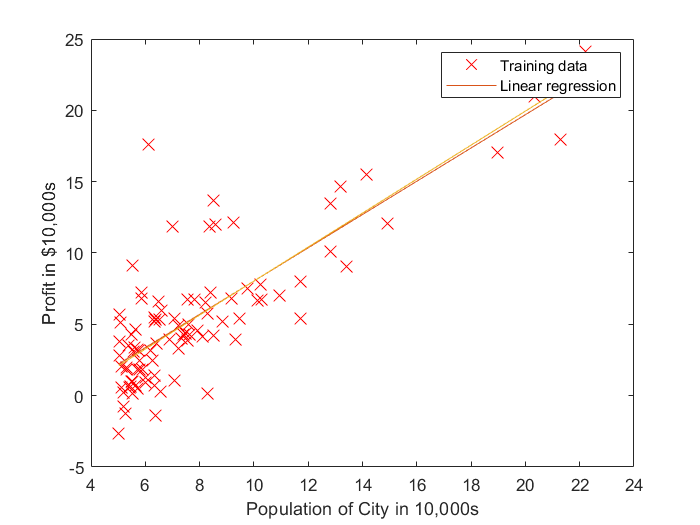


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 2913.325861


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 44607.163473


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

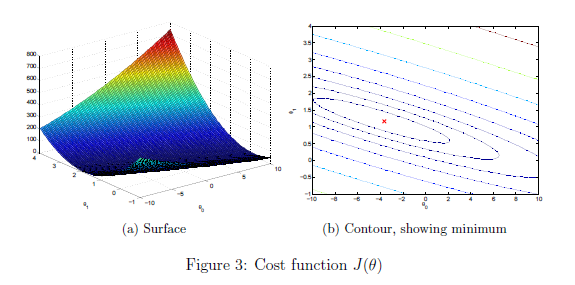

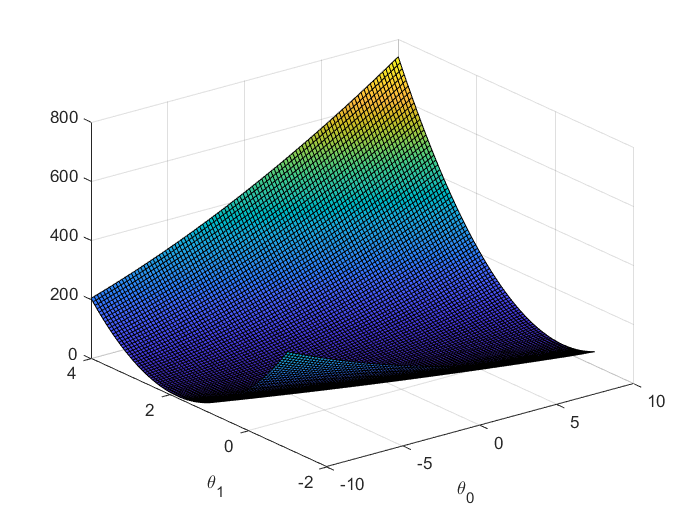

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

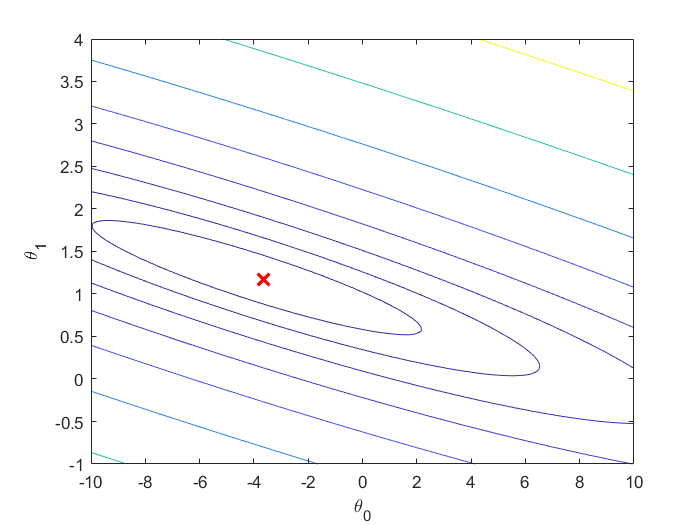


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

X_norm =     0.6544    0.7063
    0.4025    0.7063
    0.8024    0.7063
    0.3105    0.3908
    1.1023    1.0217
    0.5949    1.0217
    0.3695    0.7063
    0.3160    0.7063
    0.2925    0.7063
    0.3495    0.7063


**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X]

X =     1.0000    0.6544    0.7063
    1.0000    0.4025    0.7063
    1.0000    0.8024    0.7063
    1.0000    0.3105    0.3908
    1.0000    1.1023    1.0217
    1.0000    0.5949    1.0217
    1.0000    0.3695    0.7063
    1.0000    0.3160    0.7063
    1.0000    0.2925    0.7063
    1.0000    0.3495    0.7063


### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.3;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);


[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
145329.810544
222041.478289
80300.197637

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================





price = [[1,1650,3] * theta]; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $366754669.580872

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

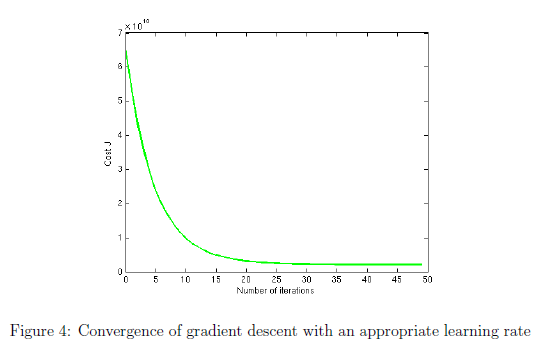

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

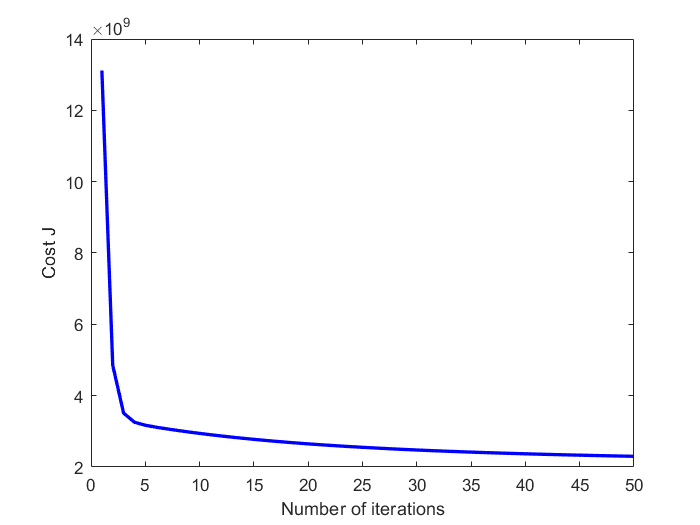

% Run gradient descent:
% Choose some alpha value
alpha = 0.3;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.3;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
145329.810544
222041.478289
80300.197637


% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = [[1,1650,3] * theta]; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $366754669.580872

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

Theta computed from the normal equations:
89597.909544
139.210674
-8738.019113

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = [[1,1650,3] * theta]; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $293081.464335

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

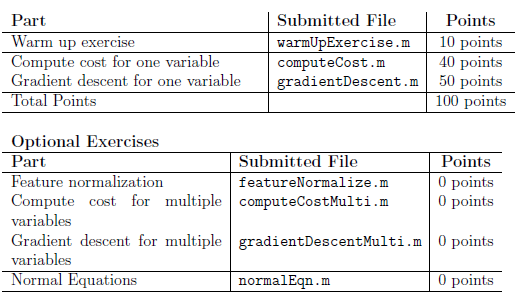

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.